clear;clc;
% --- paths (use your original logic) ---
if exist('I:\', 'dir')
    input_path = 'I:\My Drive\Data\New Data\EEG epoched\';
    base_output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
elseif exist('H:\', 'dir')
    input_path = 'H:\My Drive\Data\New Data\EEG epoched\';
    base_output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
elseif exist('G:\', 'dir')
    input_path = 'G:\My Drive\Data\New Data\EEG epoched\';
    base_output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end
output_path = fullfile(base_output_path, 'longitudinal_dPCA');

if ~exist(output_path, 'dir')
    mkdir(output_path);
    fprintf('Created new output directory: %s\n', output_path);
end

conditions = {'BLA','BLT','P1','P2','P3'}; %,'BLT','P1','P2','P3'
num_ch = 32;
expected_num_time = 1792; % sample count per epoch (your value)
fs = []; % will set from EEG.srate on first load
time_ms_eeg = [];

## Paert 1: Load and import file as EEGLAB matrix

data_all_conds = struct();

% Loop through the conditions
for c = 1:length(conditions)
    condition = conditions{c};
    in_dir = fullfile(input_path, condition);
    set_files = dir(fullfile(in_dir, '*.set'));
    names_sorted = sort(cellstr({set_files.name})');
    
    if isempty(names_sorted)
        fprintf('No .set files for %s — skipping\n', condition);
        continue;
    end
    
    % Load excel file paths for P2 and P3 ONCE per condition
    if strcmp(condition, 'P2')
        excel_file_path = fullfile(input_path, 'Indexes for P2.xlsx');
        epoch_trials_p2_500ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 500 ms tactile');
        epoch_trials_p2_2000ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 2000 ms tactil');
    elseif strcmp(condition, 'P3')
        excel_file_path = fullfile(input_path, 'Indexes for P3.xlsx');
        epoch_trials_p3_500ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 500 ms tactile');
        epoch_trials_p3_missing = readmatrix(excel_file_path, 'Sheet', 'Audio onset with missing tactil');
    end

    % --- NEW: Loop through ALL subjects for this condition ---
    for s = 1:length(names_sorted)
        file_to_load = names_sorted{s}; 
        fprintf('Loading Subj %d/%d (%s) for condition: %s\n', s, length(names_sorted), file_to_load, condition);
        
        EEG = pop_loadset('filename', file_to_load, 'filepath', in_dir);
        if isempty(fs), fs = EEG.srate; end
        
        if isempty(time_ms_eeg)
            time_ms_eeg = linspace(0, 3.5 , size(EEG.data, 2)); 
        end
        
        % Extract data and store in a cell array to avoid dimension mismatch
        if ismember(condition, {'BLA', 'BLT', 'P1'})
            epoch_trials = 1:2:EEG.trials;
            data_all_conds.(condition){s} = EEG.data(:, :, epoch_trials);
            
        elseif strcmp(condition, 'P2')
            epoch_trials_p2 = 1:2:EEG.trials;     
            data_all_conds.(condition){s} = EEG.data(:, :, epoch_trials_p2);
            data_all_conds.P2_500{s}      = EEG.data(:, :, epoch_trials_p2_500ms);
            data_all_conds.P2_2000{s}     = EEG.data(:, :, epoch_trials_p2_2000ms);
            
        elseif strcmp(condition, 'P3')
            epoch_trials_p3 = 1:2:EEG.trials;
            data_all_conds.(condition){s}   = EEG.data(:, :, epoch_trials_p3);
            data_all_conds.P3_500{s}        = EEG.data(:, :, epoch_trials_p3_500ms);
            data_all_conds.P3_missing{s}    = EEG.data(:, :, epoch_trials_p3_missing);
        end
    end
end

Loading Subj 1/14 (binepochs filtered ICArej BLAAvgBOS10.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej BLAAvgBOS11.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej BLAAvgBOS12.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej BLAAvgBOS13.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej BLAAvgBOS15.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej BLAAvgBOS16.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej BLAAvgBOS17.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej BLAAvgBOS2.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej BLAAvgBOS3.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej BLAAvgBOS5.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej BLAAvgBOS6.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej BLAAvgBOS7.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej BLAAvgBOS8.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej BLAAvgBOS9.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej BLTAvgBOS10.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej BLTAvgBOS11.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej BLTAvgBOS12.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej BLTAvgBOS13.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej BLTAvgBOS15.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej BLTAvgBOS16.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej BLTAvgBOS17.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej BLTAvgBOS2.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej BLTAvgBOS3.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej BLTAvgBOS5.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej BLTAvgBOS6.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej BLTAvgBOS7.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej BLTAvgBOS8.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej BLTAvgBOS9.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej P1AvgBOS10.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej P1AvgBOS11.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej P1AvgBOS12.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej P1AvgBOS13.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej P1AvgBOS15.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej P1AvgBOS16.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej P1AvgBOS17.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej P1AvgBOS2.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej P1AvgBOS3.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej P1AvgBOS5.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej P1AvgBOS6.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej P1AvgBOS7.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej P1AvgBOS8.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej P1AvgBOS9.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej P2AvgBOS10.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej P2AvgBOS11.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej P2AvgBOS12.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej P2AvgBOS13.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej P2AvgBOS15.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej P2AvgBOS16.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej P2AvgBOS17.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej P2AvgBOS2.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej P2AvgBOS3.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej P2AvgBOS5.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej P2AvgBOS6.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej P2AvgBOS7.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej P2AvgBOS8.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej P2AvgBOS9.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej P3AvgBOS10.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej P3AvgBOS11.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej P3AvgBOS12.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej P3AvgBOS13.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej P3AvgBOS15.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej P3AvgBOS16.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej P3AvgBOS17.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej P3AvgBOS2.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej P3AvgBOS3.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej P3AvgBOS5.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej P3AvgBOS6.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej P3AvgBOS7.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej P3AvgBOS8.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej P3AvgBOS9.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


## 1.2 Visualizing the conditions raw data

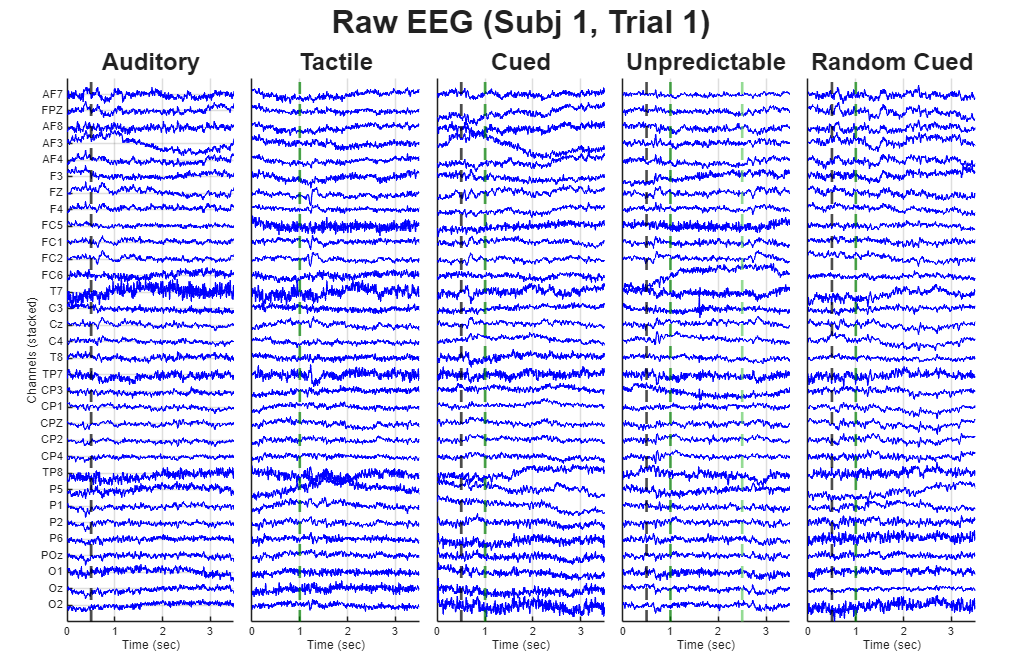

%% Visualizing Specific Trial for a Specific Subject
target_trial = 1; 
target_subject = 1; 

if exist('EEG', 'var') && isfield(EEG, 'chanlocs')
    display_channels_str = {EEG.chanlocs.labels};
else
    display_channels_str = cellstr(num2str((1:size(data_all_conds.BLT{1}, 1))')); 
end

num_channels_plot = length(display_channels_str);
plot_conds = fieldnames(data_all_conds);
num_conds = length(conditions); % Just plotting the base conditions for now

figure('Position',[50 50 2200 1400])
t = tiledlayout(1, num_conds, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, sprintf('Raw EEG (Subj %d, Trial %d)', target_subject, target_trial), 'FontSize', 24, 'FontWeight', 'bold');

offset = 30; 
tick_positions = (num_channels_plot - (1:num_channels_plot)) * offset;

for c = 1:num_conds
    cond_name = conditions{c};
    
    % Access the cell for the subject, then slice the 3rd dimension for the trial
    data_to_plot = data_all_conds.(cond_name){target_subject}(:, :, target_trial);
    
    nexttile;
    hold on
    for ch = 1:num_channels_plot
        plot(time_ms_eeg, data_to_plot(ch, :) + (num_channels_plot - ch)*offset, 'b', 'LineWidth', 1.0);
    end
    
    if strcmp(cond_name, 'BLT')
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
    elseif any(strcmp(cond_name, {'P1','P3'}))
        xline(0.5, 'k--', 'LineWidth', 2);
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
    elseif strcmp(cond_name, 'P2')
        xline(0.5, 'k--', 'LineWidth', 2);
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
        xline(2.5, '--', 'Color', [0.4 0.8 0.4], 'LineWidth', 2);
    else
        xline(0.5, 'k--', 'LineWidth', 2);
    end
    
    hold off
    xlim([min(time_ms_eeg), max(time_ms_eeg)]); 
    ylim([-offset, num_channels_plot*offset]);
    xlabel('Time (sec)'); 
    
    if c == 1
        ylabel('Channels (stacked)');
        yticks(flip(tick_positions));
        yticklabels(flip(string(display_channels_str)));
    else
        yticks([]);
    end
    if ismember(cond_name, 'BLA')
        plot_name = 'Auditory';
    elseif ismember(cond_name, 'BLT')
        plot_name = 'Tactile';    
    elseif ismember(cond_name, 'P1')
        plot_name = 'Cued';
    elseif ismember(cond_name, 'P2')
        plot_name = 'Unpredictable';
    elseif ismember(cond_name, 'P3')
        plot_name = 'Random Cued';
    end
    title(plot_name, 'FontSize', 18);
    grid on;
end

disp('Calculating averages across trials for each subject (Skipping Grand Average)...');

Calculating averages across trials for each subject (Skipping Grand Average)...



cond_names = fieldnames(data_all_conds);
data_subj_avg = struct();

for i = 1:length(cond_names)
    c_name = cond_names{i};
    num_subjects = length(data_all_conds.(c_name));
    
    % Dynamically find the time dimension length from the first available subject
    if num_subjects > 0 && ~isempty(data_all_conds.(c_name){1})
        num_timepoints = size(data_all_conds.(c_name){1}, 2);
    else
        num_timepoints = expected_num_time;
    end
    
    % 1. Preallocate [Channels x Time x Subjects] using NaN to avoid zero-skewing missing data
    subj_avg_matrix = nan(num_ch, num_timepoints, num_subjects);
    
    for s = 1:num_subjects
        % Make sure the subject actually has data for this condition
        if ~isempty(data_all_conds.(c_name){s})
            % Average across dim 3 (trials) for THIS subject
            subj_avg_matrix(:,:,s) = mean(data_all_conds.(c_name){s}, 3, 'omitnan');
        end
    end
    
    % Store the individual subject trial-averages
    data_subj_avg.(c_name) = subj_avg_matrix;
end

disp('Done! Data is stored in data_subj_avg with dimensions: [Channels x Time x Subjects].');

Done! Data is stored in data_subj_avg with dimensions: [Channels x Time x Subjects].


disp('Visualizing Trial Average with STD Shading for Subject 1...');

Visualizing Trial Average with STD Shading for Subject 1...


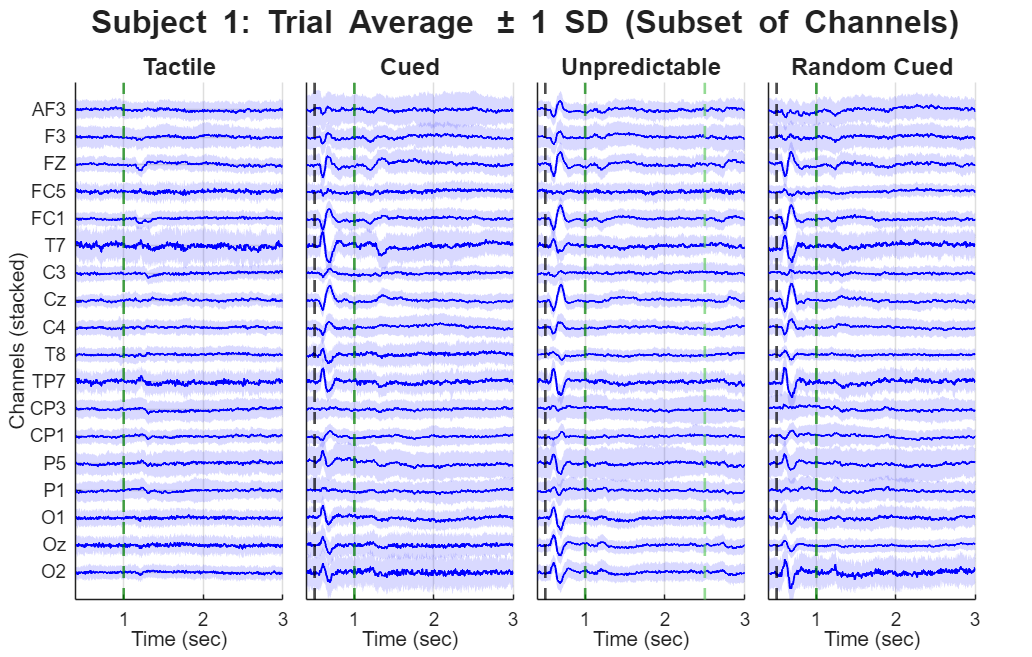


channels_to_plot = {'AF3', 'F3', 'FZ', 'FC5', 'FC1',  'T7', 'C3', 'Cz', 'C4', 'T8', 'TP7', 'CP3', 'CP1',  'P5', 'P1', 'O1', 'Oz', 'O2'};

% Safely define all_channels_str
if exist('EEG', 'var') && isfield(EEG, 'chanlocs')
    all_channels_str = {EEG.chanlocs.labels};
else
    all_channels_str = cellstr(num2str((1:num_ch)'));
end

[~, chan_idx] = ismember(channels_to_plot, all_channels_str);
valid_mask = chan_idx > 0;
chan_idx = chan_idx(valid_mask);
display_channels_str = channels_to_plot(valid_mask);

num_channels_plot = length(display_channels_str);
base_conds_to_plot = {'BLT', 'P1', 'P2', 'P3'}; 
num_conds = length(base_conds_to_plot);

fig1 = figure('Position',[50 50 2200 1400]);
t = tiledlayout(1, num_conds, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, 'Subject 1: Trial Average \pm 1 SD (Subset of Channels)', 'FontSize', 24, 'FontWeight', 'bold');

offset = 15; 
tick_positions = (num_channels_plot - (1:num_channels_plot)) * offset;
time_fill = [time_ms_eeg, fliplr(time_ms_eeg)]; % X-axis for shading

for c = 1:num_conds
    cond_name = base_conds_to_plot{c};
    
    % Extract raw trial data for Subject 1 [Channels x Time x Trials]
    subj1_data = data_all_conds.(cond_name){1}; 
    
    nexttile;
    hold on
    
    for ch = 1:num_channels_plot
        actual_ch = chan_idx(ch);
        y_shift = (num_channels_plot - ch) * offset;
        
        % Calculate Mean and STD across the Trial dimension (dim 3)
        mu = squeeze(mean(subj1_data(actual_ch, :, :), 3, 'omitnan')) + y_shift;
        sigma = squeeze(std(subj1_data(actual_ch, :, :), 0, 3, 'omitnan'));
        
        % Create boundaries for the shaded standard deviation
        y_bound = [mu + sigma, fliplr(mu - sigma)];
        
        % Plot Shaded STD Area first (so it sits behind the line)
        fill(time_fill, y_bound, 'b', 'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
        
        % Plot Mean Line
        plot(time_ms_eeg, mu, 'b', 'LineWidth', 1.5);
    end
    
    % Add Vertical Event Lines
    if strcmp(cond_name, 'BLT')
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
    elseif any(strcmp(cond_name, {'P1','P3'}))
        xline(0.5, 'k--', 'LineWidth', 2);
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
    elseif strcmp(cond_name, 'P2')
        xline(0.5, 'k--', 'LineWidth', 2);
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
        xline(2.5, '--', 'Color', [0.4 0.8 0.4], 'LineWidth', 2);
    else
        xline(0.5, 'k--', 'LineWidth', 2);
    end
    
    hold off
    xlim([0.4, 3]); 
    ylim([-offset, num_channels_plot*offset]);
    xlabel('Time (sec)'); 
    
    if c == 1
        ylabel('Channels (stacked)');
        yticks(flip(tick_positions));
        yticklabels(flip(string(display_channels_str)));
    else
        yticks([]); 
    end
    
    set(gca,'FontSize',14);
    
    % Safe title assignment
    if strcmp(cond_name, 'BLT')
        plot_name = 'Tactile';    
    elseif strcmp(cond_name, 'P1')
        plot_name = 'Cued';
    elseif strcmp(cond_name, 'P2')
        plot_name = 'Unpredictable';
    elseif strcmp(cond_name, 'P3')
        plot_name = 'Random Cued';
    else
        plot_name = cond_name;
    end
    title(plot_name, 'FontSize', 18);
    grid on;
end

## Part 2: Moving Window Functional Connectivity


disp('Step 1: Defining Window Parameters...');

Step 1: Defining Window Parameters...



% Ensure fs and time arrays are set (fallback to standard EEG values if empty)
if isempty(fs)
    warning('Sampling rate (fs) not found. Defaulting to 500 Hz.');
    fs = EEG.srate; 
end

% 1. Define Window Parameters
window_size_ms = 100;
step_size_ms = 50;

% Convert ms to samples based on your sampling rate
win_samples = round((window_size_ms / 1000) * fs);
step_samples = round((step_size_ms / 1000) * fs);

cond_names = fieldnames(data_subj_avg);
num_timepoints = size(data_subj_avg.(cond_names{1}), 2);
num_subjects = size(data_subj_avg.(cond_names{1}), 3);

% Create vector of starting indices for the sliding windows
start_idx = 1 : step_samples : (num_timepoints - win_samples + 1);
num_windows = length(start_idx);

% Calculate the center of each window in milliseconds (for plotting the X-axis)
window_centers_ms = zeros(1, num_windows);
for w = 1:num_windows
    % Averages the time_ms_eeg values within the current window chunk
    window_centers_ms(w) = mean(time_ms_eeg(start_idx(w) : start_idx(w) + win_samples - 1));
end


## Step 1.3: 

function [num_factors, map_values] = velicer_map(data, quiet)
% VELICER_MAP Determines the number of factors to retain using Velicer's MAP test.
%
% Inputs:
%   data  - An (n x p) matrix of raw data (n observations, p variables).
%   quiet - Boolean flag. Set to true to suppress plotting (default: false).

    if nargin < 2
        quiet = false; % Default is to show the plot
    end

    % 1. Compute the correlation matrix
    R = corrcoef(data);
    p = size(R, 1);
    
    % 2. Perform Eigenvalue Decomposition
    [eigvec, eigval_mat] = eig(R);
    eigval = diag(eigval_mat);
    
    % Sort eigenvalues and eigenvectors in descending order
    [eigval, idx] = sort(eigval, 'descend');
    eigvec = eigvec(:, idx);
    
    % Initialize array to store the MAP values
    map_values = zeros(1, p);
    
    % 3. Step 0: Calculate average squared correlation (no factors partialled out)
    R_off_diag = R - eye(p);
    map_values(1) = sum(R_off_diag(:).^2) / (p * (p - 1));
    
    % 4. Loop to partial out 1 to p-1 components
    for m = 1:(p-1)
        A = eigvec(:, 1:m) * diag(sqrt(eigval(1:m)));
        part_cov = R - (A * A');
        d = diag(part_cov);
        inv_sqrt_d = diag(1 ./ sqrt(d));
        R_partial = inv_sqrt_d * part_cov * inv_sqrt_d;
        R_partial_off = R_partial - eye(p);
        map_values(m+1) = sum(R_partial_off(:).^2) / (p * (p - 1));
    end
    
    % 5. Find the minimum MAP value
    [min_val, min_idx] = min(map_values);
    num_factors = min_idx - 1;
    
    % 6. Optional: Plot the results to visualize the minimum
    if ~quiet
        figure('Position',[50 50 800 500]);
        plot(0:(p-1), map_values, '-o', 'LineWidth', 2, 'MarkerFaceColor', 'b');
        hold on;
        plot(num_factors, map_values(min_idx), 'rp', 'MarkerSize', 12, 'MarkerFaceColor', 'r'); 
        coordinate_text = sprintf('  Min: (%d, %.4f)', num_factors, min_val);
        text(num_factors, 0.2, coordinate_text, 'VerticalAlignment', 'top', ...
            'HorizontalAlignment', 'center', 'FontSize', 26, 'FontWeight', 'bold', 'Color', 'r');
        xlabel('Number of Factors Retained');
        ylabel('Avg. Sqrd. Partial Corr.');
        title('Velicer''s MAP Test');
        legend('MAP Values', 'Minimum (Optimal Factors)');
        set(gca,'FontSize',24);
        grid on; hold off;
    end
end


## Step 2 & 3: Pairwise dPCA and Connectivity Heatmaps

%% Step 2 & 3: Pairwise dPCA and Connectivity Heatmaps (Custom Windows)
disp('Running Pairwise dPCA and Generating Correlation Heatmaps...');

Running Pairwise dPCA and Generating Correlation Heatmaps...


Pair Auditory vs Cued (Window 0.50s to 0.85s): MAP selected k=5 shared components


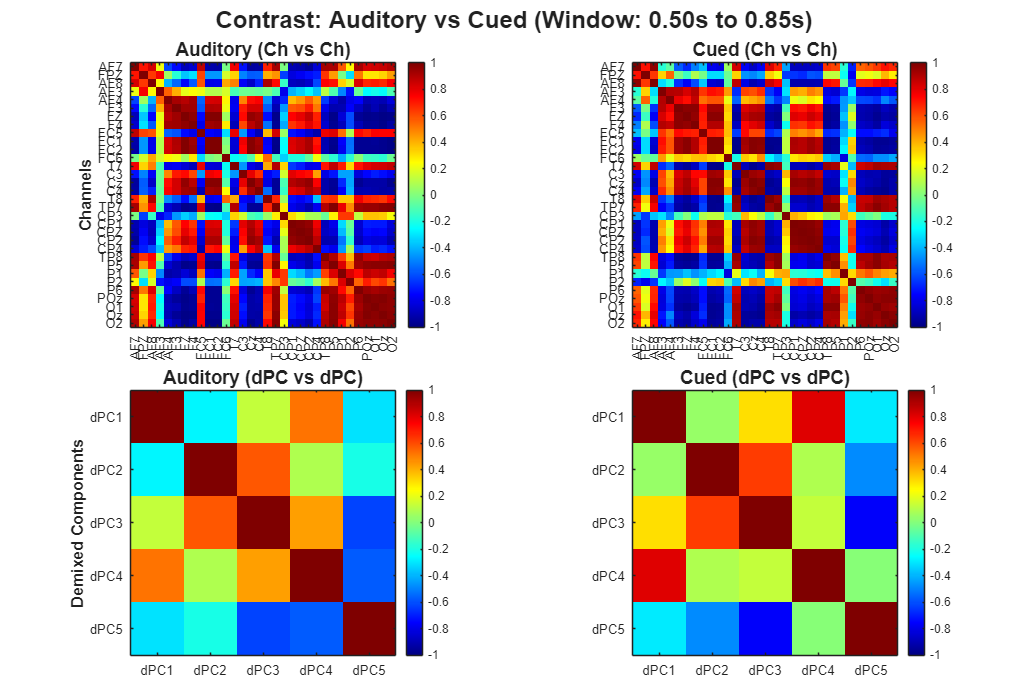

Pair Tactile vs Cued (Window 1.00s to 1.35s): MAP selected k=10 shared components


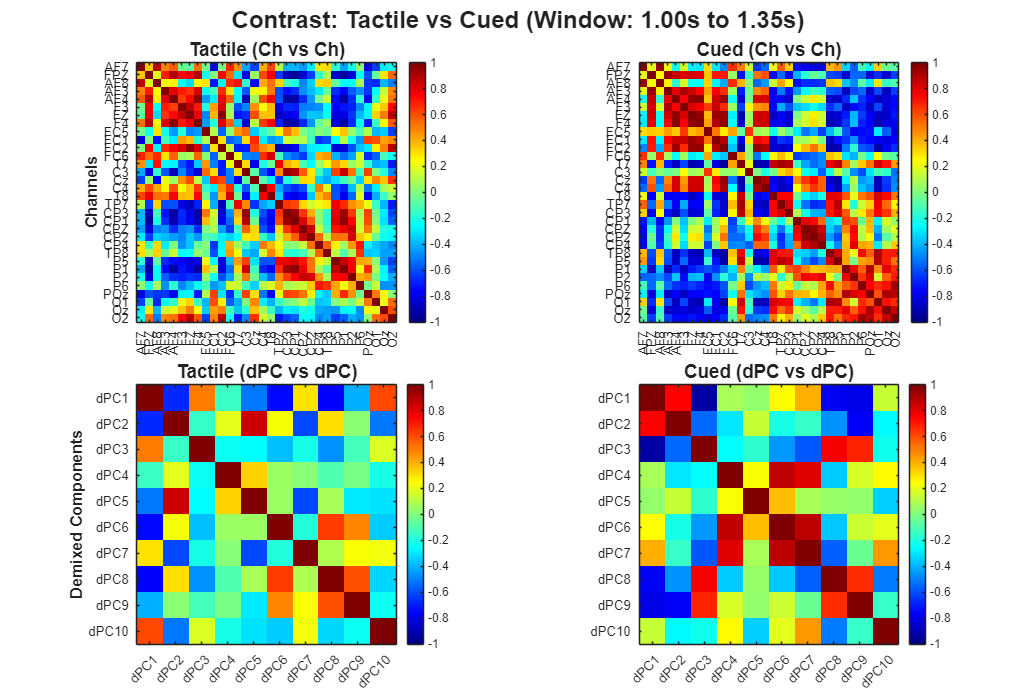

Pair Cued vs Unpred. 500 (Window 1.00s to 1.35s): MAP selected k=8 shared components


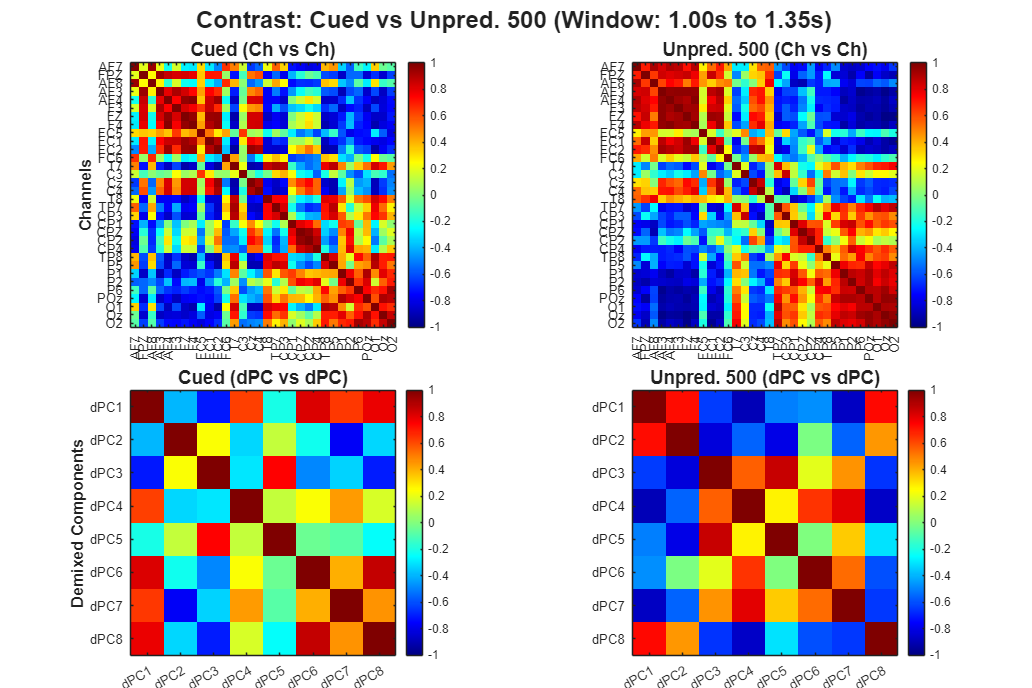

Pair Cued vs Unpred. 2000 (Window 2.50s to 2.85s): MAP selected k=7 shared components


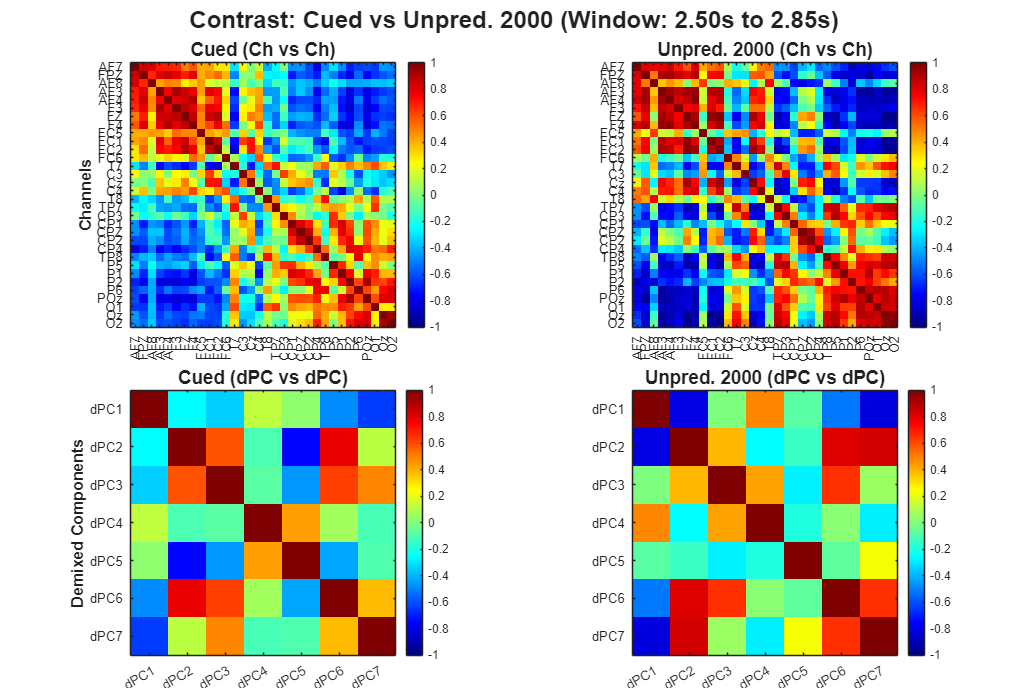

Pair Cued vs Rand. Cued 500 (Window 1.00s to 1.35s): MAP selected k=8 shared components


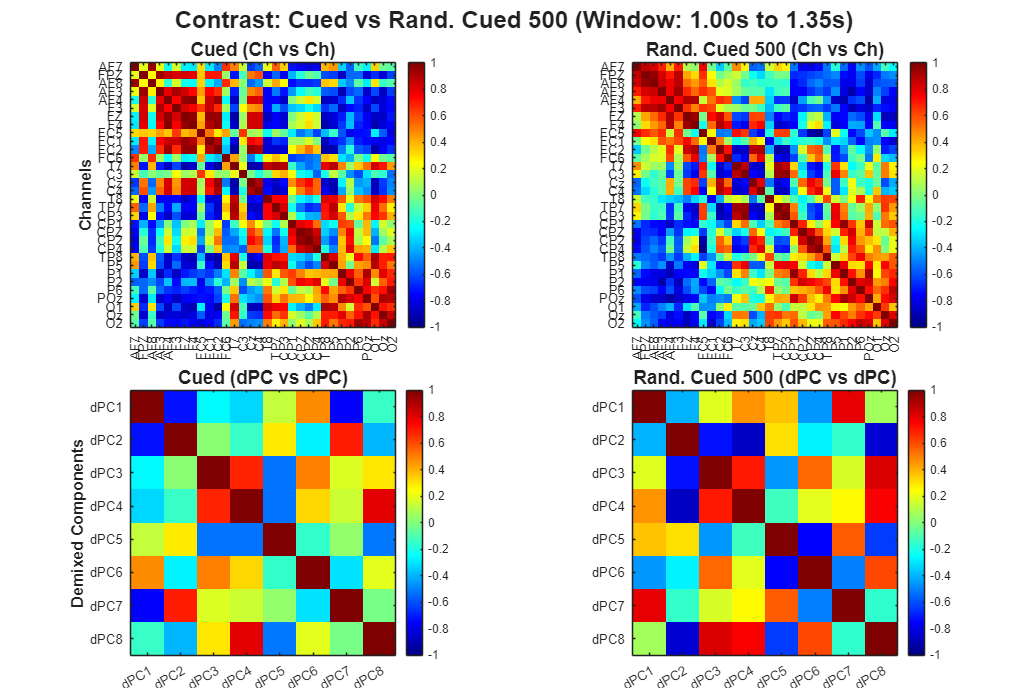

Pair Cued vs Rand. Cued missing (Window 1.00s to 1.35s): MAP selected k=8 shared components


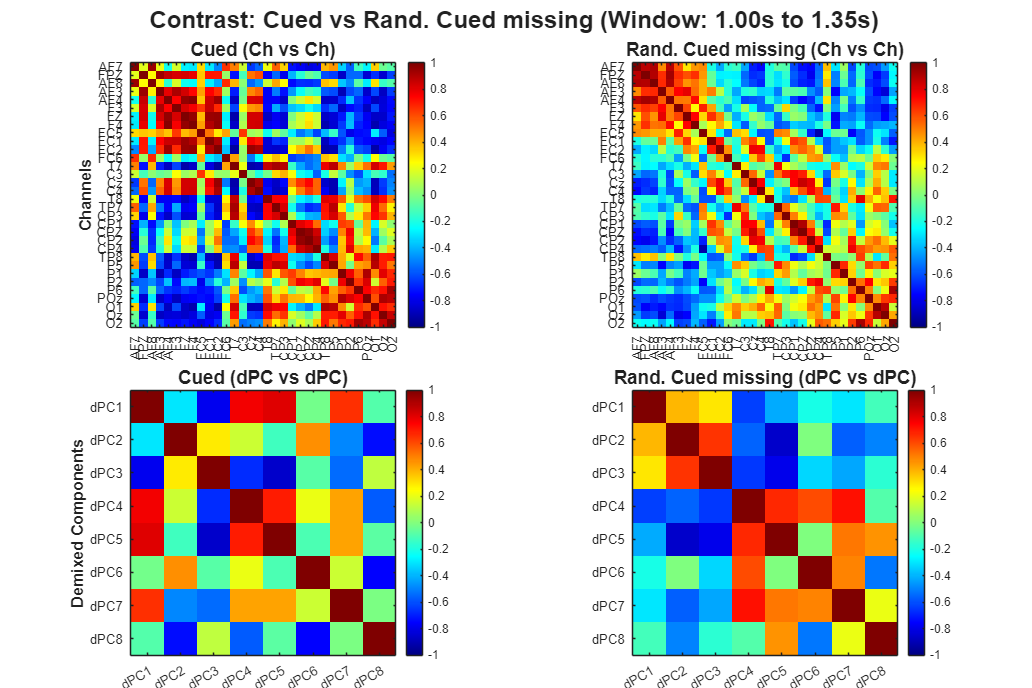


% Inline helper function: cleans condition names for plotting
get_clean_name = @(c) strrep(strrep(strrep(strrep(strrep(strrep(c, ...
    'BLA', 'Auditory'), 'BLT', 'Tactile'), 'P1', 'Cued'), ...
    'P2', 'Unpred.'), 'P3', 'Rand. Cued'), '_', ' ');

% Define your Condition Pairs along with their specific time windows [start_sec, end_sec]
pairs = {
    {'BLA', 'P1', [0.5, 0.85]},
    {'BLT', 'P1', [1.0, 1.35]},
    {'P1', 'P2_500', [1.0, 1.35]},
    {'P1', 'P2_2000', [2.5, 2.85]},
    {'P1', 'P3_500', [1.0, 1.35]},
    {'P1', 'P3_missing', [1.0, 1.35]}
};

target_subj = 1; % Analyzing Subject 1

% Check if channel labels exist
if ~exist('all_channels_str', 'var')
    all_channels_str = arrayfun(@(x) sprintf('Ch%d', x), 1:num_ch, 'UniformOutput', false);
end

for p = 1:length(pairs)
    condA = pairs{p}{1};
    condB = pairs{p}{2};
    t_win = pairs{p}{3}; % Extract the specific time window for this pair
    
    % Clean the names for all plotting and console output
    cleanA = get_clean_name(condA);
    cleanB = get_clean_name(condB);
    
    % Find precise indices for the specified time window dynamically for this pair
    idx_start = find(time_ms_eeg >= t_win(1), 1, 'first');
    idx_end = find(time_ms_eeg <= t_win(2), 1, 'last');

    % Ensure both conditions actually exist in the dataset for Subject 1
    if ~isfield(data_subj_avg, condA) || ~isfield(data_subj_avg, condB)
        warning('Skipping pair %s vs %s (Missing data)', cleanA, cleanB);
        continue;
    end
    
    % Extract Full Trial-Averaged Data for Subject 1 [Channels x Time]
    dataA = data_subj_avg.(condA)(:, :, target_subj);
    dataB = data_subj_avg.(condB)(:, :, target_subj);
    
    if all(isnan(dataA(:))) || all(isnan(dataB(:)))
        continue;
    end
    
    %% --- DIMENSIONALITY REDUCTION (SHARED MANIFOLD) ---
    
    % 1. Concatenate conditions horizontally [Channels x (Time*2)]
    data_combined = [dataA, dataB];
    data_combined_centered = data_combined - mean(data_combined, 2);
    
    % 2. Find optimal k for the shared space using Velicer's MAP
    [k_opt, ~] = velicer_map(data_combined_centered', true);
    if k_opt < 2, k_opt = 2; end % Safe fallback
    
    fprintf('Pair %s vs %s (Window %.2fs to %.2fs): MAP selected k=%d shared components\n', ...
        cleanA, cleanB, t_win(1), t_win(2), k_opt);
    
    % 3. Extract Unmixing Matrix (W)
    try
        % dPCA expects [Channels x Time x Conditions]
        X_dpca = cat(3, dataA, dataB); 
        X_dpca_centered = bsxfun(@minus, X_dpca, mean(X_dpca(:,:), 2));
        
        % Minimal dPCA call (assuming dpca toolbox is in path)
        [W_dpca, ~, ~] = dpca(X_dpca_centered, k_opt); 
        
        % Transpose dPCA's W from [Channels x k] to [k x Channels]
        W = W_dpca';
        
    catch ME
        % FALLBACK: Shared PCA 
        [~, ~, V] = svd(data_combined_centered', 'econ');
        W = V(:, 1:k_opt)'; % Unmixing matrix [k_opt x Channels]
    end
    
    % 4. Project Cond A and Cond B into the EXACT SAME latent space
    compA = W * (dataA - mean(dataA, 2)); 
    compB = W * (dataB - mean(dataB, 2));
    
    %% --- SLIDING WINDOW CORRELATION (EXTRACTION) ---
    
    % Extract the specific time window chunks for this pair
    ch_chunkA = dataA(:, idx_start:idx_end);
    ch_chunkB = dataB(:, idx_start:idx_end);
    
    pc_chunkA = compA(:, idx_start:idx_end);
    pc_chunkB = compB(:, idx_start:idx_end);
    
    % Correlate (Transpose so variables are columns)
    corr_ch_A = corrcoef(ch_chunkA');
    corr_ch_B = corrcoef(ch_chunkB');
    
    corr_pc_A = corrcoef(pc_chunkA');
    corr_pc_B = corrcoef(pc_chunkB');
    
    %% --- PLOTTING CONTRAST HEATMAPS ---
    
    fig = figure('Position', [100, 100, 1200, 800], 'Name', sprintf('%s vs %s', cleanA, cleanB));
    tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
    
    pc_labels = arrayfun(@(x) sprintf('dPC%d', x), 1:k_opt, 'UniformOutput', false);
    
    % --- Row 1: Channel Connectivity ---
    % Cond A (Channels)
    nexttile; imagesc(corr_ch_A); colormap('jet'); colorbar; clim([-1 1]);
    title(sprintf('%s (Ch vs Ch)', cleanA), 'FontSize', 14);
    axis square; ylabel('Channels', 'FontSize', 12, 'FontWeight', 'bold');
    yticks(1:num_ch); yticklabels(all_channels_str); xticks(1:num_ch); xticklabels(all_channels_str); xtickangle(90);
    
    % Cond B (Channels)
    nexttile; imagesc(corr_ch_B); colormap('jet'); colorbar; clim([-1 1]);
    title(sprintf('%s (Ch vs Ch)', cleanB), 'FontSize', 14);
    axis square;
    yticks(1:num_ch); yticklabels(all_channels_str); xticks(1:num_ch); xticklabels(all_channels_str); xtickangle(90);
    
    % --- Row 2: dPC Connectivity ---
    % Cond A (dPCs)
    nexttile; imagesc(corr_pc_A); colormap('jet'); colorbar; clim([-1 1]);
    title(sprintf('%s (dPC vs dPC)', cleanA), 'FontSize', 14);
    axis square; ylabel('Demixed Components', 'FontSize', 12, 'FontWeight', 'bold');
    yticks(1:k_opt); yticklabels(pc_labels); xticks(1:k_opt); xticklabels(pc_labels);
    
    % Cond B (dPCs)
    nexttile; imagesc(corr_pc_B); colormap('jet'); colorbar; clim([-1 1]);
    title(sprintf('%s (dPC vs dPC)', cleanB), 'FontSize', 14);
    axis square;
    yticks(1:k_opt); yticklabels(pc_labels); xticks(1:k_opt); xticklabels(pc_labels);
    
    % Master Title
    sgtitle(sprintf('Contrast: %s vs %s (Window: %.2fs to %.2fs)', ...
        cleanA, cleanB, t_win(1), t_win(2)), ...
        'FontSize', 18, 'FontWeight', 'bold');
end


disp('Pairwise Heatmaps generated successfully.');

Pairwise Heatmaps generated successfully.


## Steps 4, 5, & 6: Connectivity Metric Extraction and Grouped Bar Charts

%% Steps 4, 5, & 6: Connectivity Metric Extraction and Grouped Bar Charts
disp('Extracting Global Mean Connectivity and Plotting per Group...');

Extracting Global Mean Connectivity and Plotting per Group...


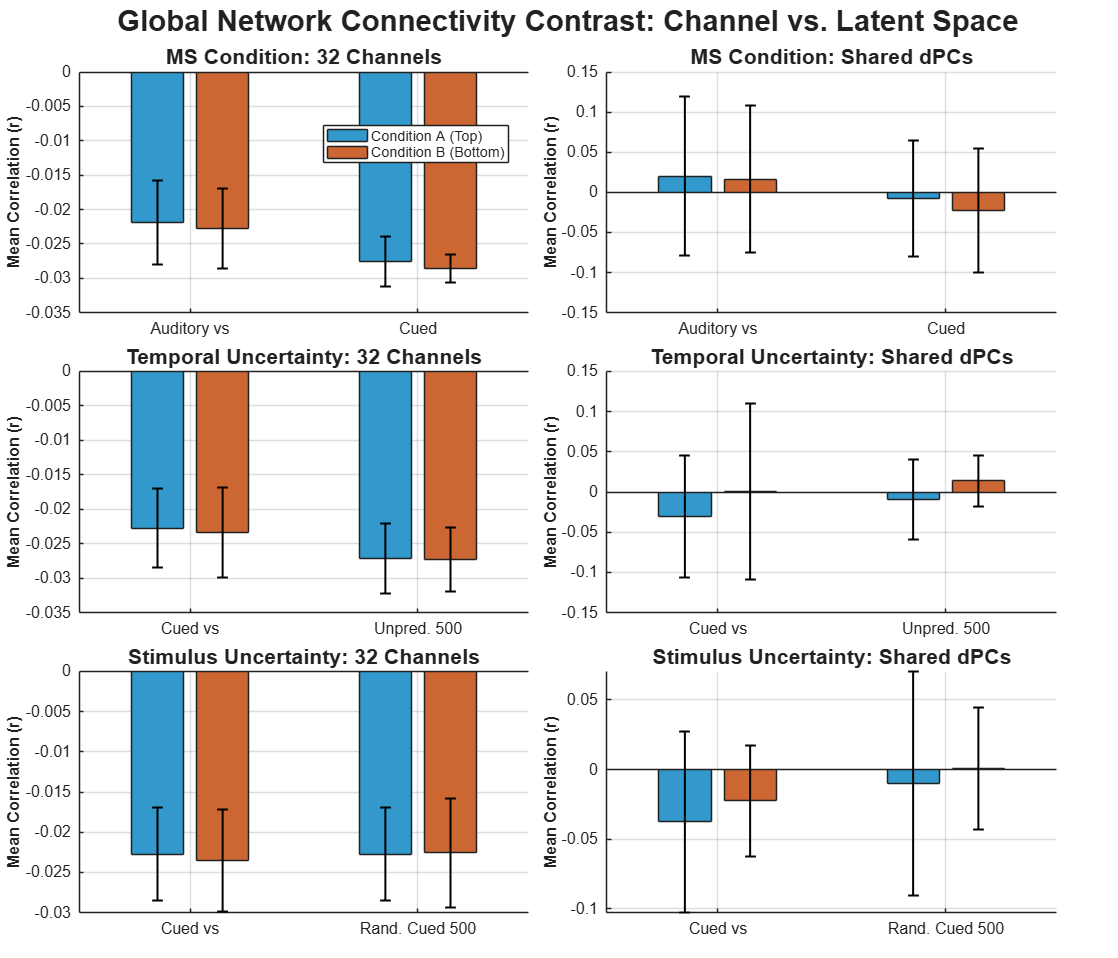


% Inline helper function: gets mean of the upper triangle of a correlation matrix
get_upper_tri_mean = @(mat) mean(mat(triu(true(size(mat)), 1)), 'omitnan');

% Inline helper function: cleans condition names for plotting
get_clean_name = @(c) strrep(strrep(strrep(strrep(strrep(strrep(c, ...
    'BLA', 'Auditory'), 'BLT', 'Tactile'), 'P1', 'Cued'), ...
    'P2', 'Unpred.'), 'P3', 'Rand. Cued'), '_', ' ');

% Define the 3 Experimental Groups with their specific pairs and windows
stats_groups = struct();

% Group 1: MS Condition
stats_groups(1).name = 'MS Condition';
stats_groups(1).pairs = {
    {'BLA', 'P1', [0.5, 0.85]},
    {'BLT', 'P1', [1.0, 1.35]}
};

% Group 2: Temporal Uncertainty
stats_groups(2).name = 'Temporal Uncertainty';
stats_groups(2).pairs = {
    {'P1', 'P2_500', [0.5, 0.85]},
    {'P1', 'P2_2000', [0.5, 2.85]}
};

% Group 3: Stimulus Uncertainty
stats_groups(3).name = 'Stimulus Uncertainty';
stats_groups(3).pairs = {
    {'P1', 'P3_500', [0.5, 0.85]},
    {'P1', 'P3_missing', [0.5, 0.85]}
};

% Create a large figure for all 3 groups (3 rows x 2 columns)
fig_conn = figure('Position', [50 50 1400 1200]);
t = tiledlayout(length(stats_groups), 2, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, 'Global Network Connectivity Contrast: Channel vs. Latent Space', 'FontSize', 22, 'FontWeight', 'bold');

for g = 1:length(stats_groups)
    num_pairs = length(stats_groups(g).pairs);
    
    % Preallocate arrays for this group [Pairs x Subjects]
    mean_ch_A = nan(num_pairs, num_subjects);
    mean_ch_B = nan(num_pairs, num_subjects);
    mean_pc_A = nan(num_pairs, num_subjects);
    mean_pc_B = nan(num_pairs, num_subjects);
    
    pair_labels = cell(1, num_pairs);
    
    for p = 1:num_pairs
        condA = stats_groups(g).pairs{p}{1};
        condB = stats_groups(g).pairs{p}{2};
        t_win = stats_groups(g).pairs{p}{3}; 
        
        % Clean the names and format the label for the X-axis
        cleanA = get_clean_name(condA);
        cleanB = get_clean_name(condB);
        pair_labels{p} = sprintf('%s vs\n%s', cleanA, cleanB);
        
        % Find exact indices for this pair's specific time window
        idx_start = find(time_ms_eeg >= t_win(1), 1, 'first');
        idx_end = find(time_ms_eeg <= t_win(2), 1, 'last');
        
        % Process ALL subjects to build statistical variance
        for s = 1:num_subjects
            % Safeguard against missing subjects/conditions
            if ~isfield(data_subj_avg, condA) || ~isfield(data_subj_avg, condB)
                continue; 
            end
            
            dataA = data_subj_avg.(condA)(:, :, s);
            dataB = data_subj_avg.(condB)(:, :, s);
            
            if all(isnan(dataA(:))) || all(isnan(dataB(:))), continue; end
            
            % 1. Create Shared Manifold
            data_combined = [dataA, dataB];
            data_combined_centered = data_combined - mean(data_combined, 2);
            
            % 2. Velicer's MAP to find shared k
            [k_opt, ~] = velicer_map(data_combined_centered', true);
            if k_opt < 2, k_opt = 2; end 
            
            % 3. Extract Unmixing Matrix (Shared PCA)
            [~, ~, V] = svd(data_combined_centered', 'econ');
            W = V(:, 1:k_opt)'; 
            
            % 4. Project both conditions into the shared space
            compA = W * (dataA - mean(dataA, 2)); 
            compB = W * (dataB - mean(dataB, 2));
            
            % 5. Correlate specific time windows (Transpose to match variables)
            corr_ch_A = corrcoef(dataA(:, idx_start:idx_end)');
            corr_ch_B = corrcoef(dataB(:, idx_start:idx_end)');
            corr_pc_A = corrcoef(compA(:, idx_start:idx_end)');
            corr_pc_B = corrcoef(compB(:, idx_start:idx_end)');
            
            % 6. Extract the Global Mean (Upper Triangle)
            mean_ch_A(p, s) = get_upper_tri_mean(corr_ch_A);
            mean_ch_B(p, s) = get_upper_tri_mean(corr_ch_B);
            mean_pc_A(p, s) = get_upper_tri_mean(corr_pc_A);
            mean_pc_B(p, s) = get_upper_tri_mean(corr_pc_B);
        end
    end
    
    % Calculate Grand Means and Standard Deviations across subjects for this group
    mu_ch  = [mean(mean_ch_A, 2, 'omitnan'), mean(mean_ch_B, 2, 'omitnan')];
    std_ch = [std(mean_ch_A, 0, 2, 'omitnan'), std(mean_ch_B, 0, 2, 'omitnan')];

    mu_pc  = [mean(mean_pc_A, 2, 'omitnan'), mean(mean_pc_B, 2, 'omitnan')];
    std_pc = [std(mean_pc_A, 0, 2, 'omitnan'), std(mean_pc_B, 0, 2, 'omitnan')];
    
    %% Plotting Row for this Group
    
    % --- Left Column: Channel-Level Contrast ---
    nexttile; hold on;
    b_ch = bar(mu_ch, 'grouped');
    b_ch(1).FaceColor = [0.2 0.6 0.8]; % Blueish
    b_ch(2).FaceColor = [0.8 0.4 0.2]; % Orangeish

    % Add Error Bars
    for i = 1:2
        x_pos = b_ch(i).XEndPoints;
        errorbar(x_pos, mu_ch(:,i), std_ch(:,i), 'k', 'linestyle', 'none', 'LineWidth', 1.5, 'CapSize', 8);
    end

    set(gca, 'xtick', 1:num_pairs, 'xticklabel', pair_labels, 'FontSize', 12);
    ylabel('Mean Correlation (r)', 'FontSize', 12, 'FontWeight', 'bold');
    title(sprintf('%s: 32 Channels', stats_groups(g).name), 'FontSize', 16);
    if g == 1, legend({'Condition A (Top)', 'Condition B (Bottom)'}, 'Location', 'best'); end
    grid on; hold off;

    % --- Right Column: Latent Component Contrast ---
    nexttile; hold on;
    b_pc = bar(mu_pc, 'grouped');
    b_pc(1).FaceColor = [0.2 0.6 0.8]; 
    b_pc(2).FaceColor = [0.8 0.4 0.2]; 

    % Add Error Bars
    for i = 1:2
        x_pos = b_pc(i).XEndPoints;
        errorbar(x_pos, mu_pc(:,i), std_pc(:,i), 'k', 'linestyle', 'none', 'LineWidth', 1.5, 'CapSize', 8);
    end

    set(gca, 'xtick', 1:num_pairs, 'xticklabel', pair_labels, 'FontSize', 12);
    ylabel('Mean Correlation (r)', 'FontSize', 12, 'FontWeight', 'bold');
    title(sprintf('%s: Shared dPCs', stats_groups(g).name), 'FontSize', 16);
    grid on; hold off;
end

% Save output
saveas(fig_conn, fullfile(output_path, 'Grouped_Connectivity_Statistical_Contrast.png'));

disp('Analysis Complete! Grouped Statistical Contrast Bar Charts saved to output directory.');

Analysis Complete! Grouped Statistical Contrast Bar Charts saved to output directory.


## Pairwise dPCA & Moving Window Heatmaps (Specific Sub-Windows)

disp('Running Pairwise dPCA and Specific Window Heatmaps...');

Running Pairwise dPCA and Specific Window Heatmaps...


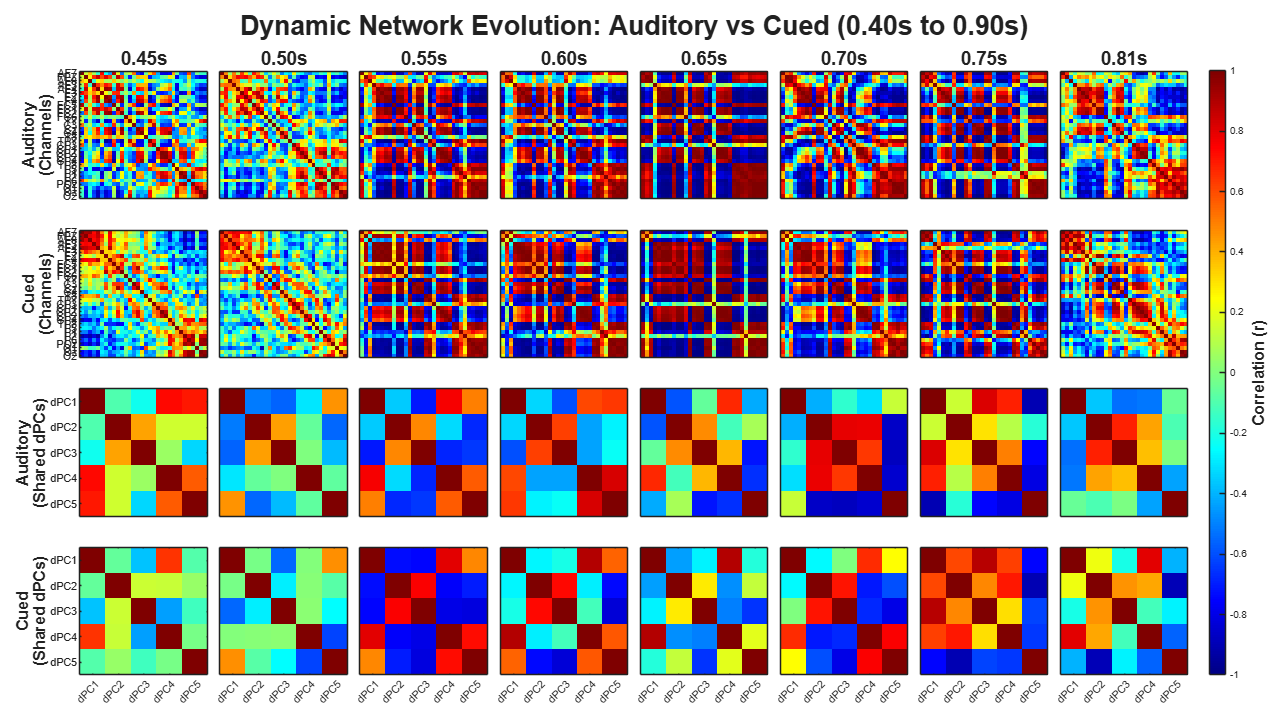

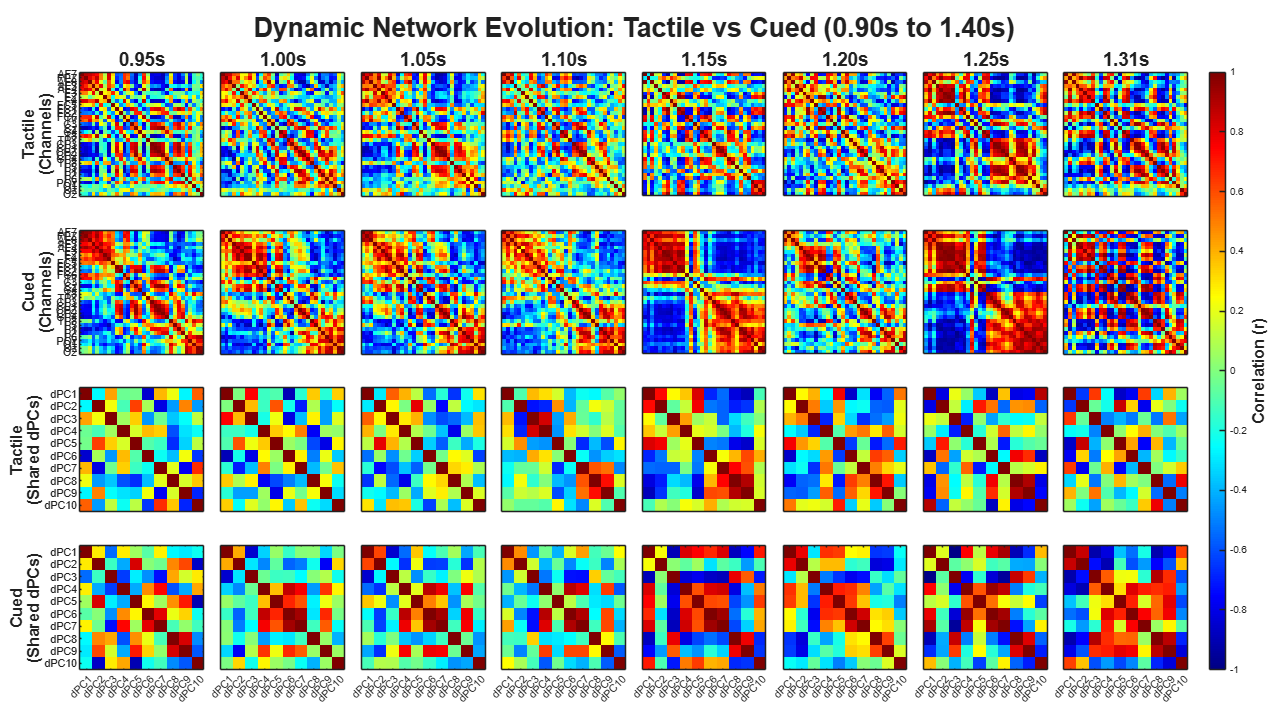

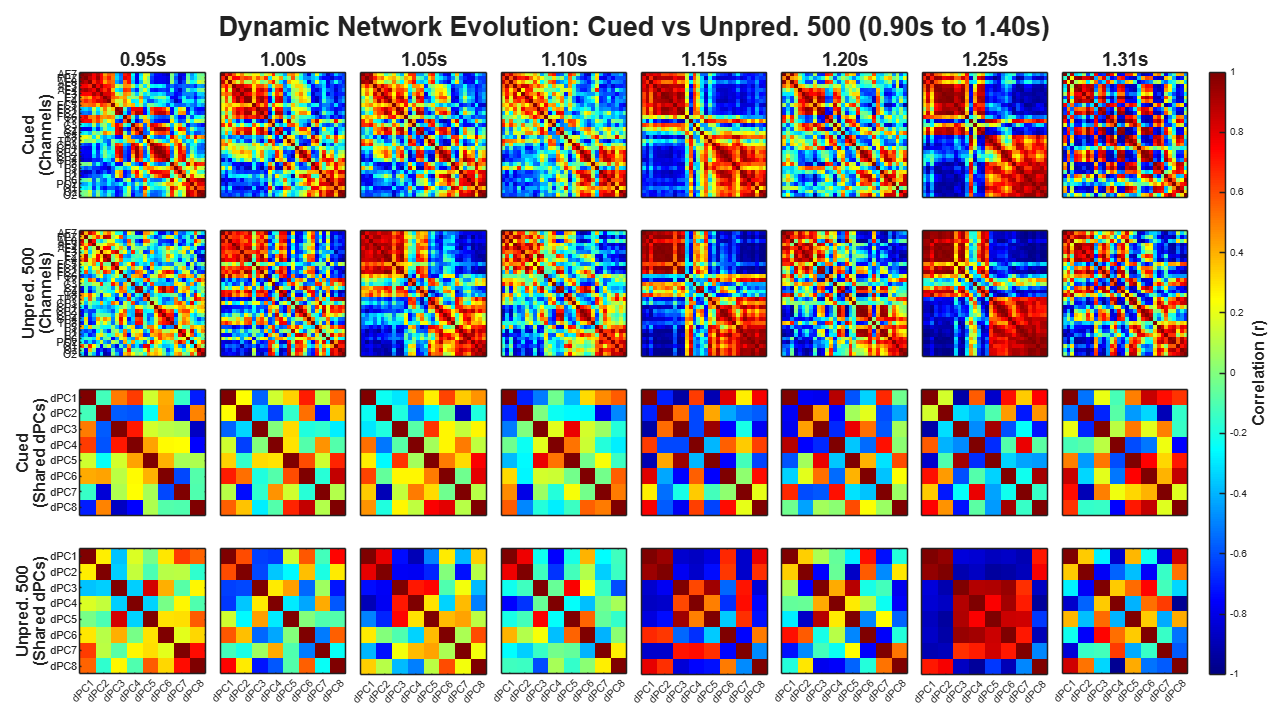

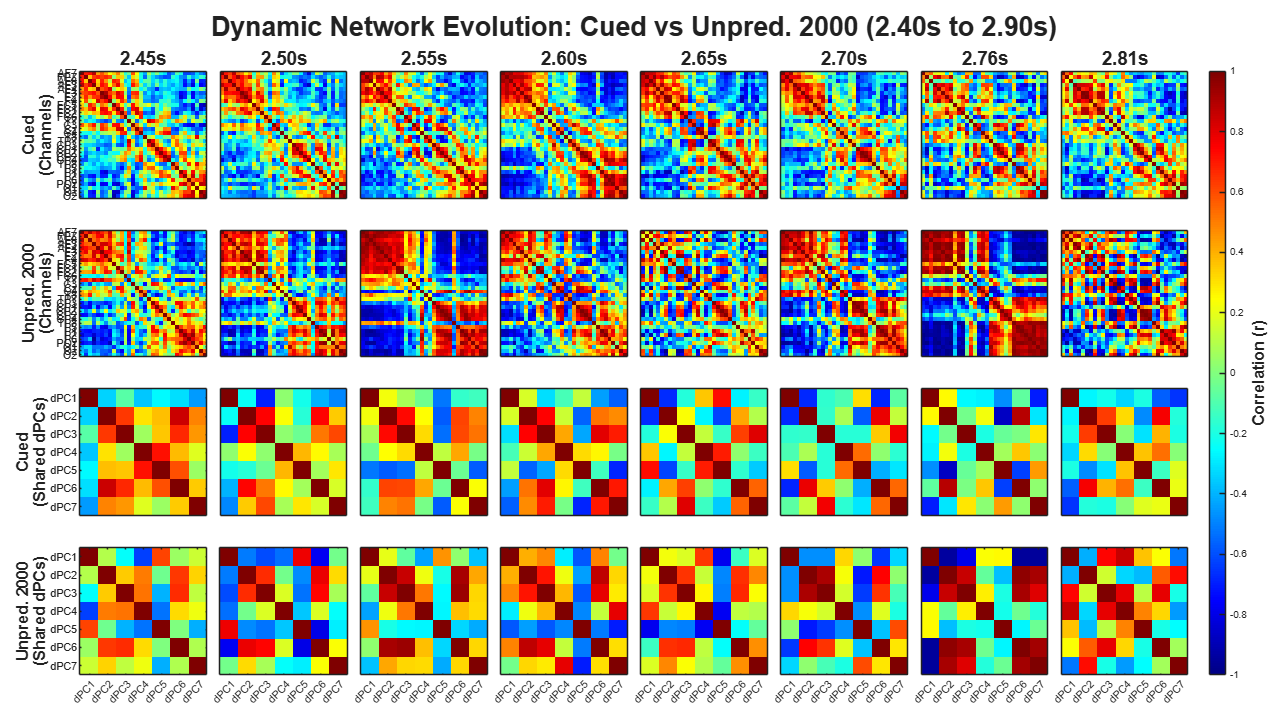

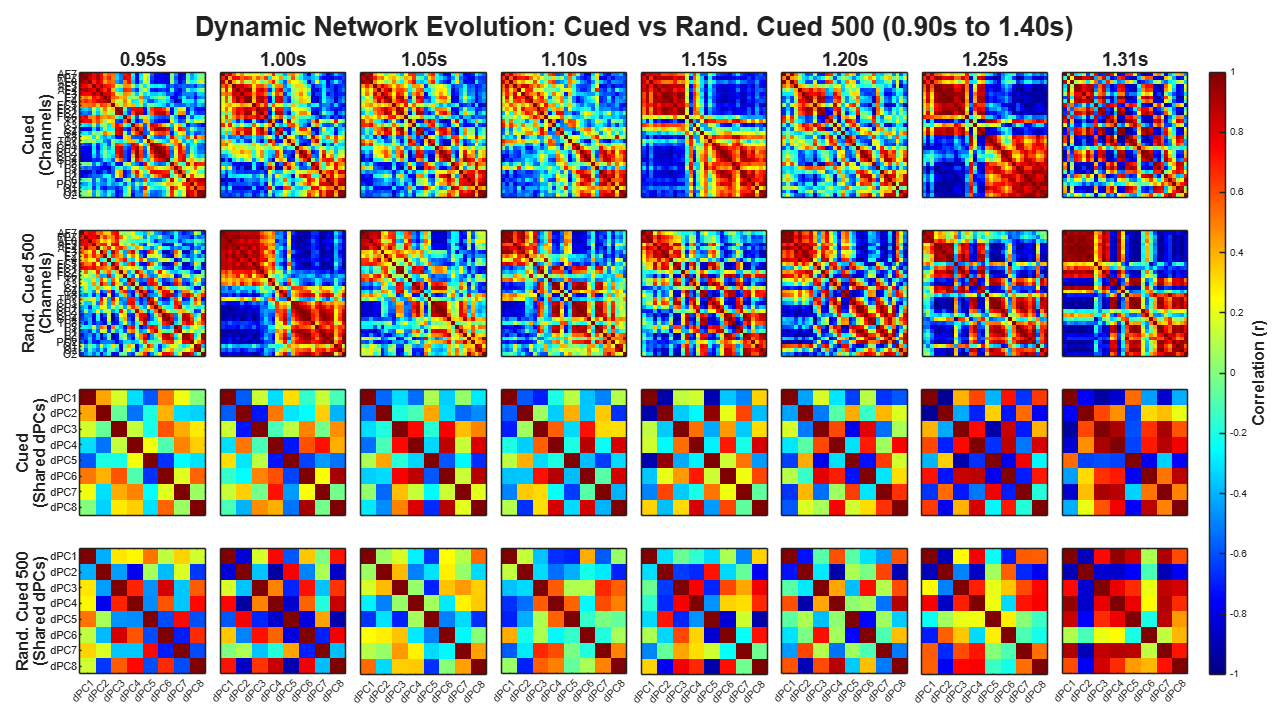

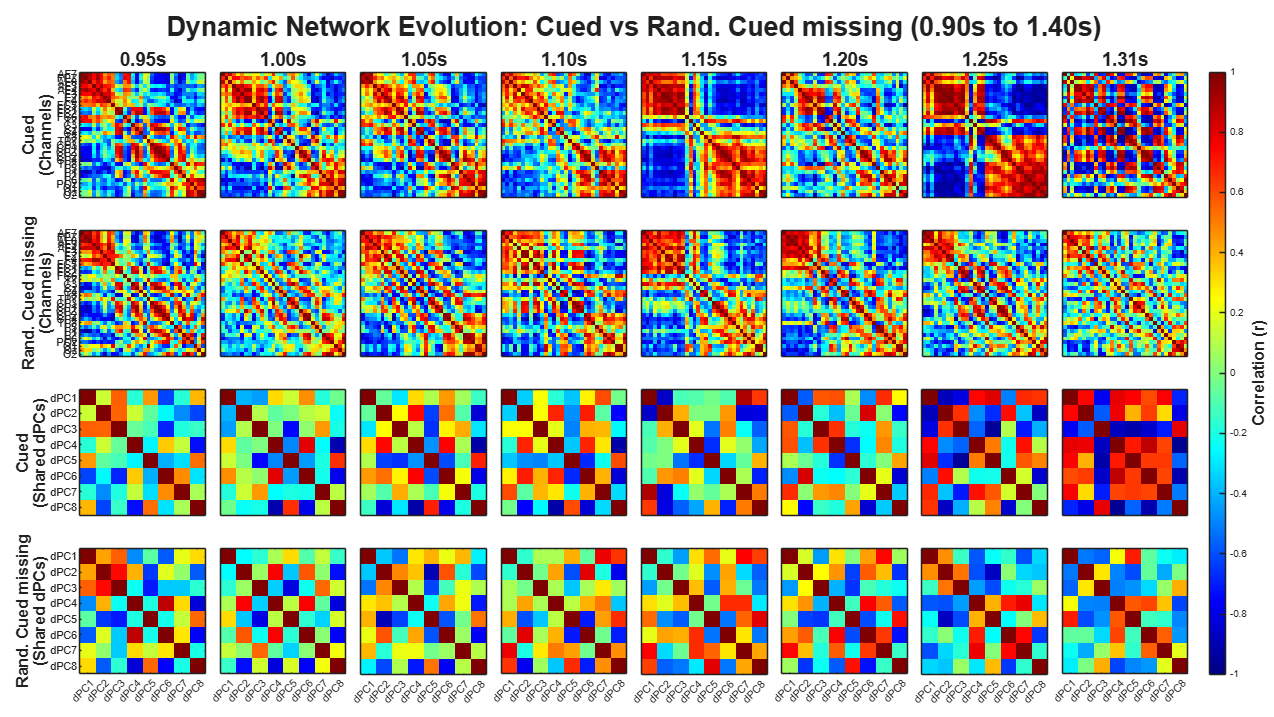


% Inline helper functions
get_clean_name = @(c) strrep(strrep(strrep(strrep(strrep(strrep(c, ...
    'BLA', 'Auditory'), 'BLT', 'Tactile'), 'P1', 'Cued'), ...
    'P2', 'Unpred.'), 'P3', 'Rand. Cued'), '_', ' ');

% Define your Condition Pairs and their specific time boundaries
pairs = {
    {'BLA', 'P1', [0.4, 0.9]},
    {'BLT', 'P1', [0.9, 1.4]},
    {'P1', 'P2_500', [0.9, 1.4]},
    {'P1', 'P2_2000', [2.4, 2.9]},
    {'P1', 'P3_500', [0.9, 1.4]},
    {'P1', 'P3_missing', [0.9, 1.4]}
};

target_subj = 1; % Analyzing Subject 1
if isempty(fs), fs = EEG.srate; end % Fallback for sampling rate

% Sliding window configuration
window_size_ms = 100;
step_size_ms = 50;
win_samples = round((window_size_ms / 1000) * fs);
step_samples = round((step_size_ms / 1000) * fs);

% Check if channel labels exist
if ~exist('all_channels_str', 'var')
    all_channels_str = arrayfun(@(x) sprintf('Ch%d', x), 1:num_ch, 'UniformOutput', false);
end

for p = 1:length(pairs)
    condA = pairs{p}{1};
    condB = pairs{p}{2};
    t_win = pairs{p}{3};
    cleanA = get_clean_name(condA);
    cleanB = get_clean_name(condB);
    
    if ~isfield(data_subj_avg, condA) || ~isfield(data_subj_avg, condB)
        warning('Skipping pair %s vs %s (Missing data)', cleanA, cleanB);
        continue;
    end
    
    % 1. Extract FULL Data for Global DR [Channels x Time]
    dataA_full = data_subj_avg.(condA)(:, :, target_subj);
    dataB_full = data_subj_avg.(condB)(:, :, target_subj);
    
    if all(isnan(dataA_full(:))) || all(isnan(dataB_full(:))), continue; end
    
    %% --- DIMENSIONALITY REDUCTION (GLOBAL MANIFOLD) ---
    % Find shared latent space across the entire epoch for stable axes
    data_combined = [dataA_full, dataB_full];
    data_combined_centered = data_combined - mean(data_combined, 2);
    
    [k_opt, ~] = velicer_map(data_combined_centered', true);
    if k_opt < 2, k_opt = 2; end 
    
    try
        X_dpca = cat(3, dataA_full, dataB_full); 
        X_dpca_centered = bsxfun(@minus, X_dpca, mean(X_dpca(:,:), 2));
        [W_dpca, ~, ~] = dpca(X_dpca_centered, k_opt); 
        W = W_dpca'; % Transpose to [k x Channels]
    catch 
        [~, ~, V] = svd(data_combined_centered', 'econ');
        W = V(:, 1:k_opt)'; 
    end
    
    % Project full data into Shared Latent Space
    compA_full = W * (dataA_full - mean(dataA_full, 2)); 
    compB_full = W * (dataB_full - mean(dataB_full, 2));
    
    %% --- ISOLATE SPECIFIC SUB-WINDOW FOR SLIDING HEATMAPS ---
    idx_start = find(time_ms_eeg >= t_win(1), 1, 'first');
    idx_end = find(time_ms_eeg <= t_win(2), 1, 'last');
    
    dataA_chunk = dataA_full(:, idx_start:idx_end);
    dataB_chunk = dataB_full(:, idx_start:idx_end);
    compA_chunk = compA_full(:, idx_start:idx_end);
    compB_chunk = compB_full(:, idx_start:idx_end);
    
    time_chunk = time_ms_eeg(idx_start:idx_end);
    num_chunk_points = size(dataA_chunk, 2);
    
    % Set up sliding indices for this specific chunk
    start_idx = 1 : step_samples : (num_chunk_points - win_samples + 1);
    num_windows = length(start_idx);
    
    corr_ch_A_all = nan(num_ch, num_ch, num_windows);
    corr_ch_B_all = nan(num_ch, num_ch, num_windows);
    corr_pc_A_all = nan(k_opt, k_opt, num_windows);
    corr_pc_B_all = nan(k_opt, k_opt, num_windows);
    
    window_centers = zeros(1, num_windows);
    
    for w = 1:num_windows
        w_s = start_idx(w);
        w_e = w_s + win_samples - 1;
        
        window_centers(w) = mean(time_chunk(w_s:w_e));
        
        corr_ch_A_all(:,:,w) = corrcoef(dataA_chunk(:, w_s:w_e)');
        corr_ch_B_all(:,:,w) = corrcoef(dataB_chunk(:, w_s:w_e)');
        corr_pc_A_all(:,:,w) = corrcoef(compA_chunk(:, w_s:w_e)');
        corr_pc_B_all(:,:,w) = corrcoef(compB_chunk(:, w_s:w_e)');
    end
    
    %% --- PLOTTING FILMSTRIP SNAPSHOTS ---
    % Dynamically widen the figure based on how many windows we have (~200px per window)
    fig_width = max(1200, 200 * num_windows);
    fig = figure('Position', [50, 50, fig_width, 900], 'Name', sprintf('%s vs %s Filmstrip', cleanA, cleanB));
    tiledlayout(4, num_windows, 'TileSpacing', 'compact', 'Padding', 'compact');
    
    pc_labels = arrayfun(@(x) sprintf('dPC%d', x), 1:k_opt, 'UniformOutput', false);
    
    % ROW 1: Condition A (Channels)
    for w = 1:num_windows
        nexttile; imagesc(corr_ch_A_all(:,:,w));
        colormap('jet'); clim([-1 1]); axis square;
        if w == 1
            ylabel(sprintf('%s\n(Channels)', cleanA), 'FontSize', 12, 'FontWeight', 'bold');
            yticks(1:num_ch); yticklabels(all_channels_str);
        else yticks([]); end
        xticks([]);
        title(sprintf('%.2fs', window_centers(w)), 'FontSize', 14, 'FontWeight', 'bold');
    end
    
    % ROW 2: Condition B (Channels)
    for w = 1:num_windows
        nexttile; imagesc(corr_ch_B_all(:,:,w));
        colormap('jet'); clim([-1 1]); axis square;
        if w == 1
            ylabel(sprintf('%s\n(Channels)', cleanB), 'FontSize', 12, 'FontWeight', 'bold');
            yticks(1:num_ch); yticklabels(all_channels_str);
        else yticks([]); end
        xticks([]);
    end
    
    % ROW 3: Condition A (Latent PCs)
    for w = 1:num_windows
        nexttile; imagesc(corr_pc_A_all(:,:,w));
        colormap('jet'); clim([-1 1]); axis square;
        if w == 1
            ylabel(sprintf('%s\n(Shared dPCs)', cleanA), 'FontSize', 12, 'FontWeight', 'bold');
            yticks(1:k_opt); yticklabels(pc_labels);
        else yticks([]); end
        xticks([]);
    end
    
    % ROW 4: Condition B (Latent PCs)
    for w = 1:num_windows
        nexttile; imagesc(corr_pc_B_all(:,:,w));
        colormap('jet'); clim([-1 1]); axis square;
        if w == 1
            ylabel(sprintf('%s\n(Shared dPCs)', cleanB), 'FontSize', 12, 'FontWeight', 'bold');
            yticks(1:k_opt); yticklabels(pc_labels);
        else yticks([]); end
        xticks(1:k_opt); xticklabels(pc_labels); xtickangle(45);
    end
    
    % Master formatting
    cb = colorbar;
    cb.Layout.Tile = 'east';
    cb.Label.String = 'Correlation (r)';
    cb.Label.FontSize = 12;
    cb.Label.FontWeight = 'bold';
    
    sgtitle(sprintf('Dynamic Network Evolution: %s vs %s (%.2fs to %.2fs)', ...
        cleanA, cleanB, t_win(1), t_win(2)), 'FontSize', 20, 'FontWeight', 'bold');
        
    % Optional: Save figure directly to output path
    % saveas(fig, fullfile(output_path, sprintf('Filmstrip_%s_vs_%s.png', condA, condB)));
end

disp('Filmstrip Heatmaps generated successfully.');

Filmstrip Heatmaps generated successfully.


## 7. Extracting Non-Stimulus Channel Connectivity Heatmaps: estimating the Anticipatory Resting state

disp('Calculating Non-Stimulus Correlation Matrices per Group...');

Calculating Non-Stimulus Correlation Matrices per Group...


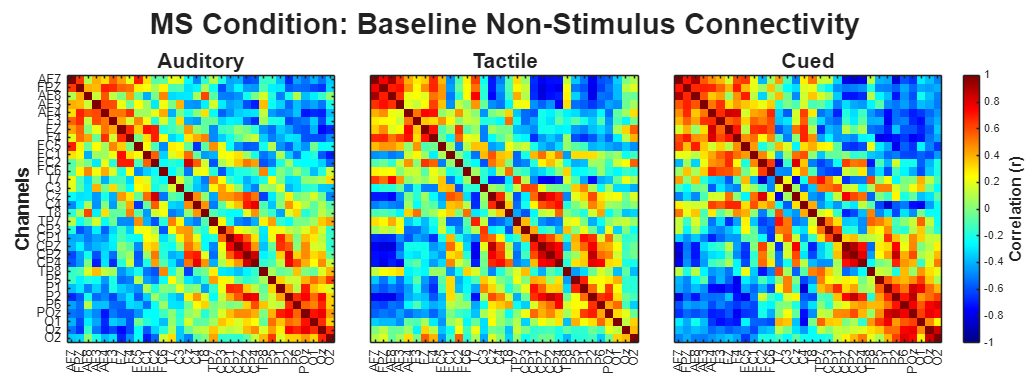

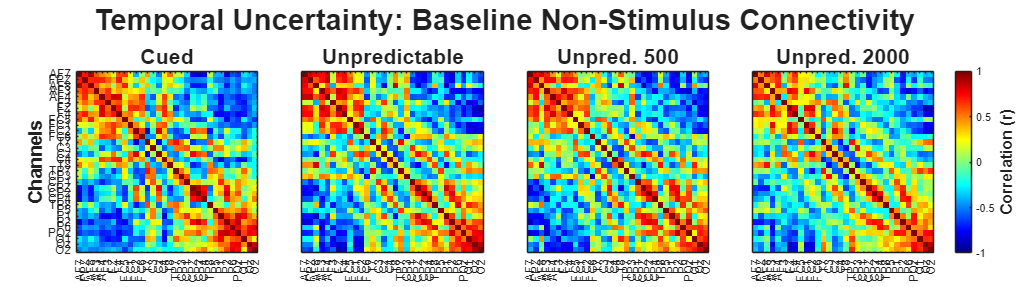

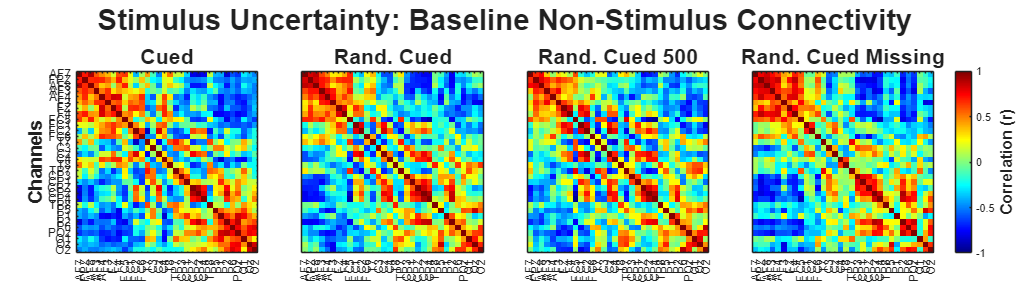


target_subj = 1; % Analyzing Subject 1

% 1. Define the Non-Stimulus Windows [Start, End] in seconds for each condition
non_stim_windows = struct();
non_stim_windows.BLA        = [0, 0.5; 1.0, 3.5];
non_stim_windows.BLT        = [0, 1.0; 1.5, 3.5];
non_stim_windows.P1         = [0, 0.5; 1.5, 3.5];
non_stim_windows.P2         = [0, 0.5; 1.5, 2.5; 3.0, 3.5];
non_stim_windows.P2_500     = [0, 0.5; 1.5, 3.5];
non_stim_windows.P2_2000    = [0, 0.5; 1.0, 2.5; 3.0, 3.5];
non_stim_windows.P3         = [0, 0.5; 1.5, 3.5];
non_stim_windows.P3_500     = [0, 0.5; 1.5, 3.5];
non_stim_windows.P3_missing = [0, 0.5; 1.0, 3.5];

% 2. Define the 3 Experimental Groups (Including P1 in Groups 2 and 3)
groups = struct();

% Group 1: MS Condition
groups(1).name = 'MS Condition';
groups(1).conds = {'BLA', 'BLT', 'P1'}; 

% Group 2: Temporal Uncertainty
groups(2).name = 'Temporal Uncertainty';
groups(2).conds = {'P1', 'P2', 'P2_500', 'P2_2000'};

% Group 3: Stimulus Uncertainty
groups(3).name = 'Stimulus Uncertainty';
groups(3).conds = {'P1', 'P3', 'P3_500', 'P3_missing'};

% Check if channel labels exist
if ~exist('all_channels_str', 'var')
    all_channels_str = arrayfun(@(x) sprintf('Ch%d', x), 1:num_ch, 'UniformOutput', false);
end

% 3. Loop through Groups to Generate Figures
for g = 1:length(groups)
    
    n_conds = length(groups(g).conds);
    
    % Dynamically size the figure based on the number of conditions
    fig = figure('Position', [0, 100, 450 * n_conds, 500], 'Name', sprintf('%s (Non-Stimulus)', groups(g).name));
    tiledlayout(1, n_conds, 'TileSpacing', 'compact', 'Padding', 'compact');
    
    for c = 1:n_conds
        c_name = groups(g).conds{c};
        
        % Ensure data exists for this condition
        if ~isfield(data_subj_avg, c_name)
            warning('Skipping %s (Missing data)', c_name);
            continue;
        end
        
        % Get the raw data [Channels x Time]
        raw_data = data_subj_avg.(c_name)(:, :, target_subj);
        if all(isnan(raw_data(:))), continue; end
        
        % Fetch the specific non-stimulus windows for this condition
        t_windows = non_stim_windows.(c_name);
        
        % Initialize empty array to hold concatenated non-stimulus data
        concat_non_stim_data = [];
        
        % Loop through the defined time windows and stitch the data together
        for w = 1:size(t_windows, 1)
            % Find indices matching the current [start, end] window
            idx = find(time_ms_eeg >= t_windows(w, 1) & time_ms_eeg <= t_windows(w, 2));
            
            % Concatenate along the time dimension
            concat_non_stim_data = [concat_non_stim_data, raw_data(:, idx)];
        end
        
        % Calculate Pearson Correlation on the concatenated non-stimulus data
        % (Transpose so that variables are columns)
        corr_ch = corrcoef(concat_non_stim_data');
        
        % Map to a Clean Name for the Title
        switch c_name
            case 'BLA',        clean_name = 'Auditory';
            case 'BLT',        clean_name = 'Tactile';
            case 'P1',         clean_name = 'Cued';
            case 'P2',         clean_name = 'Unpredictable';
            case 'P2_500',     clean_name = 'Unpred. 500';
            case 'P2_2000',    clean_name = 'Unpred. 2000';
            case 'P3',         clean_name = 'Rand. Cued';
            case 'P3_500',     clean_name = 'Rand. Cued 500';
            case 'P3_missing', clean_name = 'Rand. Cued Missing';
            otherwise,         clean_name = strrep(c_name, '_', ' ');
        end
        
        % Plotting the Tile
        nexttile;
        imagesc(corr_ch);
        colormap('jet'); clim([-1 1]); axis square;
        title(sprintf('%s', clean_name), 'FontSize', 16, 'FontWeight', 'bold');
        
        % Format X and Y axes
        xticks(1:num_ch); xticklabels(all_channels_str); xtickangle(90);
        if c == 1
            yticks(1:num_ch); yticklabels(all_channels_str);
            ylabel('Channels', 'FontSize', 14, 'FontWeight', 'bold');
        else
            yticks([]); % Hide Y-labels on middle/right tiles to keep it clean
        end
        
    end
    
    % Add Master Title and Colorbar
    cb = colorbar;
    cb.Layout.Tile = 'east';
    cb.Label.String = 'Correlation (r)';
    cb.Label.FontSize = 12;
    cb.Label.FontWeight = 'bold';
    
    sgtitle(sprintf('%s: Baseline Non-Stimulus Connectivity', groups(g).name), 'FontSize', 22, 'FontWeight', 'bold');
end


disp('Non-Stimulus Network Connectivity Heatmaps successfully generated!');

Non-Stimulus Network Connectivity Heatmaps successfully generated!


## Evaluating Start vs End Resting State Similarity

disp('Evaluating Start vs End Resting State Similarity...');

Evaluating Start vs End Resting State Similarity...



=== MS Condition ===


Condition: Auditory           | Cosine Similarity (Start vs End): 0.830
Condition: Tactile            | Cosine Similarity (Start vs End): 0.828
Condition: Cued               | Cosine Similarity (Start vs End): 0.729


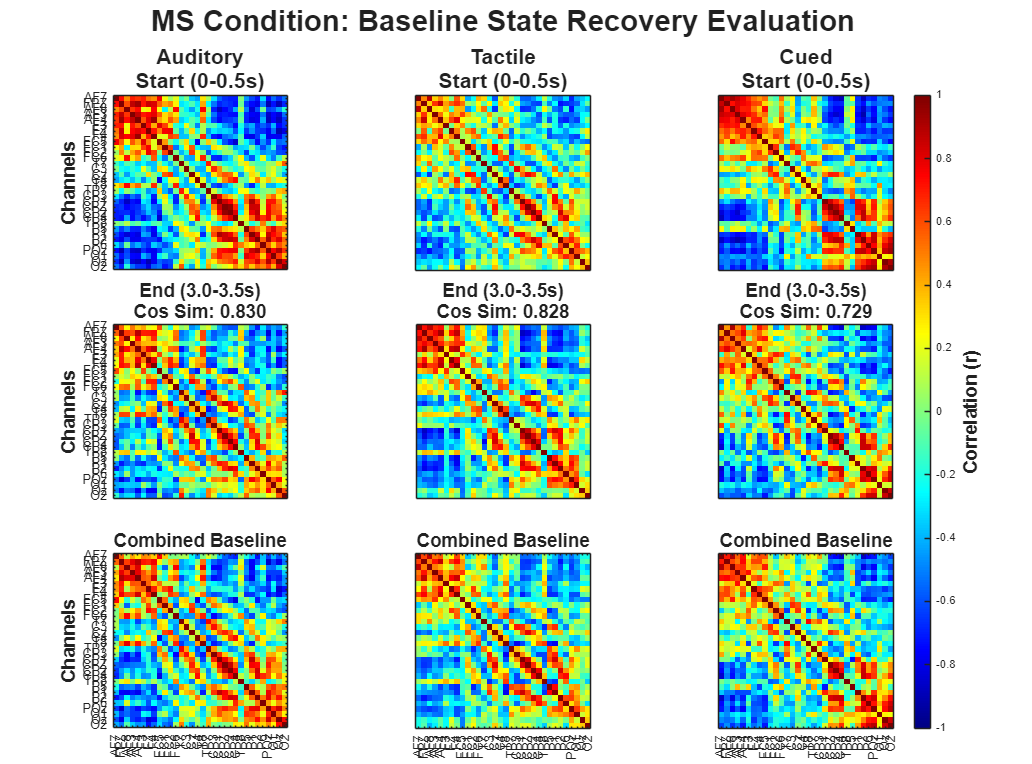


=== Temporal Uncertainty ===


Condition: Cued               | Cosine Similarity (Start vs End): 0.729
Condition: Unpredictable      | Cosine Similarity (Start vs End): 0.662
Condition: Unpred. 500        | Cosine Similarity (Start vs End): 0.837
Condition: Unpred. 2000       | Cosine Similarity (Start vs End): 0.680


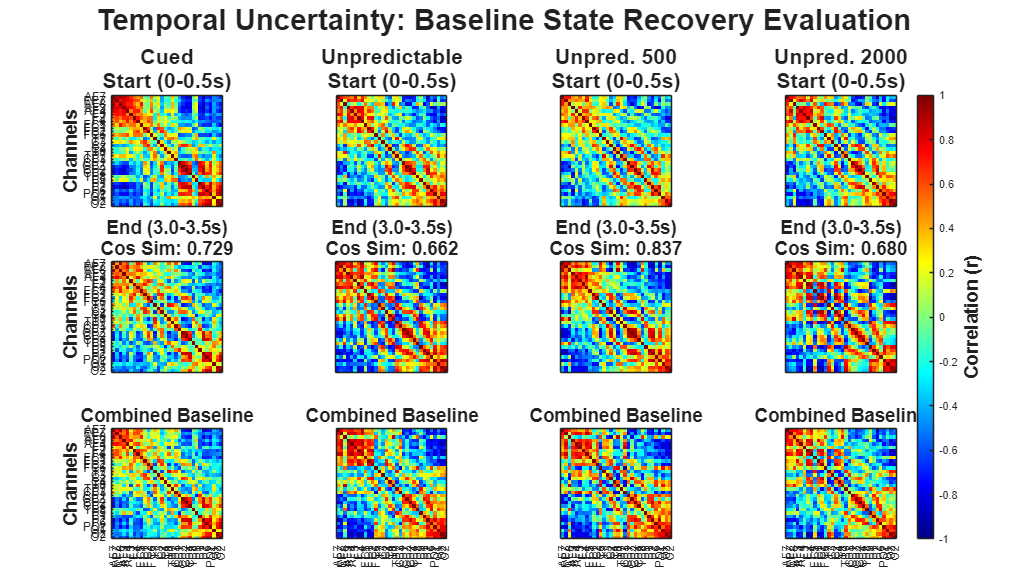


=== Stimulus Uncertainty ===


Condition: Cued               | Cosine Similarity (Start vs End): 0.729
Condition: Rand. Cued         | Cosine Similarity (Start vs End): 0.803
Condition: Rand. Cued 500     | Cosine Similarity (Start vs End): 0.786
Condition: Rand. Cued Missing | Cosine Similarity (Start vs End): 0.849


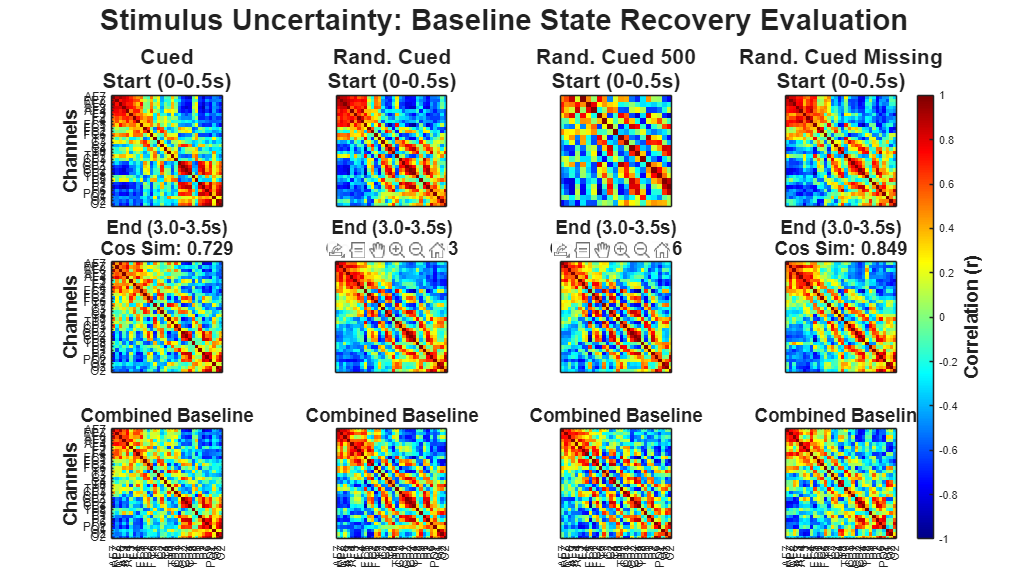


target_subj = 1; % Analyzing Subject 1

% 1. Define the 3 Experimental Groups (Including P1 in Groups 2 and 3)
groups = struct();

% Group 1: MS Condition
groups(1).name = 'MS Condition';
groups(1).conds = {'BLA', 'BLT', 'P1'}; 

% Group 2: Temporal Uncertainty
groups(2).name = 'Temporal Uncertainty';
groups(2).conds = {'P1', 'P2', 'P2_500', 'P2_2000'};

% Group 3: Stimulus Uncertainty
groups(3).name = 'Stimulus Uncertainty';
groups(3).conds = {'P1', 'P3', 'P3_500', 'P3_missing'};

% Check if channel labels exist
if ~exist('all_channels_str', 'var')
    all_channels_str = arrayfun(@(x) sprintf('Ch%d', x), 1:num_ch, 'UniformOutput', false);
end

% Define Universal Start and End Windows for the baseline check
t_start_win = [0, 0.5];
t_end_win   = [3.0, 3.5];

% 2. Loop through Groups to Evaluate and Plot
for g = 1:length(groups)
    
    n_conds = length(groups(g).conds);
    
    % Pre-allocate storage for this group to plot row-by-row
    mats_start  = cell(1, n_conds);
    mats_end    = cell(1, n_conds);
    mats_comb   = cell(1, n_conds);
    sim_scores  = zeros(1, n_conds);
    clean_names = cell(1, n_conds);
    
    fprintf('\n=== %s ===\n', groups(g).name);
    
    for c = 1:n_conds
        c_name = groups(g).conds{c};
        
        switch c_name
            case 'BLA',        clean_name = 'Auditory';
            case 'BLT',        clean_name = 'Tactile';
            case 'P1',         clean_name = 'Cued';
            case 'P2',         clean_name = 'Unpredictable';
            case 'P2_500',     clean_name = 'Unpred. 500';
            case 'P2_2000',    clean_name = 'Unpred. 2000';
            case 'P3',         clean_name = 'Rand. Cued';
            case 'P3_500',     clean_name = 'Rand. Cued 500';
            case 'P3_missing', clean_name = 'Rand. Cued Missing';
            otherwise,         clean_name = strrep(c_name, '_', ' ');
        end
        clean_names{c} = clean_name;
        
        % Ensure data exists for this condition
        if ~isfield(data_subj_avg, c_name)
            warning('Skipping %s (Missing data)', c_name);
            continue;
        end
        
        % Get the raw data [Channels x Time]
        raw_data = data_subj_avg.(c_name)(:, :, target_subj);
        if all(isnan(raw_data(:))), continue; end
        
        % Extract Indices for Start and End windows
        idx_start = find(time_ms_eeg >= t_start_win(1) & time_ms_eeg <= t_start_win(2));
        idx_end   = find(time_ms_eeg >= t_end_win(1) & time_ms_eeg <= t_end_win(2));
        
        % Slice the data matrices
        data_start = raw_data(:, idx_start);
        data_end   = raw_data(:, idx_end);
        
        % Calculate Pearson Correlations
        corr_start = corrcoef(data_start');
        corr_end   = corrcoef(data_end');
        corr_comb  = corrcoef([data_start, data_end]'); % The Combined matrix
        
        % Calculate Cosine Similarity (Flattening the upper triangle to avoid diagonal 1s)
        mask = triu(true(num_ch), 1);
        v_start = corr_start(mask);
        v_end   = corr_end(mask);
        
        % Cosine Similarity Formula: (A dot B) / (||A|| * ||B||)
        cos_sim = dot(v_start, v_end) / (norm(v_start) * norm(v_end));
        
        % Print result to terminal
        fprintf('Condition: %-18s | Cosine Similarity (Start vs End): %.3f\n', clean_name, cos_sim);
        
        % Store for tiled plotting
        mats_start{c} = corr_start;
        mats_end{c}   = corr_end;
        mats_comb{c}  = corr_comb;
        sim_scores(c) = cos_sim;
    end
    
    % --- PLOTTING ---
    fig = figure('Position', [0, 100, 450 * n_conds, 1000], 'Name', sprintf('%s (Baseline Evaluation)', groups(g).name));
    tiledlayout(3, n_conds, 'TileSpacing', 'compact', 'Padding', 'compact');
    c_lim_mat = [-1 1];
    
    % ROW 1: START (0 - 0.5s)
    for c = 1:n_conds
        nexttile; imagesc(mats_start{c}); colormap(gca, 'jet'); clim(c_lim_mat); axis square;
        title(sprintf('%s\nStart (0-0.5s)', clean_names{c}), 'FontSize', 16, 'FontWeight', 'bold');
        xticks([]); 
        if c == 1
            yticks(1:num_ch); yticklabels(all_channels_str); ylabel('Channels', 'FontSize', 14, 'FontWeight', 'bold');
        else, yticks([]); end
    end
    
    % ROW 2: END (3.0 - 3.5s)
    for c = 1:n_conds
        nexttile; imagesc(mats_end{c}); colormap(gca, 'jet'); clim(c_lim_mat); axis square;
        title(sprintf('End (3.0-3.5s)\nCos Sim: %.3f', sim_scores(c)), 'FontSize', 14, 'FontWeight', 'bold');
        xticks([]); 
        if c == 1
            yticks(1:num_ch); yticklabels(all_channels_str); ylabel('Channels', 'FontSize', 14, 'FontWeight', 'bold');
        else, yticks([]); end
    end
    
    % ROW 3: COMBINED BASELINE
    for c = 1:n_conds
        nexttile; imagesc(mats_comb{c}); colormap(gca, 'jet'); clim(c_lim_mat); axis square;
        title('Combined Baseline', 'FontSize', 14, 'FontWeight', 'bold');
        xticks(1:num_ch); xticklabels(all_channels_str); xtickangle(90);
        if c == 1
            yticks(1:num_ch); yticklabels(all_channels_str); ylabel('Channels', 'FontSize', 14, 'FontWeight', 'bold');
        else, yticks([]); end
        if c == n_conds, ax_cb = gca; end
    end
    
    % Master Title and Colorbar
    cb = colorbar(ax_cb); cb.Layout.Tile = 'east';
    cb.Label.String = 'Correlation (r)'; cb.Label.FontSize = 14; cb.Label.FontWeight = 'bold';
    
    sgtitle(sprintf('%s: Baseline State Recovery Evaluation', groups(g).name), 'FontSize', 22, 'FontWeight', 'bold');
end

## Connectivity Extraction via Covariance: Stimulus & Cognitive Windows (Z-Scored)

disp('Extracting Correlation for Stimulus and Cognitive Windows...');

Extracting Correlation for Stimulus and Cognitive Windows...



=== Processing: Stimulus State ===



=== Processing: Cognitive State ===


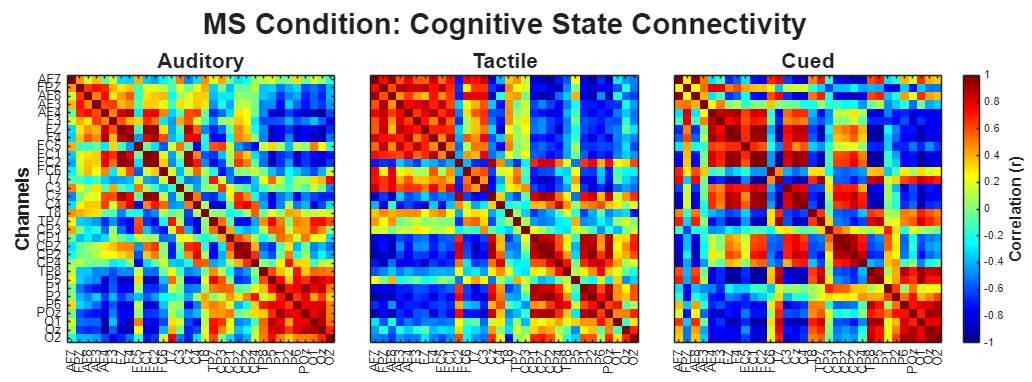

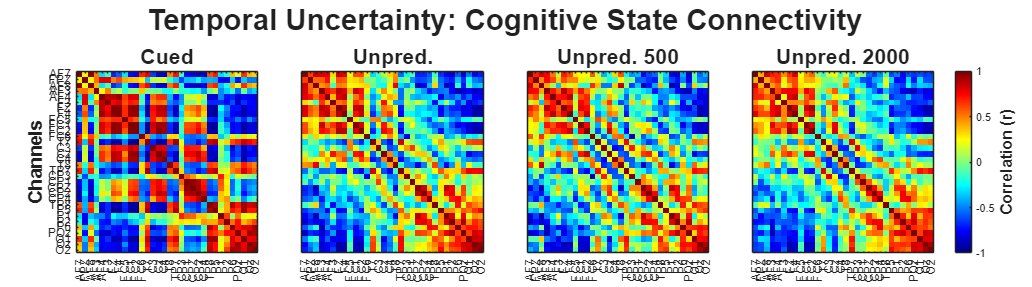

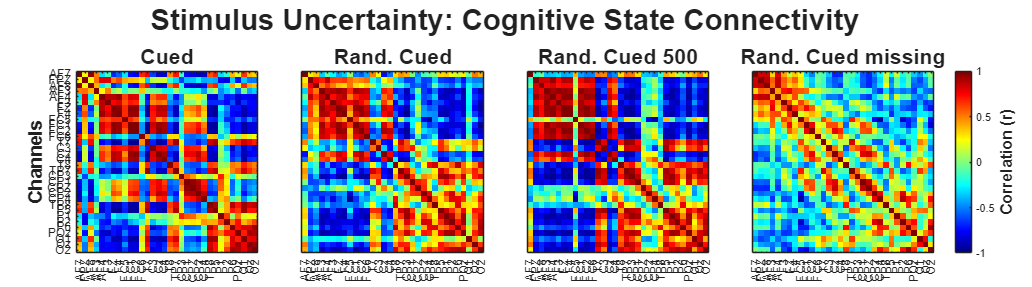


target_subj = 1; 

% 1. Define the Stimulus Windows
stim_windows = struct();
stim_windows.BLA        = [0.5, 0.85];
stim_windows.BLT        = [1.0, 1.35];
stim_windows.P1         = [0.5, 0.85; 1.0, 1.35];
stim_windows.P2         = [0.5, 0.85; 2.5, 2.85];
stim_windows.P2_500     = [0.5, 0.85; 1.0, 1.35];
stim_windows.P2_2000    = [0.5, 0.85; 2.5, 2.85];
stim_windows.P3         = [0.5, 0.85; 1.0, 1.35];
stim_windows.P3_500     = [0.5, 0.85; 1.0, 1.35];
stim_windows.P3_missing = [0.5, 0.85];

% 2. Define the Cognitive Windows
cog_windows = struct();
cog_windows.BLA        = [0.85, 1.0];
cog_windows.BLT        = [1.35, 1.5];
cog_windows.P1         = [0.85, 1.0; 1.35, 1.5];
cog_windows.P2         = [0.85, 1.0; 1.35, 2.5; 2.85, 3.0];
cog_windows.P2_500     = [0.85, 1.0; 1.35, 3.0];
cog_windows.P2_2000    = [0.85, 2.5; 2.85, 3.0];
cog_windows.P3         = [0.85, 1.0; 1.35, 1.5];
cog_windows.P3_500     = [0.85, 1.0; 1.35, 1.5];
cog_windows.P3_missing = [0.85, 1.5];

% Put them in a cell array so we can loop through both states effortlessly
state_dicts = {stim_windows, cog_windows};
state_names = {'Stimulus State', 'Cognitive State'};

% Define the 3 Experimental Groups
groups = struct();
groups(1).name = 'MS Condition';
groups(1).conds = {'BLA', 'BLT', 'P1'};
groups(2).name = 'Temporal Uncertainty';
groups(2).conds = {'P1', 'P2', 'P2_500', 'P2_2000'};
groups(3).name = 'Stimulus Uncertainty';
groups(3).conds = {'P1', 'P3', 'P3_500', 'P3_missing'};

get_clean_name = @(c) strrep(strrep(strrep(strrep(strrep(strrep(c, ...
    'BLA', 'Auditory'), 'BLT', 'Tactile'), 'P1', 'Cued'), ...
    'P2', 'Unpred.'), 'P3', 'Rand. Cued'), '_', ' ');

if ~exist('all_channels_str', 'var')
    all_channels_str = arrayfun(@(x) sprintf('Ch%d', x), 1:num_ch, 'UniformOutput', false);
end

% LOOP OVER THE TWO STATES (Stimulus then Cognitive)
for state_idx = 1:2
    active_windows = state_dicts{state_idx};
    active_state_name = state_names{state_idx};
    
    fprintf('\n=== Processing: %s ===\n', active_state_name);
    
    % Loop through Groups
    for g = 1:length(groups)
        n_conds = length(groups(g).conds);
        
        fig = figure('Position', [100, 100, 450 * n_conds, 500], ...
            'Name', sprintf('%s (%s)', groups(g).name, active_state_name));
        tiledlayout(1, n_conds, 'TileSpacing', 'compact', 'Padding', 'compact');
        
        for c = 1:n_conds
            c_name = groups(g).conds{c};
            
            if ~isfield(data_subj_avg, c_name)
                continue;
            end
            
            % 1. Get raw trial-averaged data [Channels x Time]
            raw_data = data_subj_avg.(c_name)(:, :, target_subj);
            if all(isnan(raw_data(:))), continue; end
            
            % 2. Extract specific time windows directly from raw data
            t_windows = active_windows.(c_name);
            concat_data = [];
            
            for w = 1:size(t_windows, 1)
                idx = find(time_ms_eeg >= t_windows(w, 1) & time_ms_eeg <= t_windows(w, 2));
                concat_data = [concat_data, raw_data(:, idx)];
            end
            
            % 3. CORRELATION (Calculates standard deviation implicitly per window)
            conn_matrix = corrcoef(concat_data');
            
            clean_name = get_clean_name(c_name);
            
            % Plotting
            nexttile;
            imagesc(conn_matrix);
            colormap('jet'); clim([-1 1]); axis square;
            title(sprintf('%s', clean_name), 'FontSize', 16, 'FontWeight', 'bold');
            
            xticks(1:num_ch); xticklabels(all_channels_str); xtickangle(90);
            if c == 1
                yticks(1:num_ch); yticklabels(all_channels_str);
                ylabel('Channels', 'FontSize', 14, 'FontWeight', 'bold');
            else
                yticks([]); 
            end
        end
        
        cb = colorbar;
        cb.Layout.Tile = 'east';
        cb.Label.String = 'Correlation (r)';
        cb.Label.FontSize = 12;
        cb.Label.FontWeight = 'bold';
        
        sgtitle(sprintf('%s: %s Connectivity', groups(g).name, active_state_name), ...
            'FontSize', 22, 'FontWeight', 'bold');
    end
end


disp('Stimulus and Cognitive Window processing complete!');

Stimulus and Cognitive Window processing complete!


## Extracting Background-Subtracted Correlation for Stimulus and Cognitive Windows


disp('Extracting Background-Subtracted Correlation for Stimulus and Cognitive Windows...');

Extracting Background-Subtracted Correlation for Stimulus and Cognitive Windows...



=== Processing: Stimulus State ===


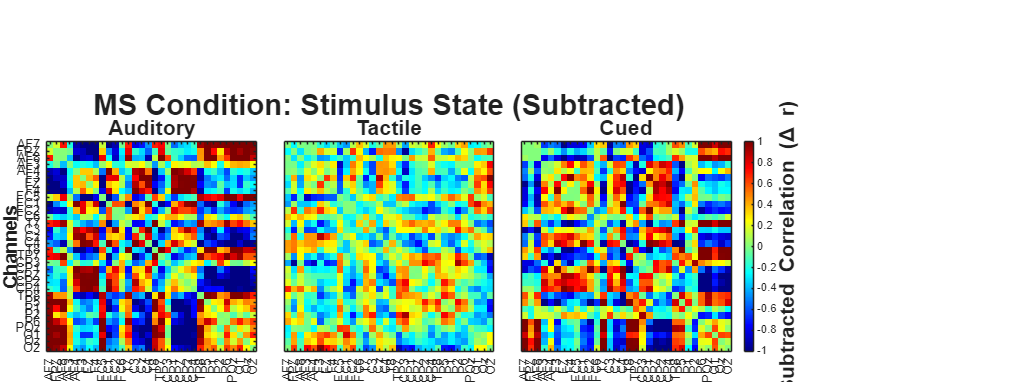

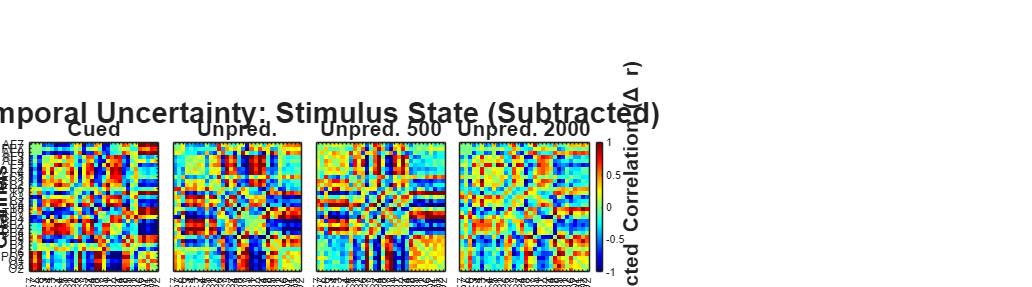

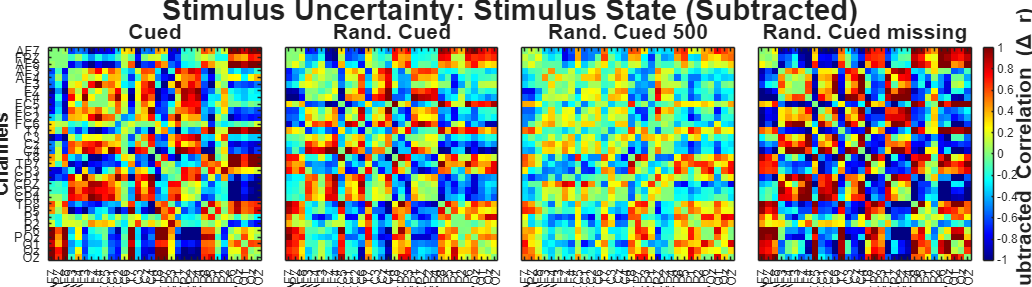


=== Processing: Cognitive State ===


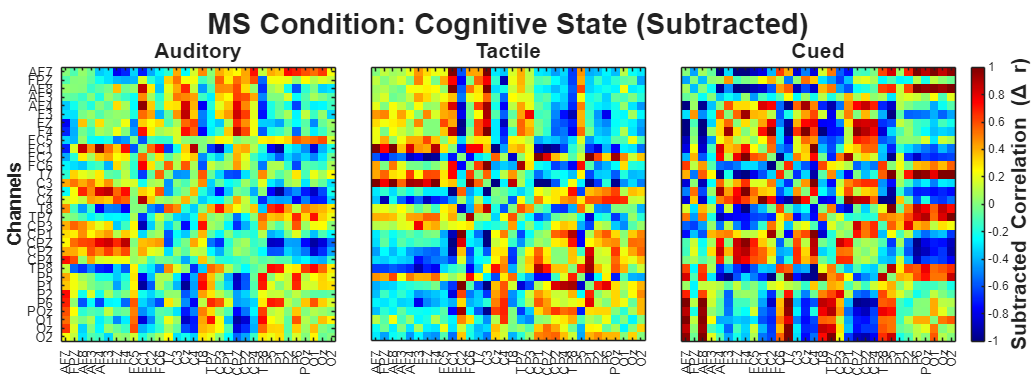

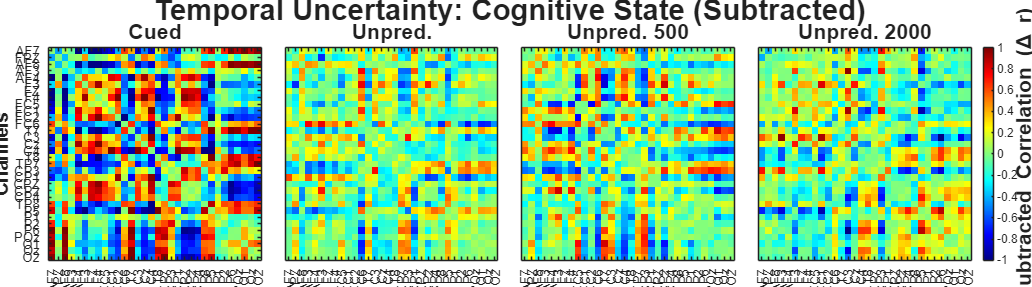

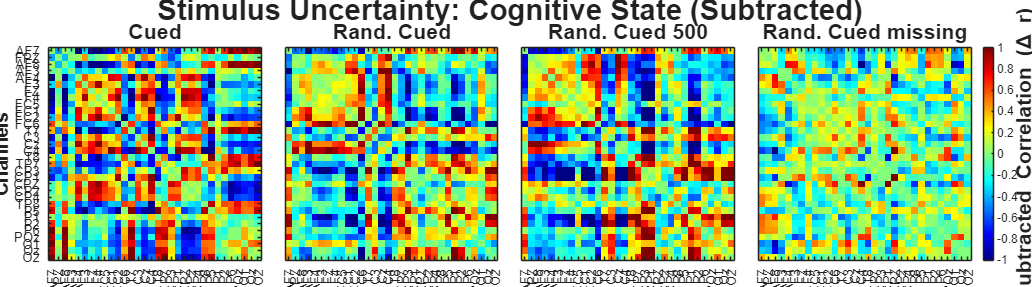


target_subj = 1; 

% --- Universal Resting State Background Windows (Start + End Combined) ---
bg_windows = [0, 0.5; 3.0, 3.5];

% 1. Define the Stimulus Windows
stim_windows = struct();
stim_windows.BLA        = [0.5, 0.85];
stim_windows.BLT        = [1.0, 1.35];
stim_windows.P1         = [0.5, 0.85; 1.0, 1.35];
stim_windows.P2         = [0.5, 0.85; 2.5, 2.85];
stim_windows.P2_500     = [0.5, 0.85; 1.0, 1.35];
stim_windows.P2_2000    = [0.5, 0.85; 2.5, 2.85];
stim_windows.P3         = [0.5, 0.85; 1.0, 1.35];
stim_windows.P3_500     = [0.5, 0.85; 1.0, 1.35];
stim_windows.P3_missing = [0.5, 0.85];

% 2. Define the Cognitive Windows
cog_windows = struct();
cog_windows.BLA        = [0.85, 1.0];
cog_windows.BLT        = [1.35, 1.5];
cog_windows.P1         = [0.85, 1.0; 1.35, 1.5];
cog_windows.P2         = [0.85, 1.0; 1.35, 2.5; 2.85, 3.0];
cog_windows.P2_500     = [0.85, 1.0; 1.35, 3.0];
cog_windows.P2_2000    = [0.85, 2.5; 2.85, 3.0];
cog_windows.P3         = [0.85, 1.0; 1.35, 1.5];
cog_windows.P3_500     = [0.85, 1.0; 1.35, 1.5];
cog_windows.P3_missing = [0.85, 1.5];

% Put them in a cell array so we can loop through both states effortlessly
state_dicts = {stim_windows, cog_windows};
state_names = {'Stimulus State', 'Cognitive State'};

% Define the 3 Experimental Groups
groups = struct();
groups(1).name = 'MS Condition';
groups(1).conds = {'BLA', 'BLT', 'P1'};
groups(2).name = 'Temporal Uncertainty';
groups(2).conds = {'P1', 'P2', 'P2_500', 'P2_2000'};
groups(3).name = 'Stimulus Uncertainty';
groups(3).conds = {'P1', 'P3', 'P3_500', 'P3_missing'};

get_clean_name = @(c) strrep(strrep(strrep(strrep(strrep(strrep(c, ...
    'BLA', 'Auditory'), 'BLT', 'Tactile'), 'P1', 'Cued'), ...
    'P2', 'Unpred.'), 'P3', 'Rand. Cued'), '_', ' ');

if ~exist('all_channels_str', 'var')
    all_channels_str = arrayfun(@(x) sprintf('Ch%d', x), 1:num_ch, 'UniformOutput', false);
end

% LOOP OVER THE TWO STATES (Stimulus then Cognitive)
for state_idx = 1:2
    active_windows = state_dicts{state_idx};
    active_state_name = state_names{state_idx};
    
    fprintf('\n=== Processing: %s ===\n', active_state_name);
    
    % Loop through Groups
    for g = 1:length(groups)
        n_conds = length(groups(g).conds);
        
        fig = figure('Position', [100, 100, 450 * n_conds, 500], ...
            'Name', sprintf('%s (%s)', groups(g).name, active_state_name));
        tiledlayout(1, n_conds, 'TileSpacing', 'compact', 'Padding', 'compact');
        
        for c = 1:n_conds
            c_name = groups(g).conds{c};
            
            if ~isfield(data_subj_avg, c_name)
                continue;
            end
            
            % 1. Get raw trial-averaged data [Channels x Time]
            raw_data = data_subj_avg.(c_name)(:, :, target_subj);
            if all(isnan(raw_data(:))), continue; end
            
            % --- A. CALCULATE COMBINED BACKGROUND CORRELATION ---
            concat_bg_data = [];
            for w = 1:size(bg_windows, 1)
                idx_bg = find(time_ms_eeg >= bg_windows(w, 1) & time_ms_eeg <= bg_windows(w, 2));
                concat_bg_data = [concat_bg_data, raw_data(:, idx_bg)];
            end
            bg_matrix = corrcoef(concat_bg_data');
            
            % --- B. CALCULATE ACTIVE STATE CORRELATION ---
            t_windows = active_windows.(c_name);
            concat_active_data = [];
            for w = 1:size(t_windows, 1)
                idx_act = find(time_ms_eeg >= t_windows(w, 1) & time_ms_eeg <= t_windows(w, 2));
                concat_active_data = [concat_active_data, raw_data(:, idx_act)];
            end
            active_matrix = corrcoef(concat_active_data');
            
            % --- C. SUBTRACT BACKGROUND ---
            sub_matrix = active_matrix - bg_matrix;
            
            clean_name = get_clean_name(c_name);
            
            % Plotting
            nexttile;
            imagesc(sub_matrix);
            colormap('jet'); clim([-1 1]); axis square;
            title(sprintf('%s', clean_name), 'FontSize', 16, 'FontWeight', 'bold');
            
            xticks(1:num_ch); xticklabels(all_channels_str); xtickangle(90);
            if c == 1
                yticks(1:num_ch); yticklabels(all_channels_str);
                ylabel('Channels', 'FontSize', 14, 'FontWeight', 'bold');
            else
                yticks([]); 
            end
        end
        
        cb = colorbar;
        cb.Layout.Tile = 'east';
        cb.Label.String = 'Subtracted Correlation (\Delta r)';
        cb.Label.FontSize = 16;
        cb.Label.FontWeight = 'bold';
        
        sgtitle(sprintf('%s: %s (Subtracted)', groups(g).name, active_state_name), ...
            'FontSize', 22, 'FontWeight', 'bold');
    end
end


disp('Stimulus and Cognitive Window processing complete!');

Stimulus and Cognitive Window processing complete!


## Permutation Analysis: Computing Background Connectivity per Group

%% Permutation Analysis: Computing Background Connectivity per Group
disp('Running Trial-Shuffle Permutation (1000x) to Compute Background Activity...');

Running Trial-Shuffle Permutation (1000x) to Compute Background Activity...


Processing Auditory: Shuffling 60 random trials 1000 times...
Processing Tactile: Shuffling 60 random trials 1000 times...
Processing Cued: Shuffling 60 random trials 1000 times...


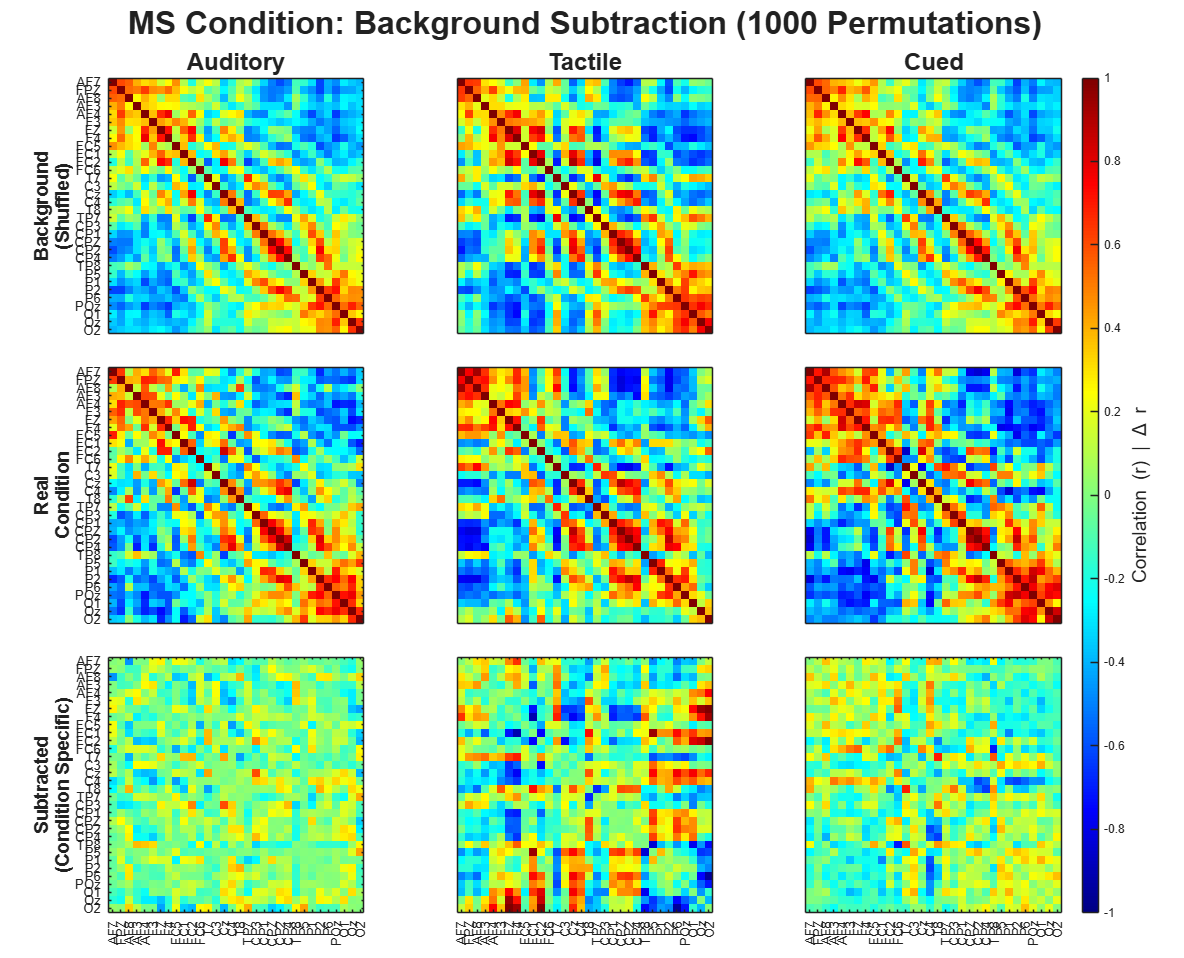

Processing Cued: Shuffling 60 random trials 1000 times...
Processing Unpred.: Shuffling 60 random trials 1000 times...
Processing Unpred. 500: Shuffling 30 random trials 1000 times...
Processing Unpred. 2000: Shuffling 30 random trials 1000 times...


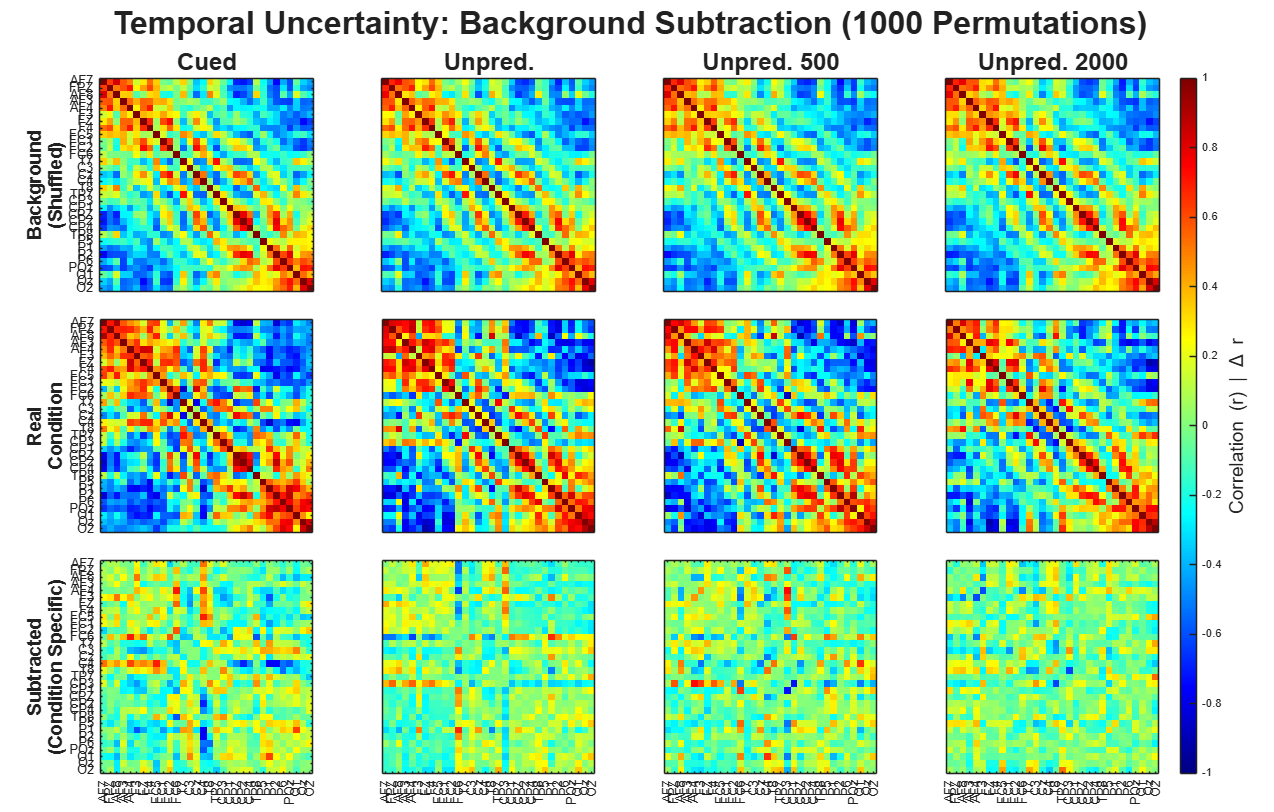

Processing Cued: Shuffling 60 random trials 1000 times...
Processing Rand. Cued: Shuffling 60 random trials 1000 times...
Processing Rand. Cued 500: Shuffling 30 random trials 1000 times...
Processing Rand. Cued missing: Shuffling 30 random trials 1000 times...


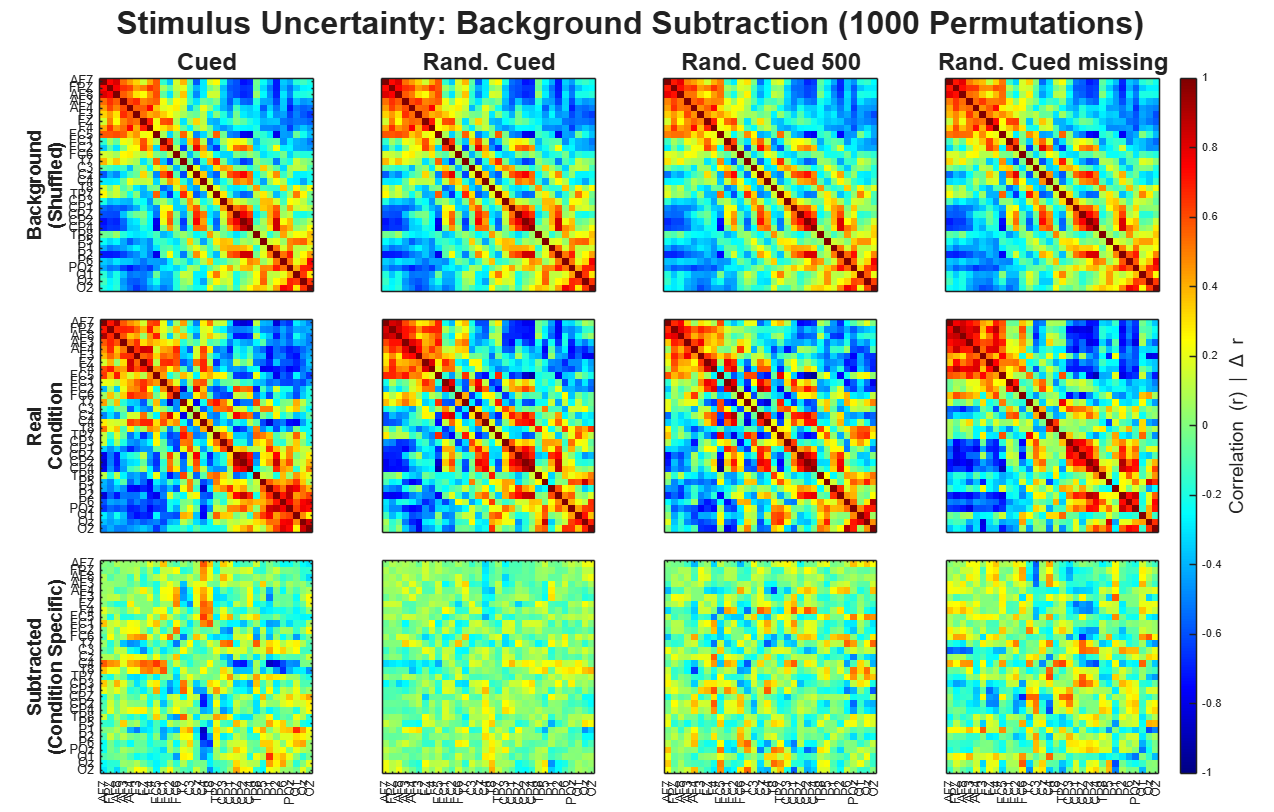


n_perms = 1000;
target_subj = 1;

% 1. Define the Non-Stimulus Windows [Start, End] in seconds for each condition
non_stim_windows = struct();
non_stim_windows.BLA        = [0, 0.5; 1.0, 3.5];
non_stim_windows.BLT        = [0, 1.0; 1.5, 3.5];
non_stim_windows.P1         = [0, 0.5; 1.5, 3.5];
non_stim_windows.P2         = [0, 0.5; 1.5, 2.5; 3.0, 3.5];
non_stim_windows.P2_500     = [0, 0.5; 1.5, 3.5];
non_stim_windows.P2_2000    = [0, 0.5; 1.0, 2.5; 3.0, 3.5];
non_stim_windows.P3         = [0, 0.5; 1.5, 3.5];
non_stim_windows.P3_500     = [0, 0.5; 1.5, 3.5];
non_stim_windows.P3_missing = [0, 0.5; 1.0, 3.5];

% 2. Define the 3 Experimental Groups
groups = struct();
groups(1).name = 'MS Condition';
groups(1).conds = {'BLA', 'BLT', 'P1'};

groups(2).name = 'Temporal Uncertainty';
groups(2).conds = {'P1', 'P2', 'P2_500', 'P2_2000'};

groups(3).name = 'Stimulus Uncertainty';
groups(3).conds = {'P1', 'P3', 'P3_500', 'P3_missing'};

% Inline helper to clean names
get_clean_name = @(c) strrep(strrep(strrep(strrep(strrep(strrep(c, ...
    'BLA', 'Auditory'), 'BLT', 'Tactile'), 'P1', 'Cued'), ...
    'P2', 'Unpred.'), 'P3', 'Rand. Cued'), '_', ' ');

if ~exist('all_channels_str', 'var')
    all_channels_str = arrayfun(@(x) sprintf('Ch%d', x), 1:num_ch, 'UniformOutput', false);
end

% 3. Loop through Groups to Generate Figures
for g = 1:length(groups)
    n_conds = length(groups(g).conds);
    
    % --- A. Pool All Trials for the Current Group ---
    pooled_trials = [];
    cond_trial_counts = zeros(1, n_conds);
    
    for c = 1:n_conds
        c_name = groups(g).conds{c};
        if isfield(data_all_conds, c_name) && length(data_all_conds.(c_name)) >= target_subj
            c_trials = data_all_conds.(c_name){target_subj};
            pooled_trials = cat(3, pooled_trials, c_trials); % Concatanating all conditions in each condition groups (MS, Temp, Stim)
            cond_trial_counts(c) = size(c_trials, 3);
        end
    end
    
    total_pool_size = size(pooled_trials, 3);
    if total_pool_size == 0, continue; end
    
    % Preallocate data storage for plotting (since we have to plot row-by-row)
    store_real = cell(1, n_conds);
    store_bg = cell(1, n_conds);
    store_sub = cell(1, n_conds);
    clean_names = cell(1, n_conds);
    
    % --- B. Process Each Condition (Data Calculation) ---
    for c = 1:n_conds
        c_name = groups(g).conds{c};
        clean_names{c} = get_clean_name(c_name);
        n_trials = cond_trial_counts(c);
        
        if n_trials == 0, continue; end
        
        t_windows = non_stim_windows.(c_name);
        idx_C = [];
        for w = 1:size(t_windows, 1)
            idx_C = [idx_C, find(time_ms_eeg >= t_windows(w, 1) & time_ms_eeg <= t_windows(w, 2))];
        end
        
        % 1. Real Connectivity
        real_trials = data_all_conds.(c_name){target_subj}(:, idx_C, :);
        real_avg = mean(real_trials, 3, 'omitnan');
        store_real{c} = corrcoef(real_avg');
        
        % 2. Background Connectivity (Permutation)
        null_corr = nan(num_ch, num_ch, n_perms);
        fprintf('Processing %s: Shuffling %d random trials %d times...\n', clean_names{c}, n_trials, n_perms);
        
        for p = 1:n_perms
            rand_idx = randperm(total_pool_size, n_trials); % Randomly drawing the trials without replacement
            pseudo_trials = pooled_trials(:, idx_C, rand_idx);
            pseudo_avg = mean(pseudo_trials, 3, 'omitnan');
            null_corr(:,:,p) = corrcoef(pseudo_avg');
        end
        
        store_bg{c} = mean(null_corr, 3, 'omitnan'); % Calculating the Null distribution mean
        
        % 3. Subtracted Connectivity
        store_sub{c} = store_real{c} - store_bg{c};
    end
    
    % --- C. Plotting the Grid (Row by Row) ---
    % Figure widens based on number of columns (conditions)
    fig = figure('Position', [50, 50, 450 * n_conds, 1100], 'Name', sprintf('%s Permutation', groups(g).name));
    tiledlayout(3, n_conds, 'TileSpacing', 'compact', 'Padding', 'compact');
    
    c_lim_raw = [-1 1];
    c_lim_clean = [-1 1]; 
    
    % ROW 1: Background Connectivity
    for c = 1:n_conds
        nexttile; imagesc(store_bg{c}); colormap('jet'); clim(c_lim_raw); axis square;
        title(clean_names{c}, 'FontSize', 18, 'FontWeight', 'bold');
        if c == 1, ylabel(sprintf('Background\n(Shuffled)'), 'FontSize', 14, 'FontWeight', 'bold'); end
        yticks(1:num_ch); if c==1, yticklabels(all_channels_str); else, yticks([]); end
        xticks([]);
    end
    
    % ROW 2: Real Connectivity
    for c = 1:n_conds
        nexttile; imagesc(store_real{c}); colormap('jet'); clim(c_lim_raw); axis square;
        if c == 1, ylabel(sprintf('Real\nCondition'), 'FontSize', 14, 'FontWeight', 'bold'); end
        yticks(1:num_ch); if c==1, yticklabels(all_channels_str); else, yticks([]); end
        xticks([]);
    end
    
    % ROW 3: Subtracted Connectivity
    for c = 1:n_conds
        nexttile; imagesc(store_sub{c}); colormap('jet'); clim(c_lim_clean); axis square;
        if c == 1, ylabel(sprintf('Subtracted\n(Condition Specific)'), 'FontSize', 14, 'FontWeight', 'bold'); end
        yticks(1:num_ch); if c==1, yticklabels(all_channels_str); else, yticks([]); end
        xticks(1:num_ch); xticklabels(all_channels_str); xtickangle(90);
    end
    
    % Master Title & Master Colorbar
    cb = colorbar;
    cb.Layout.Tile = 'east';
    cb.Label.String = 'Correlation (r) | \Delta r';
    cb.Label.FontSize = 14;
    
    sgtitle(sprintf('%s: Background Subtraction (1000 Permutations)', groups(g).name), 'FontSize', 24, 'FontWeight', 'bold');
    
    % Save Figure
    saveas(fig, fullfile(output_path, sprintf('Permutation_Background_%s.png', strrep(groups(g).name, ' ', '_'))));
end

disp('Rotated Permutation Grids Complete!');

Rotated Permutation Grids Complete!


## --- 5. STANDALONE MODULE: AUDITORY/Tactile CONDITION 3-ROW FILMSTRIP --- Trial-averaged

%% --- 5. STANDALONE MODULE: AUDITORY CONDITION 3-ROW FILMSTRIP ---
% This block runs independently without modifying your previous sections.
% It isolates the Auditory ('BLA') condition and generates a 3-row plot:
% Row 1: Background | Row 2: Real | Row 3: Subtracted

disp('Running standalone 3-row analysis for the Auditory Condition...');

Running standalone 3-row analysis for the Auditory Condition...


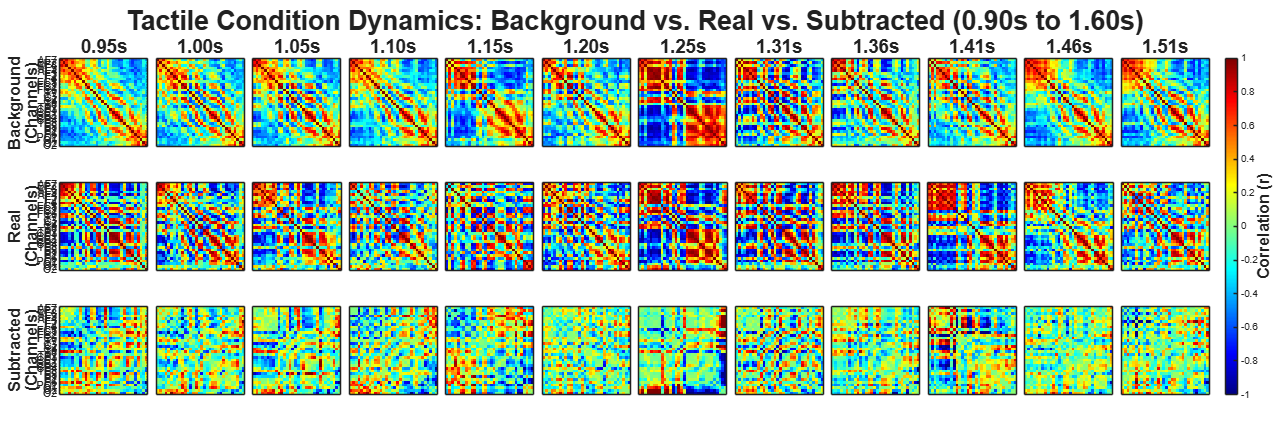


% 1. Setup variables and explicitly define missing parameters
aud_cond = 'BLT'; %'BLA'
ctrl_cond = 'P1'; % Used to generate the null background
t_win_aud = [0.9, 1.6]; % Auditory time window
target_subj = 1; 
n_perms = 1000; 

% Ensure sampling rate is found
if ~exist('fs', 'var')
    if exist('EEG', 'var'), fs = EEG.srate; 
    else, error('Sampling rate (fs) not found in workspace.'); end
end

% Re-define window sizes in case they were cleared
window_size_ms = 100;
step_size_ms = 50;
win_samples = round((window_size_ms / 1000) * fs);
step_samples = round((step_size_ms / 1000) * fs);

if isfield(data_all_conds, aud_cond) && isfield(data_all_conds, ctrl_cond)
    trials_Aud = data_all_conds.(aud_cond){target_subj};
    trials_Ctrl = data_all_conds.(ctrl_cond){target_subj};
    
    % Re-define channel count and labels based on the loaded data
    num_ch = size(trials_Aud, 1);
    if ~exist('all_channels_str', 'var')
        all_channels_str = arrayfun(@(x) sprintf('Ch%d', x), 1:num_ch, 'UniformOutput', false);
    end
    
    nA_aud = size(trials_Aud, 3);
    nB_ctrl = size(trials_Ctrl, 3);
    total_trials_aud = nA_aud + nB_ctrl;
    
    pool_trials_aud = cat(3, trials_Aud, trials_Ctrl);
    
    % 2. Setup Windows
    idx_start_aud = find(time_ms_eeg >= t_win_aud(1), 1, 'first');
    idx_end_aud = find(time_ms_eeg <= t_win_aud(2), 1, 'last');
    
    time_chunk_aud = time_ms_eeg(idx_start_aud:idx_end_aud);
    start_idx_aud = 1 : step_samples : (length(time_chunk_aud) - win_samples + 1);
    num_win_aud = length(start_idx_aud);
    
    % Storage for the 3 rows
    bg_aud_all = nan(num_ch, num_ch, num_win_aud);
    real_aud_all = nan(num_ch, num_ch, num_win_aud);
    sub_aud_all = nan(num_ch, num_ch, num_win_aud);
    win_centers_aud = zeros(1, num_win_aud);
    
    % 3. Calculate Sliding Windows
    for w = 1:num_win_aud
        w_s = idx_start_aud + start_idx_aud(w) - 1;
        w_e = w_s + win_samples - 1;
        win_centers_aud(w) = mean(time_ms_eeg(w_s:w_e));
        
        % A. Real Correlation
        real_corr = corrcoef(mean(trials_Aud(:, w_s:w_e, :), 3, 'omitnan')');
        real_aud_all(:,:,w) = real_corr;
        
        % B. Background Correlation (Permutations)
        null_dist = nan(num_ch, num_ch, n_perms);
        pool_slice = pool_trials_aud(:, w_s:w_e, :);
        
        for prm = 1:n_perms
            shuf_idx = randperm(total_trials_aud);
            idxA = shuf_idx(1:nA_aud);
            pseudo_mean = mean(pool_slice(:,:,idxA), 3, 'omitnan');
            null_dist(:,:,prm) = corrcoef(pseudo_mean');
        end
        
        bg_corr = mean(null_dist, 3, 'omitnan');
        bg_aud_all(:,:,w) = bg_corr;
        
        % C. Subtracted Correlation
        sub_aud_all(:,:,w) = real_corr - bg_corr;
    end
    
    % 4. Plotting the 3-Row Filmstrip
    c_lim_raw = [-1 1];     % Color limits for Background and Real
    c_lim_sub = [-1 1]; % Narrower limits for Subtracted
    
    fig_w_aud = max(1200, 200 * num_win_aud);
    figure('Position', [100, 100, fig_w_aud, 800], 'Name', 'Tactile Condition: Bg vs Real vs Sub');
    tiledlayout(3, num_win_aud, 'TileSpacing', 'compact', 'Padding', 'compact');
    
    % --- ROW 1: BACKGROUND ---
    for w = 1:num_win_aud
        nexttile; imagesc(bg_aud_all(:,:,w));
        colormap('jet'); clim(c_lim_raw); axis square;
        if w == 1
            ylabel(sprintf('Background\n(Channels)'), 'FontSize', 12, 'FontWeight', 'bold');
            yticks(1:num_ch); yticklabels(all_channels_str);
        else yticks([]); end
        xticks([]);
        title(sprintf('%.2fs', win_centers_aud(w)), 'FontSize', 14, 'FontWeight', 'bold');
    end
    
    % --- ROW 2: REAL ---
    for w = 1:num_win_aud
        nexttile; imagesc(real_aud_all(:,:,w));
        colormap('jet'); clim(c_lim_raw); axis square;
        if w == 1
            ylabel(sprintf('Real\n(Channels)'), 'FontSize', 12, 'FontWeight', 'bold');
            yticks(1:num_ch); yticklabels(all_channels_str);
        else yticks([]); end
        xticks([]);
    end
    
    % --- ROW 3: SUBTRACTED ---
    for w = 1:num_win_aud
        nexttile; imagesc(sub_aud_all(:,:,w));
        colormap('jet'); clim(c_lim_sub); axis square;
        if w == 1
            ylabel(sprintf('Subtracted\n(Channels)'), 'FontSize', 12, 'FontWeight', 'bold');
            yticks(1:num_ch); yticklabels(all_channels_str);
        else yticks([]); end
        xticks([]);
    end
    
    % Formatting Master Title and Colorbar
    cb = colorbar;
    cb.Layout.Tile = 'east';
    cb.Label.String = 'Correlation (r)';
    cb.Label.FontSize = 12;
    cb.Label.FontWeight = 'bold';
    
    sgtitle(sprintf('Tactile Condition Dynamics: Background vs. Real vs. Subtracted (%.2fs to %.2fs)', ...
        t_win_aud(1), t_win_aud(2)), 'FontSize', 20, 'FontWeight', 'bold');
else
    warning('Auditory data (BLT) not found in workspace. Cannot generate 3-row plot.');
end

## --- 5. STANDALONE MODULE: TACTILE CONDITION 3-ROW FILMSTRIP --- per trial

% This block runs independently without modifying your previous sections.
% It isolates the Tactile ('BLT') condition and generates a 3-row plot:
% Row 1: Background | Row 2: Real | Row 3: Subtracted

disp('Running standalone 3-row analysis for the Tactile Condition (Single-Trial Connectivity)...');

Running standalone 3-row analysis for the Tactile Condition (Single-Trial Connectivity)...


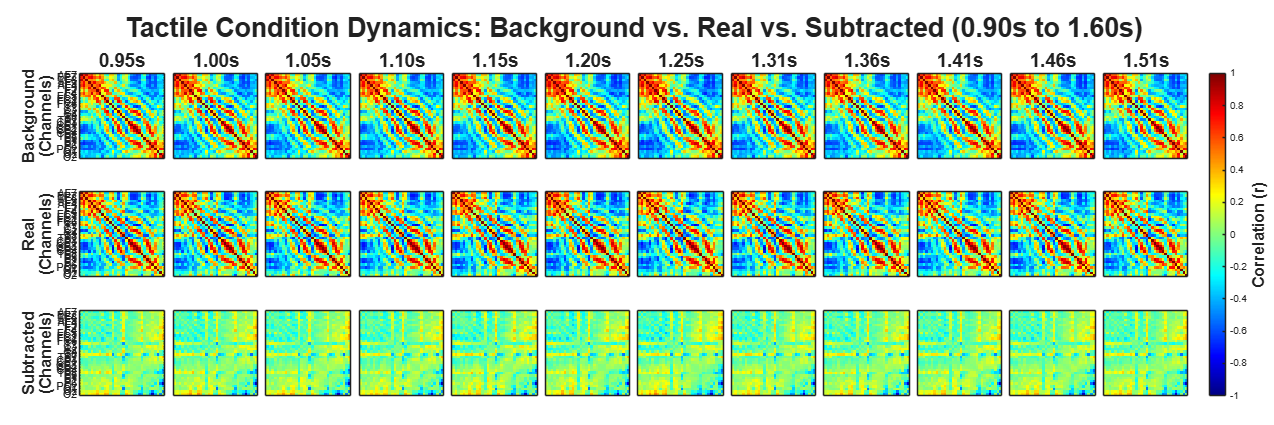


% 1. Setup variables and explicitly define missing parameters
tactile_cond = 'BLT'; 
ctrl_cond = 'P1'; % Used to generate the null background
t_win_tac = [0.9, 1.6]; % Tactile time window
target_subj = 1; 
n_perms = 1000; 

% Ensure sampling rate is found
if ~exist('fs', 'var')
    if exist('EEG', 'var'), fs = EEG.srate; 
    else, error('Sampling rate (fs) not found in workspace.'); end
end

% Re-define window sizes in case they were cleared
window_size_ms = 100;
step_size_ms = 50;
win_samples = round((window_size_ms / 1000) * fs);
step_samples = round((step_size_ms / 1000) * fs);

if isfield(data_all_conds, tactile_cond) && isfield(data_all_conds, ctrl_cond)
    trials_Tac = data_all_conds.(tactile_cond){target_subj};
    trials_Ctrl = data_all_conds.(ctrl_cond){target_subj};
    
    % Re-define channel count and labels based on the loaded data
    num_ch = size(trials_Tac, 1);
    if ~exist('all_channels_str', 'var')
        all_channels_str = arrayfun(@(x) sprintf('Ch%d', x), 1:num_ch, 'UniformOutput', false);
    end
    
    nA_tac = size(trials_Tac, 3);
    nB_ctrl = size(trials_Ctrl, 3);
    total_trials_tac = nA_tac + nB_ctrl;
    
    pool_trials_tac = cat(3, trials_Tac, trials_Ctrl);
    
    % 2. Setup Windows (Keeping time units exactly as requested)
    idx_start_tac = find(time_ms_eeg >= t_win_tac(1), 1, 'first');
    idx_end_tac = find(time_ms_eeg <= t_win_tac(2), 1, 'last');
    
    time_chunk_tac = time_ms_eeg(idx_start_tac:idx_end_tac);
    start_idx_tac = 1 : step_samples : (length(time_chunk_tac) - win_samples + 1);
    num_win_tac = length(start_idx_tac);
    
    % Storage for the 3 rows
    bg_tac_all = nan(num_ch, num_ch, num_win_tac);
    real_tac_all = nan(num_ch, num_ch, num_win_tac);
    sub_tac_all = nan(num_ch, num_ch, num_win_tac);
    win_centers_tac = zeros(1, num_win_tac);
    
    % 3. Calculate Sliding Windows
    for w = 1:num_win_tac
        w_s = idx_start_tac + start_idx_tac(w) - 1;
        w_e = w_s + win_samples - 1;
        win_centers_tac(w) = mean(time_ms_eeg(w_s:w_e));
        
        % Isolate window slice for all pooled trials
        pool_slice = pool_trials_tac(:, w_s:w_e, :);
        
        % Pre-allocate array for SINGLE-TRIAL Z-transformed correlation matrices
        Z_ch_all = nan(num_ch, num_ch, total_trials_tac);
        
        % Calculate single-trial Z-correlations ONCE per window
        for tr = 1:total_trials_tac
            r_ch = corrcoef(pool_slice(:,:,tr)');
            % Set diagonal to 0 to prevent Infinity errors during atanh
            r_ch(1:num_ch+1:num_ch^2) = 0; 
            Z_ch_all(:,:,tr) = atanh(r_ch);
        end
        
        % A. Real Correlation (Average Z-scores, then inverse Fisher)
        real_Z = mean(Z_ch_all(:,:,1:nA_tac), 3, 'omitnan');
        real_corr = tanh(real_Z);
        real_corr(1:num_ch+1:num_ch^2) = 1; % Restore diagonal to 1
        real_tac_all(:,:,w) = real_corr;
        
        % B. Background Correlation (Permutations on Z-scores)
        null_Z_dist = nan(num_ch, num_ch, n_perms);
        
        for prm = 1:n_perms
            shuf_idx = randperm(total_trials_tac);
            idxA = shuf_idx(1:nA_tac);
            
            % Average the Z-matrices for the pseudo-condition
            null_Z_dist(:,:,prm) = mean(Z_ch_all(:,:,idxA), 3, 'omitnan');
        end
        
        % Background = Mean across permutations, then Inverse Fisher (tanh)
        bg_Z = mean(null_Z_dist, 3, 'omitnan');
        bg_corr = tanh(bg_Z);
        bg_corr(1:num_ch+1:num_ch^2) = 1; % Restore diagonal to 1
        bg_tac_all(:,:,w) = bg_corr;
        
        % C. Subtracted Correlation
        sub_tac_all(:,:,w) = real_corr - bg_corr;
    end
    
    % 4. Plotting the 3-Row Filmstrip
    c_lim_raw = [-1 1];     % Color limits for Background and Real
    c_lim_sub = [-1 1];     % Limits for Subtracted
    
    fig_w_tac = max(1200, 200 * num_win_tac);
    figure('Position', [100, 100, fig_w_tac, 800], 'Name', 'Tactile Condition: Bg vs Real vs Sub');
    tiledlayout(3, num_win_tac, 'TileSpacing', 'compact', 'Padding', 'compact');
    
    % --- ROW 1: BACKGROUND ---
    for w = 1:num_win_tac
        nexttile; imagesc(bg_tac_all(:,:,w));
        colormap('jet'); clim(c_lim_raw); axis square;
        if w == 1
            ylabel(sprintf('Background\n(Channels)'), 'FontSize', 12, 'FontWeight', 'bold');
            yticks(1:num_ch); yticklabels(all_channels_str);
        else yticks([]); end
        xticks([]);
        title(sprintf('%.2fs', win_centers_tac(w)), 'FontSize', 14, 'FontWeight', 'bold');
    end
    
    % --- ROW 2: REAL ---
    for w = 1:num_win_tac
        nexttile; imagesc(real_tac_all(:,:,w));
        colormap('jet'); clim(c_lim_raw); axis square;
        if w == 1
            ylabel(sprintf('Real\n(Channels)'), 'FontSize', 12, 'FontWeight', 'bold');
            yticks(1:num_ch); yticklabels(all_channels_str);
        else yticks([]); end
        xticks([]);
    end
    
    % --- ROW 3: SUBTRACTED ---
    for w = 1:num_win_tac
        nexttile; imagesc(sub_tac_all(:,:,w));
        colormap('jet'); clim(c_lim_sub); axis square;
        if w == 1
            ylabel(sprintf('Subtracted\n(Channels)'), 'FontSize', 12, 'FontWeight', 'bold');
            yticks(1:num_ch); yticklabels(all_channels_str);
        else yticks([]); end
        xticks([]);
    end
    
    % Formatting Master Title and Colorbar
    cb = colorbar;
    cb.Layout.Tile = 'east';
    cb.Label.String = 'Correlation (r)';
    cb.Label.FontSize = 12;
    cb.Label.FontWeight = 'bold';
    
    sgtitle(sprintf('Tactile Condition Dynamics: Background vs. Real vs. Subtracted (%.2fs to %.2fs)', ...
        t_win_tac(1), t_win_tac(2)), 'FontSize', 20, 'FontWeight', 'bold');
else
    warning('Tactile data (BLT) or Control data (P1) not found in workspace. Cannot generate 3-row plot.');
end

## Dynamic Pairwise Subtracted Heatmaps (Filmstrip with 1000x Permutation)

disp('Running dPCA and Permutation Subtraction for Sliding Windows...');

Running dPCA and Permutation Subtraction for Sliding Windows...



% Inline helper functions
get_clean_name = @(c) strrep(strrep(strrep(strrep(strrep(strrep(c, ...
    'BLA', 'Auditory'), 'BLT', 'Tactile'), 'P1', 'Cued'), ...
    'P2', 'Unpred.'), 'P3', 'Rand. Cued'), '_', ' ');

% Define your Condition Pairs and their specific time boundaries
pairs = {
    {'BLA', 'P1', [0.4, 0.9]},
    {'BLT', 'P1', [0.9, 1.4]},
    {'P1', 'P2_500', [0.9, 1.4]},
    {'P1', 'P2_2000', [2.4, 2.9]},
    {'P1', 'P3_500', [0.9, 1.4]},
    {'P1', 'P3_missing', [0.9, 1.4]}
};

target_subj = 1; % Analyzing Subject 1
if isempty(fs), fs = EEG.srate; end % Fallback for sampling rate
n_perms = 1000; % Number of shuffles for the background subtraction

% Sliding window configuration
window_size_ms = 100;
step_size_ms = 50;
win_samples = round((window_size_ms / 1000) * fs);
step_samples = round((step_size_ms / 1000) * fs);

if ~exist('all_channels_str', 'var')
    all_channels_str = arrayfun(@(x) sprintf('Ch%d', x), 1:num_ch, 'UniformOutput', false);
end

for p = 1:length(pairs)
    condA = pairs{p}{1};
    condB = pairs{p}{2};
    t_win = pairs{p}{3};
    cleanA = get_clean_name(condA);
    cleanB = get_clean_name(condB);
    
    if ~isfield(data_all_conds, condA) || ~isfield(data_all_conds, condB)
        warning('Skipping pair %s vs %s (Missing data)', cleanA, cleanB);
        continue;
    end
    
    % Extract FULL Single Trials [Channels x Time x Trials]
    trialsA = data_all_conds.(condA){target_subj};
    trialsB = data_all_conds.(condB){target_subj};
    
    nA = size(trialsA, 3);
    nB = size(trialsB, 3);
    total_trials = nA + nB;
    
    if nA == 0 || nB == 0, continue; end
    
    % Trial Averages for DR [Channels x Time]
    avgA = mean(trialsA, 3, 'omitnan');
    avgB = mean(trialsB, 3, 'omitnan');
    
    %% --- 1. DIMENSIONALITY REDUCTION (GLOBAL MANIFOLD) ---
    data_combined = [avgA, avgB];
    data_combined_centered = data_combined - mean(data_combined, 2);
    
    [k_opt, ~] = velicer_map(data_combined_centered', true);
    if k_opt < 2, k_opt = 2; end 
    
    try
        X_dpca = cat(3, avgA, avgB); 
        X_dpca_centered = bsxfun(@minus, X_dpca, mean(X_dpca(:,:), 2));
        [W_dpca, ~, ~] = dpca(X_dpca_centered, k_opt); 
        W = W_dpca'; % Transpose to [k x Channels]
    catch 
        [~, ~, V] = svd(data_combined_centered', 'econ');
        W = V(:, 1:k_opt)'; 
    end
    
    %% --- 2. PROJECT ALL SINGLE TRIALS INTO dPC SPACE ---
    % Flatten, project, and reshape back to [k x Time x Trials] for fast processing
    T_len = size(trialsA, 2);
    
    trialsA_flat = reshape(trialsA, num_ch, []);
    compA_flat = W * (trialsA_flat - mean(trialsA_flat, 2));
    comp_trialsA = reshape(compA_flat, k_opt, T_len, nA);
    
    trialsB_flat = reshape(trialsB, num_ch, []);
    compB_flat = W * (trialsB_flat - mean(trialsB_flat, 2));
    comp_trialsB = reshape(compB_flat, k_opt, T_len, nB);
    
    % Pool trials together for the shuffler
    pool_trials_ch = cat(3, trialsA, trialsB);
    pool_trials_pc = cat(3, comp_trialsA, comp_trialsB);
    
    %% --- 3. SLIDING WINDOW & PERMUTATION SUBTRACTION ---
    idx_start = find(time_ms_eeg >= t_win(1), 1, 'first');
    idx_end = find(time_ms_eeg <= t_win(2), 1, 'last');
    
    time_chunk = time_ms_eeg(idx_start:idx_end);
    num_chunk_points = length(time_chunk);
    
    start_idx = 1 : step_samples : (num_chunk_points - win_samples + 1);
    num_windows = length(start_idx);
    
    % Storage for Subtracted Matrices
    sub_ch_A_all = nan(num_ch, num_ch, num_windows);
    sub_ch_B_all = nan(num_ch, num_ch, num_windows);
    sub_pc_A_all = nan(k_opt, k_opt, num_windows);
    sub_pc_B_all = nan(k_opt, k_opt, num_windows);
    
    window_centers = zeros(1, num_windows);
    
    fprintf('Processing %s vs %s: %d Windows x %d Shuffles...\n', cleanA, cleanB, num_windows, n_perms);
    
    for w = 1:num_windows
        % Global indices for this window
        w_s = idx_start + start_idx(w) - 1;
        w_e = w_s + win_samples - 1;
        
        window_centers(w) = mean(time_ms_eeg(w_s:w_e));
        
        % A. Calculate REAL correlation for this window
        real_ch_A = corrcoef(mean(trialsA(:, w_s:w_e, :), 3, 'omitnan')');
        real_ch_B = corrcoef(mean(trialsB(:, w_s:w_e, :), 3, 'omitnan')');
        real_pc_A = corrcoef(mean(comp_trialsA(:, w_s:w_e, :), 3, 'omitnan')');
        real_pc_B = corrcoef(mean(comp_trialsB(:, w_s:w_e, :), 3, 'omitnan')');
        
        % B. Calculate BACKGROUND correlation via Permutation
        null_ch_A = nan(num_ch, num_ch, n_perms); null_ch_B = nan(num_ch, num_ch, n_perms);
        null_pc_A = nan(k_opt, k_opt, n_perms);   null_pc_B = nan(k_opt, k_opt, n_perms);
        
        % Isolate the specific time slice from the pooled data to speed up the loop
        pool_ch_slice = pool_trials_ch(:, w_s:w_e, :);
        pool_pc_slice = pool_trials_pc(:, w_s:w_e, :);
        
        for prm = 1:n_perms
            shuf_idx = randperm(total_trials);
            idxA = shuf_idx(1:nA);
            idxB = shuf_idx(nA+1:end);
            
            % Pseudo Means
            pseudo_ch_A = mean(pool_ch_slice(:,:,idxA), 3, 'omitnan');
            pseudo_ch_B = mean(pool_ch_slice(:,:,idxB), 3, 'omitnan');
            pseudo_pc_A = mean(pool_pc_slice(:,:,idxA), 3, 'omitnan');
            pseudo_pc_B = mean(pool_pc_slice(:,:,idxB), 3, 'omitnan');
            
            % Pseudo Correlations
            null_ch_A(:,:,prm) = corrcoef(pseudo_ch_A'); null_ch_B(:,:,prm) = corrcoef(pseudo_ch_B');
            null_pc_A(:,:,prm) = corrcoef(pseudo_pc_A'); null_pc_B(:,:,prm) = corrcoef(pseudo_pc_B');
        end
        
        % Mean Backgrounds
        bg_ch_A = mean(null_ch_A, 3, 'omitnan'); bg_ch_B = mean(null_ch_B, 3, 'omitnan');
        bg_pc_A = mean(null_pc_A, 3, 'omitnan'); bg_pc_B = mean(null_pc_B, 3, 'omitnan');
        
        % C. SUBTRACT to isolate Condition-Specific Network
        sub_ch_A_all(:,:,w) = real_ch_A - bg_ch_A;
        sub_ch_B_all(:,:,w) = real_ch_B - bg_ch_B;
        sub_pc_A_all(:,:,w) = real_pc_A - bg_pc_A;
        sub_pc_B_all(:,:,w) = real_pc_B - bg_pc_B;
    end
    
    %% --- 4. PLOTTING SUBTRACTED FILMSTRIP SNAPSHOTS ---
    c_lim = [-0.5 0.5]; % Narrowed colormap limits for subtracted data
    
    fig_width = max(1200, 200 * num_windows);
    fig = figure('Position', [50, 50, fig_width, 900], 'Name', sprintf('%s vs %s Filmstrip', cleanA, cleanB));
    tiledlayout(4, num_windows, 'TileSpacing', 'compact', 'Padding', 'compact');
    
    pc_labels = arrayfun(@(x) sprintf('dPC%d', x), 1:k_opt, 'UniformOutput', false);
    
    % ROW 1: Subtracted Condition A (Channels)
    for w = 1:num_windows
        nexttile; imagesc(sub_ch_A_all(:,:,w));
        colormap('jet'); clim(c_lim); axis square;
        if w == 1
            ylabel(sprintf('%s\n(Channels)', cleanA), 'FontSize', 12, 'FontWeight', 'bold');
            yticks(1:num_ch); yticklabels(all_channels_str);
        else yticks([]); end
        xticks([]);
        title(sprintf('%.2fs', window_centers(w)), 'FontSize', 14, 'FontWeight', 'bold');
    end
    
    % ROW 2: Subtracted Condition B (Channels)
    for w = 1:num_windows
        nexttile; imagesc(sub_ch_B_all(:,:,w));
        colormap('jet'); clim(c_lim); axis square;
        if w == 1
            ylabel(sprintf('%s\n(Channels)', cleanB), 'FontSize', 12, 'FontWeight', 'bold');
            yticks(1:num_ch); yticklabels(all_channels_str);
        else yticks([]); end
        xticks([]);
    end
    
    % ROW 3: Subtracted Condition A (Latent PCs)
    for w = 1:num_windows
        nexttile; imagesc(sub_pc_A_all(:,:,w));
        colormap('jet'); clim(c_lim); axis square;
        if w == 1
            ylabel(sprintf('%s\n(Shared dPCs)', cleanA), 'FontSize', 12, 'FontWeight', 'bold');
            yticks(1:k_opt); yticklabels(pc_labels);
        else yticks([]); end
        xticks([]);
    end
    
    % ROW 4: Subtracted Condition B (Latent PCs)
    for w = 1:num_windows
        nexttile; imagesc(sub_pc_B_all(:,:,w));
        colormap('jet'); clim(c_lim); axis square;
        if w == 1
            ylabel(sprintf('%s\n(Shared dPCs)', cleanB), 'FontSize', 12, 'FontWeight', 'bold');
            yticks(1:k_opt); yticklabels(pc_labels);
        else yticks([]); end
        xticks(1:k_opt); xticklabels(pc_labels); xtickangle(45);
    end
    
    % Master formatting
    cb = colorbar;
    cb.Layout.Tile = 'east';
    cb.Label.String = 'Subtracted Correlation (\Delta r)';
    cb.Label.FontSize = 12;
    cb.Label.FontWeight = 'bold';
    
    sgtitle(sprintf('Isolated Condition-Specific Networks: %s vs %s (%.2fs to %.2fs)', ...
        cleanA, cleanB, t_win(1), t_win(2)), 'FontSize', 20, 'FontWeight', 'bold');
end

Matrix close to singular, using tiny regularization, lambda = 1e-10


Processing Auditory vs Cued: 8 Windows x 1000 Shuffles...


Matrix close to singular, using tiny regularization, lambda = 1e-10


Processing Tactile vs Cued: 8 Windows x 1000 Shuffles...


Matrix close to singular, using tiny regularization, lambda = 1e-10


Processing Cued vs Unpred. 500: 8 Windows x 1000 Shuffles...


Matrix close to singular, using tiny regularization, lambda = 1e-10


Processing Cued vs Unpred. 2000: 8 Windows x 1000 Shuffles...


Matrix close to singular, using tiny regularization, lambda = 1e-10


Processing Cued vs Rand. Cued 500: 8 Windows x 1000 Shuffles...


Matrix close to singular, using tiny regularization, lambda = 1e-10


Processing Cued vs Rand. Cued missing: 8 Windows x 1000 Shuffles...



disp('Subtracted Filmstrip Heatmaps generated successfully.');

Subtracted Filmstrip Heatmaps generated successfully.


## DIAGNOSTIC: Time-Domain & PSD for Suspect Channels

%% DIAGNOSTIC: Time-Domain & PSD for Suspect Channels (Log-Log Scale)
disp('Running Spectral & Time-Domain Diagnostic on Suspect Channels...');

Running Spectral & Time-Domain Diagnostic on Suspect Channels...


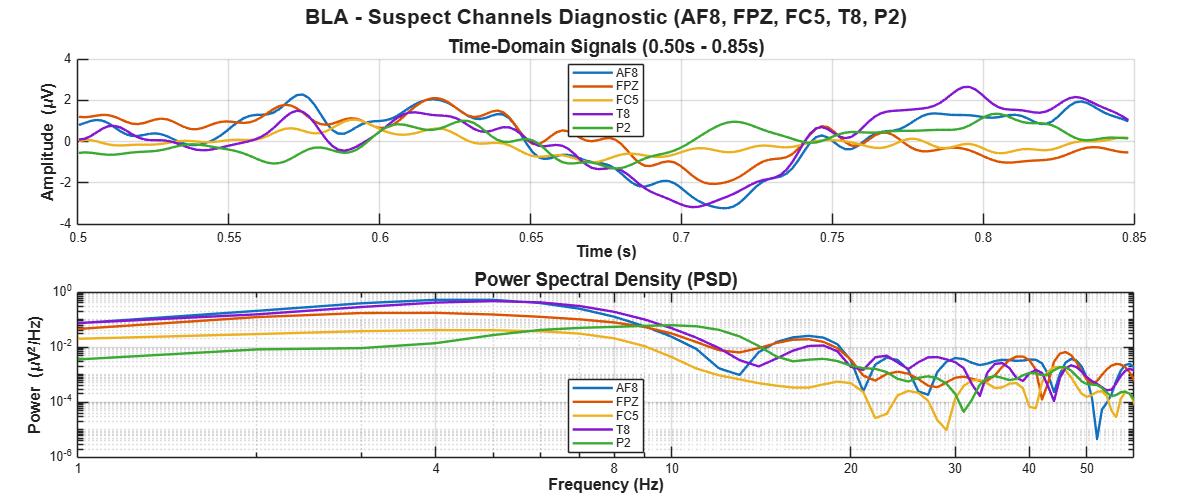


suspect_channels = {'AF8', 'FPZ', 'FC5', 'T8', 'P2'}; % Channel list
target_cond = 'BLA'; % Condition where you saw the stripes
target_subj = 1;

% Isolate the specific noisy time window
t_start = 0.5;
t_end = 0.85;
idx_start = find(time_ms_eeg >= t_start, 1, 'first');
idx_end = find(time_ms_eeg <= t_end, 1, 'last');

% Extract time vector and trial-averaged data for that window
t_vec = time_ms_eeg(idx_start:idx_end);
raw_data = data_subj_avg.(target_cond)(:, idx_start:idx_end, target_subj);

% Find indices of suspect channels
[~, chan_idx] = ismember(suspect_channels, all_channels_str);
chan_idx = unique(chan_idx(chan_idx > 0), 'stable'); % Ensure unique channel indices
valid_channels = all_channels_str(chan_idx);

% Create Figure with 1x2 Tiled Layout
fig_diag = figure('Position', [100, 100, 1200, 500], 'Name', 'Noise Diagnostic: Time & Frequency');
tiledlayout(2, 1, 'TileSpacing', 'compact', 'Padding', 'compact');

% Color palette for consistent channel colors across both subplots
colors = lines(length(chan_idx));

% --- SUBPLOT 1: Time Domain Signal Traces ---
nexttile; hold on;
for i = 1:length(chan_idx)
    ch_data = raw_data(chan_idx(i), :);
    plot(t_vec, ch_data, 'LineWidth', 1.8, 'Color', colors(i,:), 'DisplayName', valid_channels{i});
end
xlabel('Time (s)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Amplitude (\muV)', 'FontSize', 12, 'FontWeight', 'bold');
title(sprintf('Time-Domain Signals (%.2fs - %.2fs)', t_start, t_end), 'FontSize', 14, 'FontWeight', 'bold');
legend('Location', 'best', 'FontSize', 9);
grid on; hold off;

% --- SUBPLOT 2: Power Spectral Density (PSD - Log-Log Scale) ---
nexttile;
for i = 1:length(chan_idx)
    ch_data = raw_data(chan_idx(i), :);
    
    % Compute PSD via Welch's method
    [pxx, f] = pwelch(ch_data, length(ch_data), 0, 512, fs);
    
    % Plot raw power on a log-log scale
    loglog(f, pxx, 'LineWidth', 1.8, 'Color', colors(i,:), 'DisplayName', valid_channels{i});
    hold on;
end

% Set specific frequency limits and custom tick locations
xlim([1 60]); 
xticks([1 4 8 10 20 30 40 50]);
xticklabels({'1', '4','8', '10', '20', '30', '40', '50'});

xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Power (\muV^2/Hz)', 'FontSize', 12, 'FontWeight', 'bold');
title('Power Spectral Density (PSD)', 'FontSize', 14, 'FontWeight', 'bold');
legend('Location', 'best', 'FontSize', 9);
grid on; hold off;

% Master Title
sgtitle(sprintf('%s - Suspect Channels Diagnostic (%s)', target_cond, strjoin(valid_channels, ', ')), ...
    'FontSize', 16, 'FontWeight', 'bold');

## Dynamic Pairwise Subtracted trial-averaged functional connectivity Heatmaps (Filmstrip with 1000x Permutation) with time unit and Fisher Z-transform update

disp('Running dPCA and Permutation Subtraction for Sliding Windows...');

Running dPCA and Permutation Subtraction for Sliding Windows...



% Inline helper functions
get_clean_name = @(c) strrep(strrep(strrep(strrep(strrep(strrep(c, ...
    'BLA', 'Auditory'), 'BLT', 'Tactile'), 'P1', 'Cued'), ...
    'P2', 'Unpred.'), 'P3', 'Rand. Cued'), '_', ' ');

% Define your Condition Pairs and their specific time boundaries
pairs = {
    {'BLA', 'P1', [0.4, 0.9]},
    {'BLT', 'P1', [0.9, 1.5]},
    {'P1', 'P2_500', [0.9, 1.5]},
    {'P1', 'P2_2000', [2.4, 3]},
    {'P1', 'P3_500', [0.9, 1.5]},
    {'P1', 'P3_missing', [0.9, 1.5]}
};

target_subj = 1; % Analyzing Subject 1

% Safe check for sampling rate
if ~exist('fs', 'var') || isempty(fs)
    if exist('EEG', 'var'), fs = EEG.srate; 
    else, error('Sampling rate (fs) not found.'); end
end

n_perms = 1000; % Number of shuffles for the background subtraction

% Sliding window configuration
window_size_ms = 100;
step_size_ms = 50;
win_samples = round((window_size_ms / 1000) * fs);
step_samples = round((step_size_ms / 1000) * fs);

if ~exist('all_channels_str', 'var')
    all_channels_str = arrayfun(@(x) sprintf('Ch%d', x), 1:num_ch, 'UniformOutput', false);
end

for p = 1:length(pairs)
    condA = pairs{p}{1};
    condB = pairs{p}{2};
    t_win = pairs{p}{3};
    cleanA = get_clean_name(condA);
    cleanB = get_clean_name(condB);
    
    % Dynamic Y-Axis Limits Logic
    if strcmp(condA, 'BLA') && strcmp(condB, 'P1')
        ch_ylim = [-10, 10];
        pc_ylim = [-25, 25];
    else
        ch_ylim = [-5, 5];
        pc_ylim = [-15, 15];
    end
    
    if ~isfield(data_all_conds, condA) || ~isfield(data_all_conds, condB)
        warning('Skipping pair %s vs %s (Missing data)', cleanA, cleanB);
        continue;
    end
    
    % Extract FULL Single Trials [Channels x Time x Trials]
    trialsA = data_all_conds.(condA){target_subj};
    trialsB = data_all_conds.(condB){target_subj};
    
    nA = size(trialsA, 3);
    nB = size(trialsB, 3);
    total_trials = nA + nB;
    
    if nA == 0 || nB == 0, continue; end
    
    % Trial Averages for DR [Channels x Time]
    avgA = mean(trialsA, 3, 'omitnan');
    avgB = mean(trialsB, 3, 'omitnan');
    
    %% --- 1. DIMENSIONALITY REDUCTION (GLOBAL MANIFOLD) ---
    data_combined = [avgA, avgB];
    data_combined_centered = data_combined - mean(data_combined, 2);
    
    [k_opt, ~] = velicer_map(data_combined_centered', true);
    if k_opt < 2, k_opt = 2; end 
    
    try
        X_dpca = cat(3, avgA, avgB); 
        X_dpca_centered = bsxfun(@minus, X_dpca, mean(X_dpca(:,:), 2));
        [W_dpca, ~, ~] = dpca(X_dpca_centered, k_opt); 
        W = W_dpca'; % Transpose to [k x Channels]
    catch 
        [~, ~, V] = svd(data_combined_centered', 'econ');
        W = V(:, 1:k_opt)'; 
    end
    
    %% --- 2. PROJECT ALL SINGLE TRIALS INTO dPC SPACE ---
    T_len = size(trialsA, 2);
    num_ch = size(trialsA, 1);
    
    trialsA_flat = reshape(trialsA, num_ch, []);
    compA_flat = W * (trialsA_flat - mean(trialsA_flat, 2));
    comp_trialsA = reshape(compA_flat, k_opt, T_len, nA);
    
    trialsB_flat = reshape(trialsB, num_ch, []);
    compB_flat = W * (trialsB_flat - mean(trialsB_flat, 2));
    comp_trialsB = reshape(compB_flat, k_opt, T_len, nB);
    
    % Pool trials together for the shuffler
    pool_trials_ch = cat(3, trialsA, trialsB);
    pool_trials_pc = cat(3, comp_trialsA, comp_trialsB);
    
    %% --- 3. SLIDING WINDOW & PERMUTATION SUBTRACTION ---
    idx_start = find(time_ms_eeg >= t_win(1), 1, 'first');
    idx_end = find(time_ms_eeg <= t_win(2), 1, 'last');
    
    time_chunk = time_ms_eeg(idx_start:idx_end);
    num_chunk_points = length(time_chunk);
    
    start_idx = 1 : step_samples : (num_chunk_points - win_samples + 1);
    num_windows = length(start_idx);
    
    % Storage for Subtracted Matrices
    sub_ch_A_all = nan(num_ch, num_ch, num_windows);
    sub_ch_B_all = nan(num_ch, num_ch, num_windows);
    sub_pc_A_all = nan(k_opt, k_opt, num_windows);
    sub_pc_B_all = nan(k_opt, k_opt, num_windows);
    
    window_centers = zeros(1, num_windows);
    
    fprintf('Processing %s vs %s: %d Windows x %d Shuffles...\n', cleanA, cleanB, num_windows, n_perms);
    
    for w = 1:num_windows
        % Global indices for this window
        w_s = idx_start + start_idx(w) - 1;
        w_e = w_s + win_samples - 1;
        
        window_centers(w) = mean(time_ms_eeg(w_s:w_e));
        
        % A. Calculate REAL correlation for this window (Trial-Averaged ERP)
        real_ch_A = corrcoef(mean(trialsA(:, w_s:w_e, :), 3, 'omitnan')');
        real_ch_B = corrcoef(mean(trialsB(:, w_s:w_e, :), 3, 'omitnan')');
        real_pc_A = corrcoef(mean(comp_trialsA(:, w_s:w_e, :), 3, 'omitnan')');
        real_pc_B = corrcoef(mean(comp_trialsB(:, w_s:w_e, :), 3, 'omitnan')');
        
        % B. Calculate BACKGROUND correlation via Permutation
        null_ch_A = nan(num_ch, num_ch, n_perms); null_ch_B = nan(num_ch, num_ch, n_perms);
        null_pc_A = nan(k_opt, k_opt, n_perms);   null_pc_B = nan(k_opt, k_opt, n_perms);
        
        pool_ch_slice = pool_trials_ch(:, w_s:w_e, :);
        pool_pc_slice = pool_trials_pc(:, w_s:w_e, :);
        
        for prm = 1:n_perms
            shuf_idx = randperm(total_trials);
            idxA = shuf_idx(1:nA);
            idxB = shuf_idx(nA+1:end);
            
            pseudo_ch_A = mean(pool_ch_slice(:,:,idxA), 3, 'omitnan');
            pseudo_ch_B = mean(pool_ch_slice(:,:,idxB), 3, 'omitnan');
            pseudo_pc_A = mean(pool_pc_slice(:,:,idxA), 3, 'omitnan');
            pseudo_pc_B = mean(pool_pc_slice(:,:,idxB), 3, 'omitnan');
            
            % Zero diagonal before atanh to avoid Infinity
            null_ch_A(:,:,prm) = atanh(corrcoef(pseudo_ch_A') .* ~eye(num_ch)); 
            null_ch_B(:,:,prm) = atanh(corrcoef(pseudo_ch_B') .* ~eye(num_ch));
            null_pc_A(:,:,prm) = atanh(corrcoef(pseudo_pc_A') .* ~eye(k_opt)); 
            null_pc_B(:,:,prm) = atanh(corrcoef(pseudo_pc_B') .* ~eye(k_opt));
        end
        
        bg_ch_A = tanh(mean(null_ch_A, 3, 'omitnan')); bg_ch_A(1:num_ch+1:end) = 1; 
        bg_ch_B = tanh(mean(null_ch_B, 3, 'omitnan')); bg_ch_B(1:num_ch+1:end) = 1;
        
        bg_pc_A = tanh(mean(null_pc_A, 3, 'omitnan')); bg_pc_A(1:k_opt+1:end) = 1; 
        bg_pc_B = tanh(mean(null_pc_B, 3, 'omitnan')); bg_pc_B(1:k_opt+1:end) = 1;
        
        % C. SUBTRACT to isolate Condition-Specific Network
        sub_ch_A_all(:,:,w) = real_ch_A - bg_ch_A;
        sub_ch_B_all(:,:,w) = real_ch_B - bg_ch_B;
        sub_pc_A_all(:,:,w) = real_pc_A - bg_pc_A;
        sub_pc_B_all(:,:,w) = real_pc_B - bg_pc_B;
    end
    
    %% --- 4. PLOTTING SUBTRACTED FILMSTRIP MATRICES ---
    c_lim = [-1 1]; 
    fig_width = max(1200, 200 * num_windows);
    
    fig1 = figure('Position', [50, 50, fig_width, 900], 'Name', sprintf('%s vs %s Matrices', cleanA, cleanB));
    tiledlayout(4, num_windows, 'TileSpacing', 'compact', 'Padding', 'compact');
    pc_labels = arrayfun(@(x) sprintf('dPC%d', x), 1:k_opt, 'UniformOutput', false);
    
    % ROW 1: Subtracted Condition A (Channels)
    for w = 1:num_windows
        nexttile; imagesc(sub_ch_A_all(:,:,w));
        colormap('jet'); clim(c_lim); axis square;
        if w == 1
            ylabel(sprintf('%s\n(Channels)', cleanA), 'FontSize', 12, 'FontWeight', 'bold');
            yticks(1:num_ch); yticklabels(all_channels_str);
        else yticks([]); end
        xticks([]);
        title(sprintf('%.2fs', window_centers(w)), 'FontSize', 14, 'FontWeight', 'bold');
    end
    
    % ROW 2: Subtracted Condition B (Channels)
    for w = 1:num_windows
        nexttile; imagesc(sub_ch_B_all(:,:,w));
        colormap('jet'); clim(c_lim); axis square;
        if w == 1
            ylabel(sprintf('%s\n(Channels)', cleanB), 'FontSize', 12, 'FontWeight', 'bold');
            yticks(1:num_ch); yticklabels(all_channels_str);
        else yticks([]); end
        xticks([]);
    end
    
    % ROW 3: Subtracted Condition A (Latent PCs)
    for w = 1:num_windows
        nexttile; imagesc(sub_pc_A_all(:,:,w));
        colormap('jet'); clim(c_lim); axis square;
        if w == 1
            ylabel(sprintf('%s\n(Shared dPCs)', cleanA), 'FontSize', 12, 'FontWeight', 'bold');
            yticks(1:k_opt); yticklabels(pc_labels);
        else yticks([]); end
        xticks([]);
    end
    
    % ROW 4: Subtracted Condition B (Latent PCs)
    for w = 1:num_windows
        nexttile; imagesc(sub_pc_B_all(:,:,w));
        colormap('jet'); clim(c_lim); axis square;
        if w == 1
            ylabel(sprintf('%s\n(Shared dPCs)', cleanB), 'FontSize', 12, 'FontWeight', 'bold');
            yticks(1:k_opt); yticklabels(pc_labels);
        else yticks([]); end
        xticks(1:k_opt); xticklabels(pc_labels); xtickangle(45);
    end
    
    cb = colorbar;
    cb.Layout.Tile = 'east';
    cb.Label.String = 'Subtracted Correlation (\Delta r)';
    cb.Label.FontSize = 12;
    cb.Label.FontWeight = 'bold';
    sgtitle(sprintf('Isolated Condition-Specific Networks: %s vs %s', cleanA, cleanB), 'FontSize', 20, 'FontWeight', 'bold');


    %% --- 5. PLOTTING FILTERED TRACES (Shared Legends on Row 2 & 4 & Locked Amplitudes) ---
    corr_thresh = 0.5;
    
    % Define consistent color maps for channels and PCs
    ch_colors = hsv(num_ch);
    pc_colors = lines(k_opt);
    
    % Helper function: Zeros out the diagonal and finds components that cross the threshold
    get_high_corr_idx = @(mat, thresh) find(any(abs(mat - diag(diag(mat))) > thresh, 2));
    
    fig2 = figure('Position', [100, 100, fig_width, 900], 'Name', sprintf('%s vs %s Traces (>%g Corr)', cleanA, cleanB, corr_thresh));
    tiledlayout(4, num_windows, 'TileSpacing', 'compact', 'Padding', 'compact');
    
    % Collect active indices for channels (Row 1 + Row 2) and PCs (Row 3 + Row 4)
    active_row1 = []; active_row2 = [];
    active_row3 = []; active_row4 = [];
    for w = 1:num_windows
        active_row1 = union(active_row1, get_high_corr_idx(sub_ch_A_all(:,:,w), corr_thresh)); 
        active_row2 = union(active_row2, get_high_corr_idx(sub_ch_B_all(:,:,w), corr_thresh));
        active_row3 = union(active_row3, get_high_corr_idx(sub_pc_A_all(:,:,w), corr_thresh)); 
        active_row4 = union(active_row4, get_high_corr_idx(sub_pc_B_all(:,:,w), corr_thresh));
    end
    
    % Master unified lists
    active_channels = union(active_row1, active_row2);
    active_pcs = union(active_row3, active_row4);
    
    % --- ROW 1: Cond A Channels ---
    for w = 1:num_windows
        nexttile; hold on;
        w_s = idx_start + start_idx(w) - 1; w_e = w_s + win_samples - 1;
        t_axis = time_ms_eeg(w_s:w_e);
        
        idx = get_high_corr_idx(sub_ch_A_all(:,:,w), corr_thresh);
        if ~isempty(idx)
            for i = 1:length(idx)
                curr_idx = idx(i);
                plot(t_axis, mean(trialsA(curr_idx, w_s:w_e, :), 3, 'omitnan'), ...
                    'LineWidth', 1.2, 'Color', ch_colors(curr_idx, :));
            end
        else
            text(mean(t_axis), 0, sprintf('None > %g', corr_thresh), ...
                'HorizontalAlignment', 'center', 'Color', [0.5 0.5 0.5]);
        end
        xlim([t_axis(1), t_axis(end)]);
        ylim(ch_ylim); % Dynamically Locked Channel Amplitude
        set(gca, 'XColor', 'none'); 
        
        if w == 1, ylabel(sprintf('%s\nCh Traces', cleanA), 'FontWeight', 'bold'); end
        title(sprintf('%.2fs', window_centers(w)), 'FontSize', 12, 'FontWeight', 'bold');
        % No legend generated here
    end
    
    % --- ROW 2: Cond B Channels ---
    for w = 1:num_windows
        nexttile; hold on;
        w_s = idx_start + start_idx(w) - 1; w_e = w_s + win_samples - 1;
        t_axis = time_ms_eeg(w_s:w_e);
        
        idx = get_high_corr_idx(sub_ch_B_all(:,:,w), corr_thresh);
        if ~isempty(idx)
            for i = 1:length(idx)
                curr_idx = idx(i);
                plot(t_axis, mean(trialsB(curr_idx, w_s:w_e, :), 3, 'omitnan'), ...
                    'LineWidth', 1.2, 'Color', ch_colors(curr_idx, :));
            end
        else
            text(mean(t_axis), 0, sprintf('None > %g', corr_thresh), ...
                'HorizontalAlignment', 'center', 'Color', [0.5 0.5 0.5]);
        end
        xlim([t_axis(1), t_axis(end)]);
        ylim(ch_ylim); % Dynamically Locked Channel Amplitude
        set(gca, 'XColor', 'none'); 
        if w == 1, ylabel(sprintf('%s\nCh Traces', cleanB), 'FontWeight', 'bold'); end
        
        % Attach the single Master Legend for Channels on the very last subplot of Row 2
        if w == num_windows && ~isempty(active_channels)
            h_leg = zeros(length(active_channels), 1);
            for i = 1:length(active_channels)
                curr_idx = active_channels(i);
                h_leg(i) = plot(nan, nan, 'LineWidth', 1.5, 'Color', ch_colors(curr_idx, :));
            end
            lgd = legend(h_leg, all_channels_str(active_channels), 'Location', 'eastoutside', 'FontSize', 8, 'AutoUpdate', 'off');
            lgd.ItemTokenSize = [12, 12];
        end
    end
    
    % --- ROW 3: Cond A dPCs ---
    for w = 1:num_windows
        nexttile; hold on;
        w_s = idx_start + start_idx(w) - 1; w_e = w_s + win_samples - 1;
        t_axis = time_ms_eeg(w_s:w_e);
        
        idx = get_high_corr_idx(sub_pc_A_all(:,:,w), corr_thresh);
        if ~isempty(idx)
            for i = 1:length(idx)
                curr_idx = idx(i);
                plot(t_axis, mean(comp_trialsA(curr_idx, w_s:w_e, :), 3, 'omitnan'), ...
                    'LineWidth', 1.2, 'Color', pc_colors(curr_idx, :));
            end
        else
            text(mean(t_axis), 0, sprintf('None > %g', corr_thresh), ...
                'HorizontalAlignment', 'center', 'Color', [0.5 0.5 0.5]);
        end
        xlim([t_axis(1), t_axis(end)]);
        ylim(pc_ylim); % Dynamically Locked dPC Amplitude
        set(gca, 'XColor', 'none'); 
        if w == 1, ylabel(sprintf('%s\ndPC Traces', cleanA), 'FontWeight', 'bold'); end
        % No legend generated here
    end
    
    % --- ROW 4: Cond B dPCs ---
    for w = 1:num_windows
        nexttile; hold on;
        w_s = idx_start + start_idx(w) - 1; w_e = w_s + win_samples - 1;
        t_axis = time_ms_eeg(w_s:w_e);
        
        idx = get_high_corr_idx(sub_pc_B_all(:,:,w), corr_thresh);
        if ~isempty(idx)
            for i = 1:length(idx)
                curr_idx = idx(i);
                plot(t_axis, mean(comp_trialsB(curr_idx, w_s:w_e, :), 3, 'omitnan'), ...
                    'LineWidth', 1.2, 'Color', pc_colors(curr_idx, :));
            end
        else
            text(mean(t_axis), 0, sprintf('None > %g', corr_thresh), ...
                'HorizontalAlignment', 'center', 'Color', [0.5 0.5 0.5]);
        end
        xlim([t_axis(1), t_axis(end)]);
        ylim(pc_ylim); % Dynamically Locked dPC Amplitude
        
        if w == 1, ylabel(sprintf('%s\ndPC Traces', cleanB), 'FontWeight', 'bold'); end
        xlabel('Time');
        
        % Attach the single Master Legend for PCs on the very last subplot of Row 4
        if w == num_windows && ~isempty(active_pcs)
            h_leg = zeros(length(active_pcs), 1);
            for i = 1:length(active_pcs)
                curr_idx = active_pcs(i);
                h_leg(i) = plot(nan, nan, 'LineWidth', 1.5, 'Color', pc_colors(curr_idx, :));
            end
            lgd = legend(h_leg, pc_labels(active_pcs), 'Location', 'eastoutside', 'FontSize', 8, 'AutoUpdate', 'off');
            lgd.ItemTokenSize = [12, 12];
        end
    end
    
    sgtitle(sprintf('Evoked Traces Filtering for Absolute \\Delta r > %g: %s vs %s', ...
        corr_thresh, cleanA, cleanB), 'FontSize', 18, 'FontWeight', 'bold');
end

Matrix close to singular, using tiny regularization, lambda = 1e-10


Processing Auditory vs Cued: 8 Windows x 1000 Shuffles...


Matrix close to singular, using tiny regularization, lambda = 1e-10


Processing Tactile vs Cued: 10 Windows x 1000 Shuffles...


Matrix close to singular, using tiny regularization, lambda = 1e-10


Processing Cued vs Unpred. 500: 10 Windows x 1000 Shuffles...


Matrix close to singular, using tiny regularization, lambda = 1e-10


Processing Cued vs Unpred. 2000: 10 Windows x 1000 Shuffles...


Matrix close to singular, using tiny regularization, lambda = 1e-10


Processing Cued vs Rand. Cued 500: 10 Windows x 1000 Shuffles...


Matrix close to singular, using tiny regularization, lambda = 1e-10


Processing Cued vs Rand. Cued missing: 10 Windows x 1000 Shuffles...


## TOPO plots

disp('Running dPCA and Permutation Subtraction for Sliding Windows...');

Running dPCA and Permutation Subtraction for Sliding Windows...


Matrix close to singular, using tiny regularization, lambda = 1e-10


Processing Auditory vs Cued: 8 Windows x 1000 Shuffles...


Matrix close to singular, using tiny regularization, lambda = 1e-10


Processing Tactile vs Cued: 10 Windows x 1000 Shuffles...


Matrix close to singular, using tiny regularization, lambda = 1e-10


Processing Cued vs Unpred. 500: 10 Windows x 1000 Shuffles...


Matrix close to singular, using tiny regularization, lambda = 1e-10


Processing Cued vs Unpred. 2000: 10 Windows x 1000 Shuffles...


Matrix close to singular, using tiny regularization, lambda = 1e-10


Processing Cued vs Rand. Cued 500: 10 Windows x 1000 Shuffles...


Matrix close to singular, using tiny regularization, lambda = 1e-10


Processing Cued vs Rand. Cued missing: 10 Windows x 1000 Shuffles...



% Inline helper functions
get_clean_name = @(c) strrep(strrep(strrep(strrep(strrep(strrep(c, ...
    'BLA', 'Auditory'), 'BLT', 'Tactile'), 'P1', 'Cued'), ...
    'P2', 'Unpred.'), 'P3', 'Rand. Cued'), '_', ' ');

% Define your Condition Pairs and their specific time boundaries
pairs = {
    {'BLA', 'P1', [0.4, 0.9]},
    {'BLT', 'P1', [0.9, 1.5]},
    {'P1', 'P2_500', [0.9, 1.5]},
    {'P1', 'P2_2000', [2.4, 3]},
    {'P1', 'P3_500', [0.9, 1.5]},
    {'P1', 'P3_missing', [0.9, 1.5]}
};

target_subj = 1; % Analyzing Subject 1

% Safe check for sampling rate
if ~exist('fs', 'var') || isempty(fs)
    if exist('EEG', 'var'), fs = EEG.srate; 
    else, error('Sampling rate (fs) not found.'); end
end

n_perms = 1000; % Number of shuffles for the background subtraction

% Sliding window configuration
window_size_ms = 100;
step_size_ms = 50;
win_samples = round((window_size_ms / 1000) * fs);
step_samples = round((step_size_ms / 1000) * fs);

if ~exist('all_channels_str', 'var')
    all_channels_str = arrayfun(@(x) sprintf('Ch%d', x), 1:num_ch, 'UniformOutput', false);
end

for p = 1:length(pairs)
    condA = pairs{p}{1};
    condB = pairs{p}{2};
    t_win = pairs{p}{3};
    cleanA = get_clean_name(condA);
    cleanB = get_clean_name(condB);
    
    % Dynamic Y-Axis Limits Logic
    if strcmp(condA, 'BLA') && strcmp(condB, 'P1')
        ch_ylim = [-10, 10];
    else
        ch_ylim = [-5, 5];
    end
    
    if ~isfield(data_all_conds, condA) || ~isfield(data_all_conds, condB)
        warning('Skipping pair %s vs %s (Missing data)', cleanA, cleanB);
        continue;
    end
    
    % Extract FULL Single Trials [Channels x Time x Trials]
    trialsA = data_all_conds.(condA){target_subj};
    trialsB = data_all_conds.(condB){target_subj};
    
    nA = size(trialsA, 3);
    nB = size(trialsB, 3);
    total_trials = nA + nB;
    
    if nA == 0 || nB == 0, continue; end
    
    % Trial Averages for DR [Channels x Time]
    avgA = mean(trialsA, 3, 'omitnan');
    avgB = mean(trialsB, 3, 'omitnan');
    
    %% --- 1. DIMENSIONALITY REDUCTION (GLOBAL MANIFOLD) ---
    data_combined = [avgA, avgB];
    data_combined_centered = data_combined - mean(data_combined, 2);
    
    [k_opt, ~] = velicer_map(data_combined_centered', true);
    if k_opt < 2, k_opt = 2; end 
    
    try
        X_dpca = cat(3, avgA, avgB); 
        X_dpca_centered = bsxfun(@minus, X_dpca, mean(X_dpca(:,:), 2));
        [W_dpca, ~, ~] = dpca(X_dpca_centered, k_opt); 
        W = W_dpca'; % Transpose to [k x Channels]
    catch 
        [~, ~, V] = svd(data_combined_centered', 'econ');
        W = V(:, 1:k_opt)'; 
    end
    
    %% --- 2. PROJECT ALL SINGLE TRIALS INTO dPC SPACE ---
    T_len = size(trialsA, 2);
    num_ch = size(trialsA, 1);
    
    trialsA_flat = reshape(trialsA, num_ch, []);
    compA_flat = W * (trialsA_flat - mean(trialsA_flat, 2));
    comp_trialsA = reshape(compA_flat, k_opt, T_len, nA);
    
    trialsB_flat = reshape(trialsB, num_ch, []);
    compB_flat = W * (trialsB_flat - mean(trialsB_flat, 2));
    comp_trialsB = reshape(compB_flat, k_opt, T_len, nB);
    
    % Pool trials together for the shuffler
    pool_trials_ch = cat(3, trialsA, trialsB);
    
    %% --- 3. SLIDING WINDOW & PERMUTATION SUBTRACTION ---
    idx_start = find(time_ms_eeg >= t_win(1), 1, 'first');
    idx_end = find(time_ms_eeg <= t_win(2), 1, 'last');
    
    time_chunk = time_ms_eeg(idx_start:idx_end);
    num_chunk_points = length(time_chunk);
    
    start_idx = 1 : step_samples : (num_chunk_points - win_samples + 1);
    num_windows = length(start_idx);
    
    % Storage for Subtracted Matrices
    sub_ch_A_all = nan(num_ch, num_ch, num_windows);
    sub_ch_B_all = nan(num_ch, num_ch, num_windows);
    
    window_centers = zeros(1, num_windows);
    
    fprintf('Processing %s vs %s: %d Windows x %d Shuffles...\n', cleanA, cleanB, num_windows, n_perms);
    
    for w = 1:num_windows
        % Global indices for this window
        w_s = idx_start + start_idx(w) - 1;
        w_e = w_s + win_samples - 1;
        
        window_centers(w) = mean(time_ms_eeg(w_s:w_e));
        
        % A. Calculate REAL correlation for this window (Trial-Averaged ERP)
        real_ch_A = corrcoef(mean(trialsA(:, w_s:w_e, :), 3, 'omitnan')');
        real_ch_B = corrcoef(mean(trialsB(:, w_s:w_e, :), 3, 'omitnan')');
        
        % B. Calculate BACKGROUND correlation via Permutation
        null_ch_A = nan(num_ch, num_ch, n_perms); null_ch_B = nan(num_ch, num_ch, n_perms);
        pool_ch_slice = pool_trials_ch(:, w_s:w_e, :);
        
        for prm = 1:n_perms
            shuf_idx = randperm(total_trials);
            idxA = shuf_idx(1:nA);
            idxB = shuf_idx(nA+1:end);
            
            pseudo_ch_A = mean(pool_ch_slice(:,:,idxA), 3, 'omitnan');
            pseudo_ch_B = mean(pool_ch_slice(:,:,idxB), 3, 'omitnan');
            
            % Zero diagonal before atanh to avoid Infinity
            null_ch_A(:,:,prm) = atanh(corrcoef(pseudo_ch_A') .* ~eye(num_ch)); 
            null_ch_B(:,:,prm) = atanh(corrcoef(pseudo_ch_B') .* ~eye(num_ch));
        end
        
        % Calculate Baseline Noise Ceiling
        bg_ch_A = tanh(mean(null_ch_A, 3, 'omitnan')); bg_ch_A(1:num_ch+1:end) = 1; 
        bg_ch_B = tanh(mean(null_ch_B, 3, 'omitnan')); bg_ch_B(1:num_ch+1:end) = 1;
        
        % C. SUBTRACT to isolate Condition-Specific Network
        sub_ch_A_all(:,:,w) = real_ch_A - bg_ch_A;
        sub_ch_B_all(:,:,w) = real_ch_B - bg_ch_B;
    end
    
    %% --- 4. MASTER PLOT: HEATMAPS, NETWORKS & TRACES ---
    
    corr_thresh = 0.5; % Explicit user-defined threshold for lines and traces
    c_lim_mat   = [-1 1]; 
    
    % Find channels that cross the correlation threshold (For the Traces in Rows 5/6)
    get_high_corr_idx = @(mat, thresh) find(any(abs(mat - diag(diag(mat))) > thresh, 2));
    active_channels = [];
    for w = 1:num_windows
        active_channels = union(active_channels, union(get_high_corr_idx(sub_ch_A_all(:,:,w), corr_thresh), ...
                                                       get_high_corr_idx(sub_ch_B_all(:,:,w), corr_thresh)));
    end
    ch_colors = hsv(num_ch); % Color mapping for the traces
    
    % --- Extract Electrode Coordinates for Head Model ---
    if exist('EEG', 'var') && isfield(EEG, 'chanlocs')
        th = pi/180 * [EEG.chanlocs.theta];
        rd = [EEG.chanlocs.radius];
        x_node = rd .* sin(th);
        y_node = rd .* cos(th);
        rmax = max(0.5, max(rd)); 
    else
        th = linspace(0, 2*pi, num_ch+1); th(end)=[];
        x_node = 0.5 * cos(th);
        y_node = 0.5 * sin(th);
        rmax = 0.5;
    end
    
    % Colormap for Network Graphs
    cmap = jet(256);
    get_color = @(v) cmap(max(1, min(256, round((v + 1) / 2 * 255) + 1)), :);
    
    % Create Master 6-Row Layout Figure
    fig_width = max(1200, 200 * num_windows);
    fig1 = figure('Position', [50, 50, fig_width, 1600], 'Name', sprintf('%s vs %s Master Network View', cleanA, cleanB));
    
    % --- TIGHTENED LAYOUT SPACING ---
    tiledlayout(6, num_windows, 'TileSpacing', 'tight', 'Padding', 'tight');
    
    theta_circle = linspace(0, 2*pi, 100);
    draw_head = @() plot(rmax*cos(theta_circle), rmax*sin(theta_circle), 'k', 'LineWidth', 1.5);
    draw_nose = @() plot([rmax*0.1, 0, -rmax*0.1], [rmax, rmax*1.15, rmax], 'k', 'LineWidth', 1.5);
    
    % --- ROW 1: Subtracted Condition A (Raw Heatmap) ---
    for w = 1:num_windows
        nexttile; imagesc(sub_ch_A_all(:,:,w));
        colormap(gca, 'jet'); clim(c_lim_mat); axis square;
        
        % TURNED OFF X-LABELS TO SAVE SPACE
        xticks(1:num_ch); xticklabels({}); 
        
        if w == 1
            ylabel(sprintf('%s\n(Channels)', cleanA), 'FontSize', 12, 'FontWeight', 'bold');
            yticks(1:num_ch); yticklabels(all_channels_str); ax = gca; ax.YAxis.FontSize = 8;
        else yticks([]); end
        title(sprintf('%.2fs', window_centers(w)), 'FontSize', 14, 'FontWeight', 'bold');
        
        % Save the axis handle so the Master Colorbar knows which colors to map
        if w == num_windows
            ax_master_color = gca; 
        end
    end
    
    % --- ROW 2: Subtracted Condition B (Raw Heatmap) ---
    for w = 1:num_windows
        nexttile; imagesc(sub_ch_B_all(:,:,w));
        colormap(gca, 'jet'); clim(c_lim_mat); axis square;
        
        % RETAINED X-LABELS FOR ROW 2
        xticks(1:num_ch); xticklabels(all_channels_str); xtickangle(90); ax = gca; ax.XAxis.FontSize = 8;
        
        if w == 1
            ylabel(sprintf('%s\n(Channels)', cleanB), 'FontSize', 12, 'FontWeight', 'bold');
            yticks(1:num_ch); yticklabels(all_channels_str); ax.YAxis.FontSize = 8;
        else yticks([]); end
    end
    
    % --- ROW 3: Subtracted Condition A (Network Graph) ---
    for w = 1:num_windows
        nexttile; hold on;
        
        draw_head(); draw_nose();
        scatter(x_node, y_node, 15, 'k', 'filled'); 
        
        matA = sub_ch_A_all(:,:,w);
        matA(1:num_ch+1:end) = 0; 
        [row, col] = find(abs(matA) > corr_thresh);
        
        for i = 1:length(row)
            if row(i) > col(i) 
                v = matA(row(i), col(i));
                plot([x_node(row(i)) x_node(col(i))], [y_node(row(i)) y_node(col(i))], ...
                    'Color', get_color(v), 'LineWidth', abs(v) * 4);
            end
        end
        axis equal; axis off;
        colormap(gca, 'jet'); clim(c_lim_mat); 
        
        if w == 1
            text(-rmax*1.5, 0, sprintf('%s\n(|\\Delta r| > %g)', cleanA, corr_thresh), 'Rotation', 90, ...
                'HorizontalAlignment', 'center', 'FontWeight', 'bold', 'FontSize', 12);
        end
    end
    
    % --- ROW 4: Subtracted Condition B (Network Graph) ---
    for w = 1:num_windows
        nexttile; hold on;
        
        draw_head(); draw_nose();
        scatter(x_node, y_node, 15, 'k', 'filled'); 
        
        matB = sub_ch_B_all(:,:,w);
        matB(1:num_ch+1:end) = 0; 
        [row, col] = find(abs(matB) > corr_thresh);
        
        for i = 1:length(row)
            if row(i) > col(i) 
                v = matB(row(i), col(i));
                plot([x_node(row(i)) x_node(col(i))], [y_node(row(i)) y_node(col(i))], ...
                    'Color', get_color(v), 'LineWidth', abs(v) * 4);
            end
        end
        axis equal; axis off;
        colormap(gca, 'jet'); clim(c_lim_mat);
        
        if w == 1
            text(-rmax*1.5, 0, sprintf('%s\n(|\\Delta r| > %g)', cleanB, corr_thresh), 'Rotation', 90, ...
                'HorizontalAlignment', 'center', 'FontWeight', 'bold', 'FontSize', 12);
        end
    end

    % --- ROW 5: Cond A Traces ---
    for w = 1:num_windows
        nexttile; hold on;
        w_s = idx_start + start_idx(w) - 1; w_e = w_s + win_samples - 1;
        t_axis = time_ms_eeg(w_s:w_e);
        
        idx = get_high_corr_idx(sub_ch_A_all(:,:,w), corr_thresh);
        if ~isempty(idx)
            for i = 1:length(idx)
                curr_idx = idx(i);
                plot(t_axis, mean(trialsA(curr_idx, w_s:w_e, :), 3, 'omitnan'), ...
                    'LineWidth', 1.2, 'Color', ch_colors(curr_idx, :));
            end
        else
            text(mean(t_axis), 0, sprintf('None (> %g)', corr_thresh), 'HorizontalAlignment', 'center', 'Color', [0.5 0.5 0.5]);
        end
        xlim([t_axis(1), t_axis(end)]); ylim(ch_ylim); set(gca, 'XColor', 'none'); 
        
        if w == 1, ylabel(sprintf('%s\nCh Traces', cleanA), 'FontWeight', 'bold'); end
        
        % --- LEGEND MOVED HERE TO ROW 5 ---
        if w == num_windows && ~isempty(active_channels)
            h_leg = zeros(length(active_channels), 1);
            for i = 1:length(active_channels)
                curr_idx = active_channels(i);
                h_leg(i) = plot(nan, nan, 'LineWidth', 1.5, 'Color', ch_colors(curr_idx, :));
            end
            lgd = legend(h_leg, all_channels_str(active_channels), 'Location', 'eastoutside', 'FontSize', 8, 'AutoUpdate', 'off');
            lgd.ItemTokenSize = [12, 12];
        end
    end
    
    % --- ROW 6: Cond B Traces ---
    for w = 1:num_windows
        nexttile; hold on;
        w_s = idx_start + start_idx(w) - 1; w_e = w_s + win_samples - 1;
        t_axis = time_ms_eeg(w_s:w_e);
        
        idx = get_high_corr_idx(sub_ch_B_all(:,:,w), corr_thresh);
        if ~isempty(idx)
            for i = 1:length(idx)
                curr_idx = idx(i);
                plot(t_axis, mean(trialsB(curr_idx, w_s:w_e, :), 3, 'omitnan'), ...
                    'LineWidth', 1.2, 'Color', ch_colors(curr_idx, :));
            end
        else
            text(mean(t_axis), 0, sprintf('None (> %g)', corr_thresh), 'HorizontalAlignment', 'center', 'Color', [0.5 0.5 0.5]);
        end
        xlim([t_axis(1), t_axis(end)]); ylim(ch_ylim); 
        
        if w == 1, ylabel(sprintf('%s\nCh Traces', cleanB), 'FontWeight', 'bold'); end
        xlabel('Time');
        % Legend has been removed from this row.
    end
    % --- MASTER COLORBAR (Spans the right side of the layout) ---
    cb = colorbar(ax_master_color);
    cb.Layout.Tile = 'east';
    cb.Label.String = 'Subtracted Correlation (\Delta r)';
    cb.Label.FontSize = 16;
    cb.Label.FontWeight = 'bold';
    sgtitle(sprintf('Heatmaps, Node-Link Networks & Traces: %s vs %s', cleanA, cleanB), 'FontSize', 22, 'FontWeight', 'bold');
end

%% Dynamic Pairwise Subtracted Heatmaps (Stimulus vs. Cognitive)
disp('Running dPCA, Z-Scoring, and Permutation Subtraction for Sliding Windows...');

Running dPCA, Z-Scoring, and Permutation Subtraction for Sliding Windows...


Processing Auditory vs Cued (Stimulus State): 5 Windows x 1000 Shuffles...


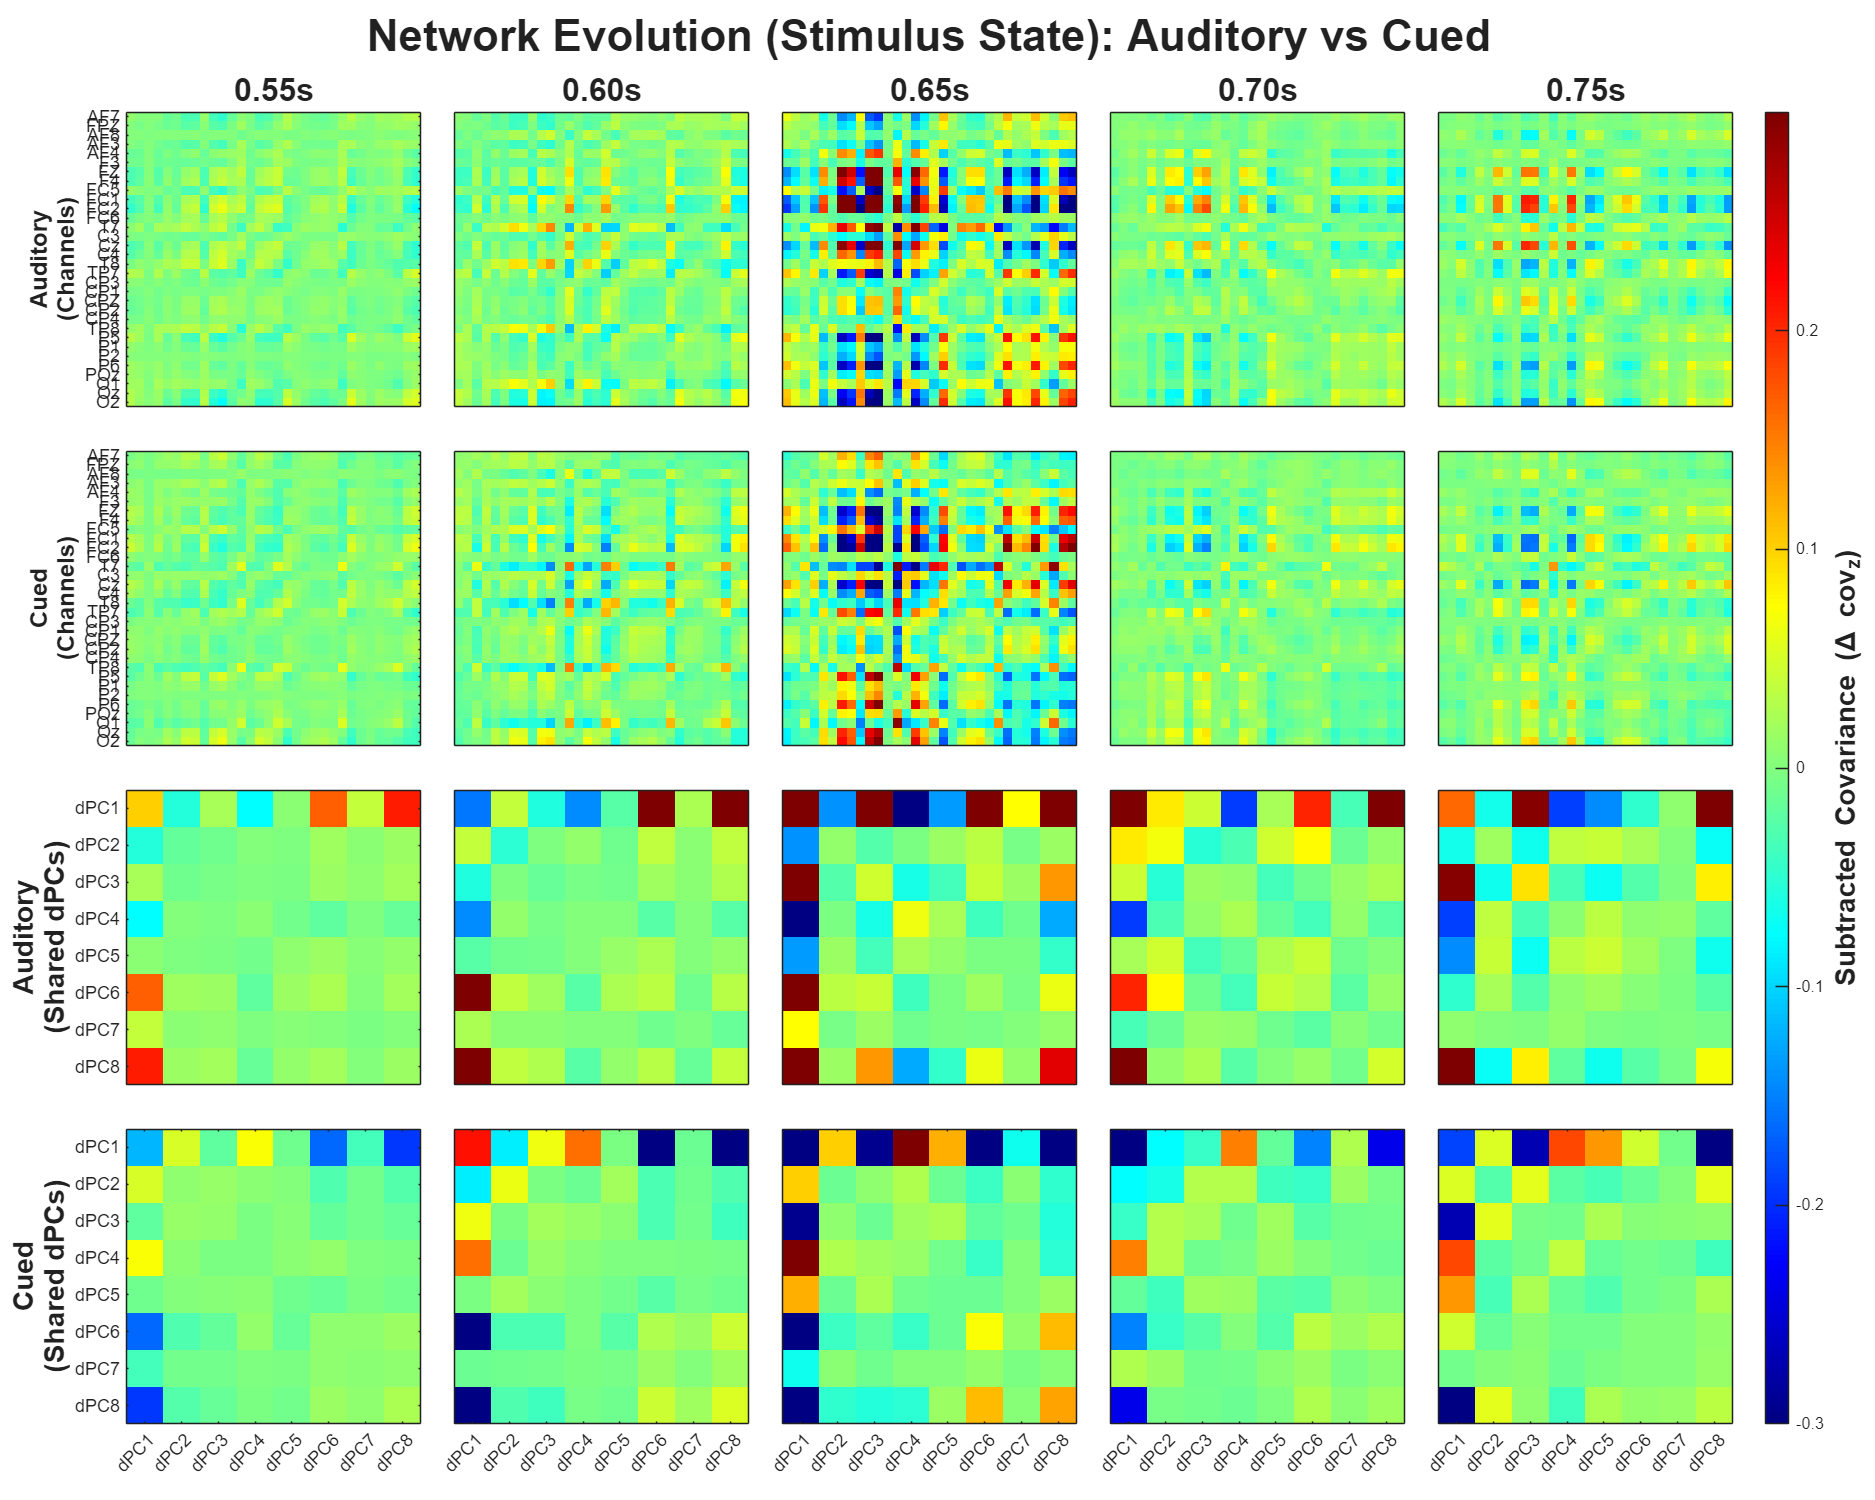

Processing Auditory vs Cued (Cognitive State): 2 Windows x 1000 Shuffles...


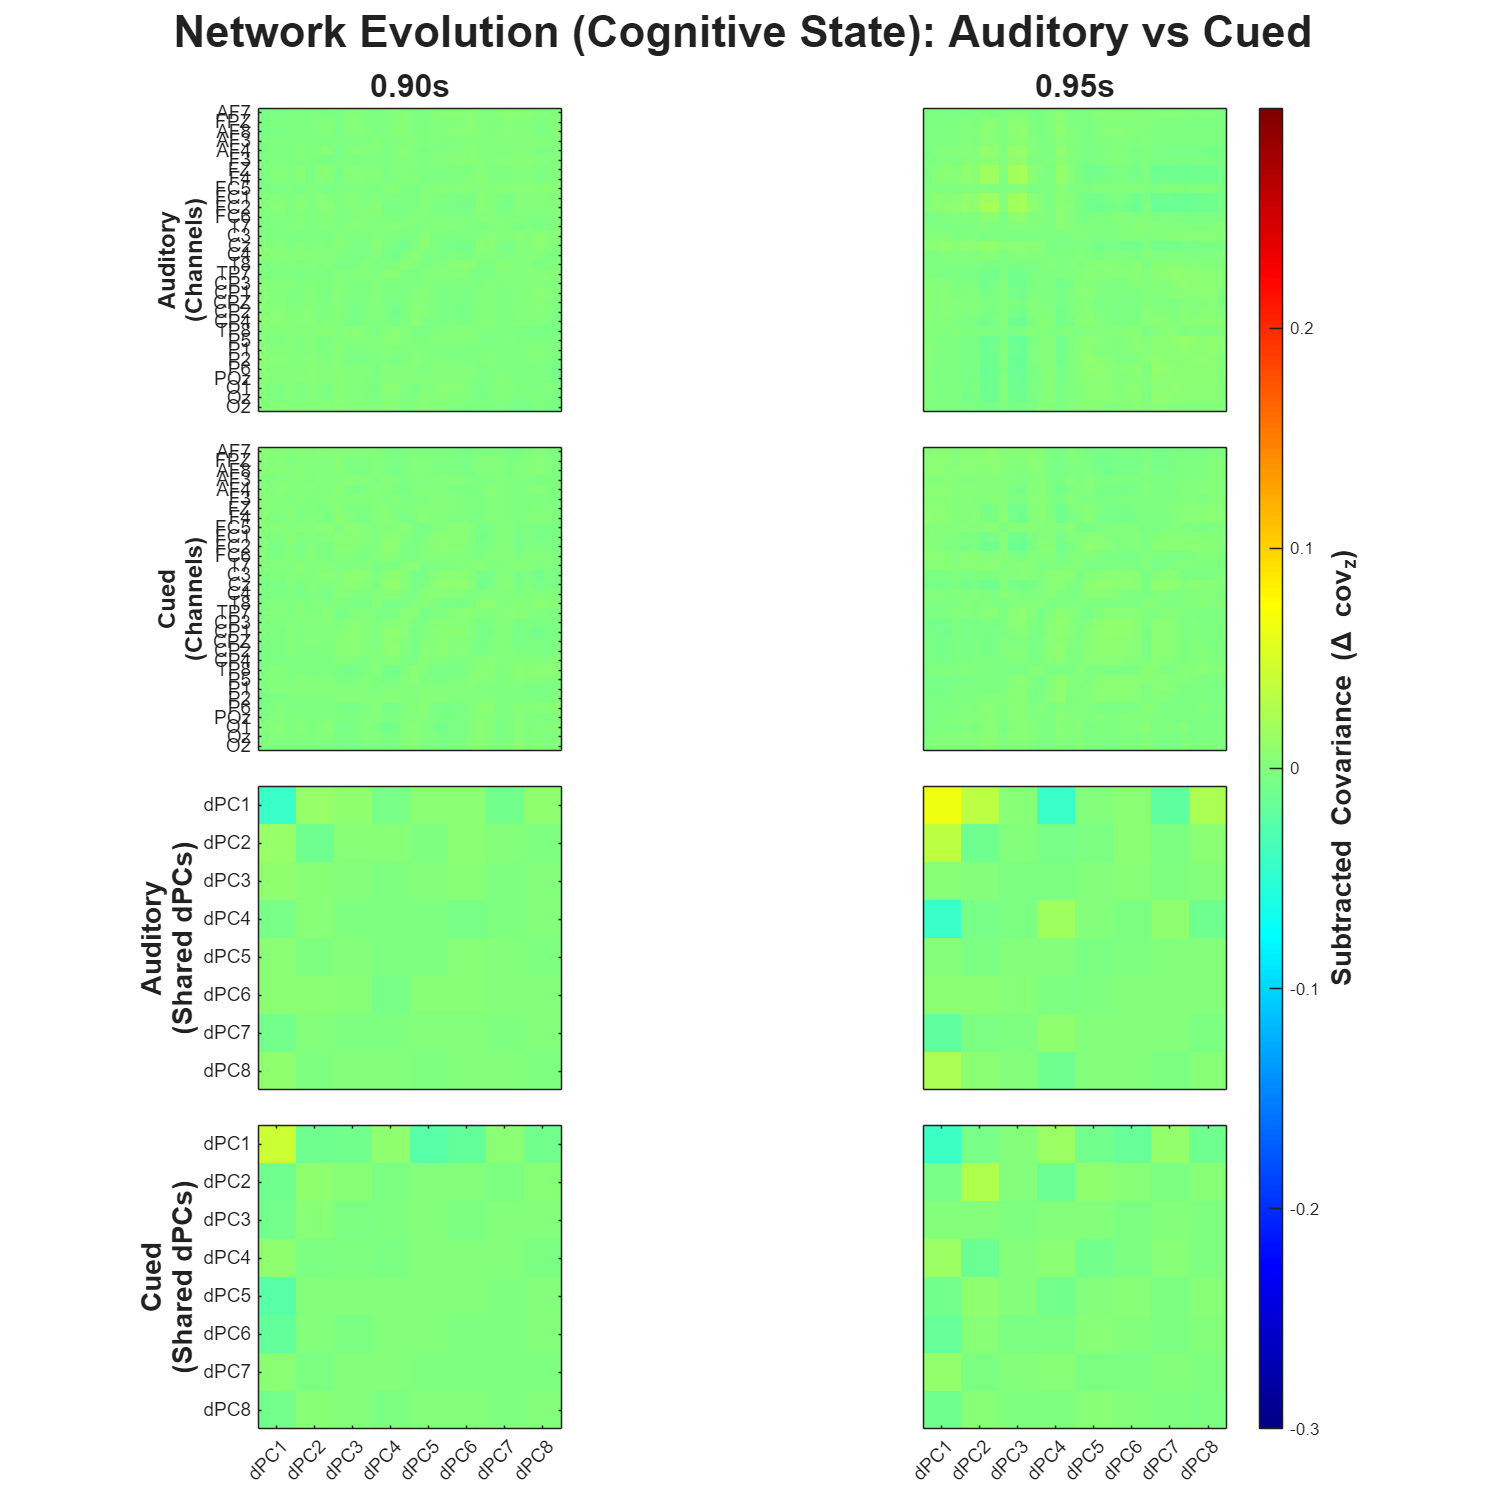

Processing Tactile vs Cued (Stimulus State): 5 Windows x 1000 Shuffles...


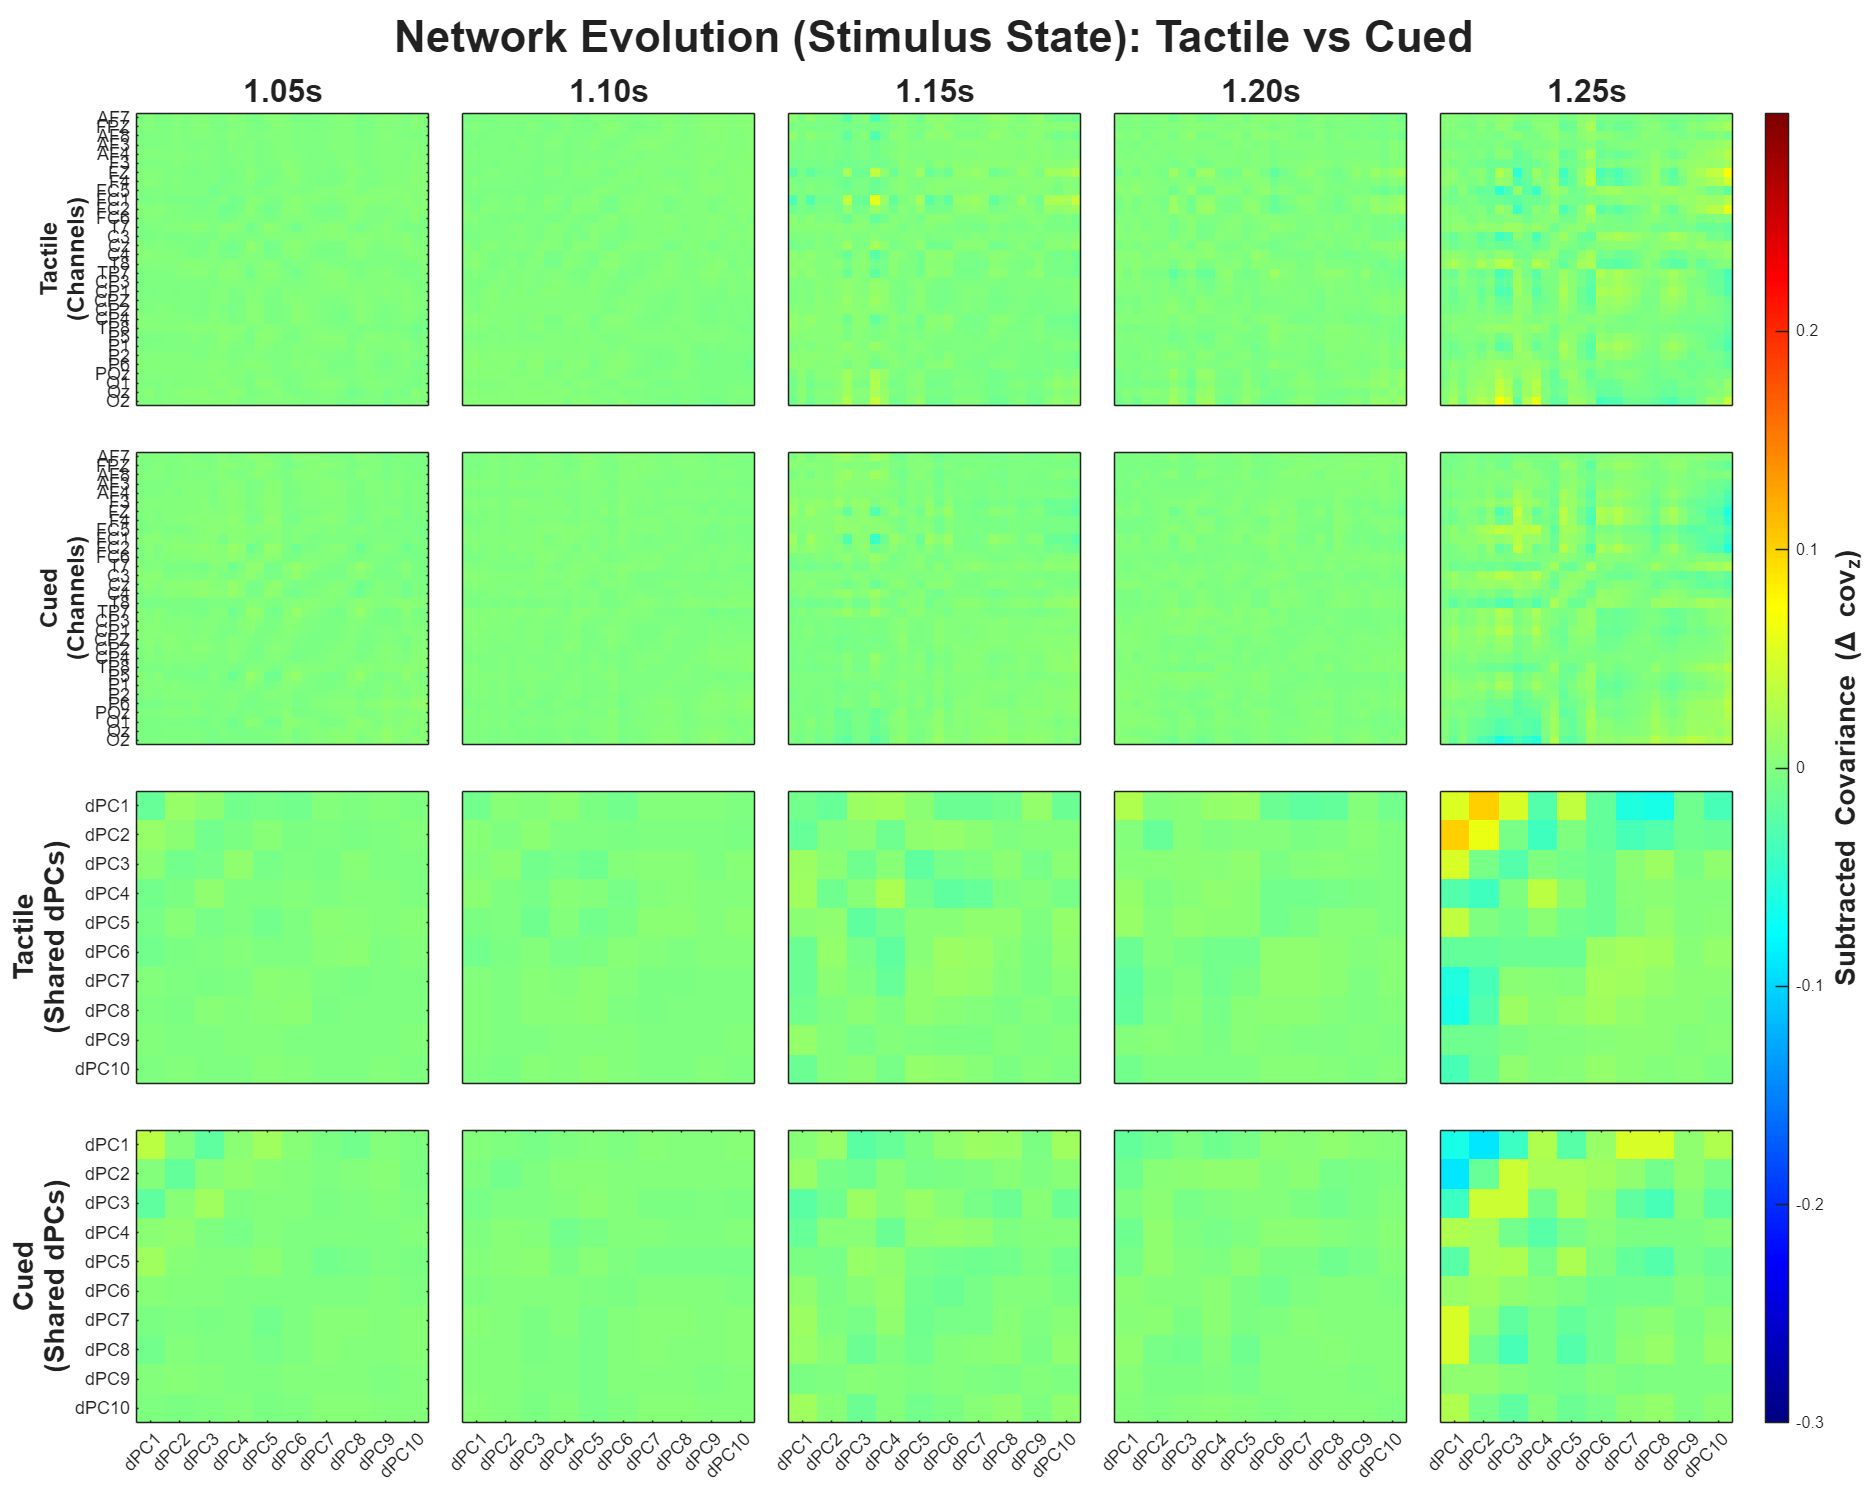

Processing Tactile vs Cued (Cognitive State): 2 Windows x 1000 Shuffles...


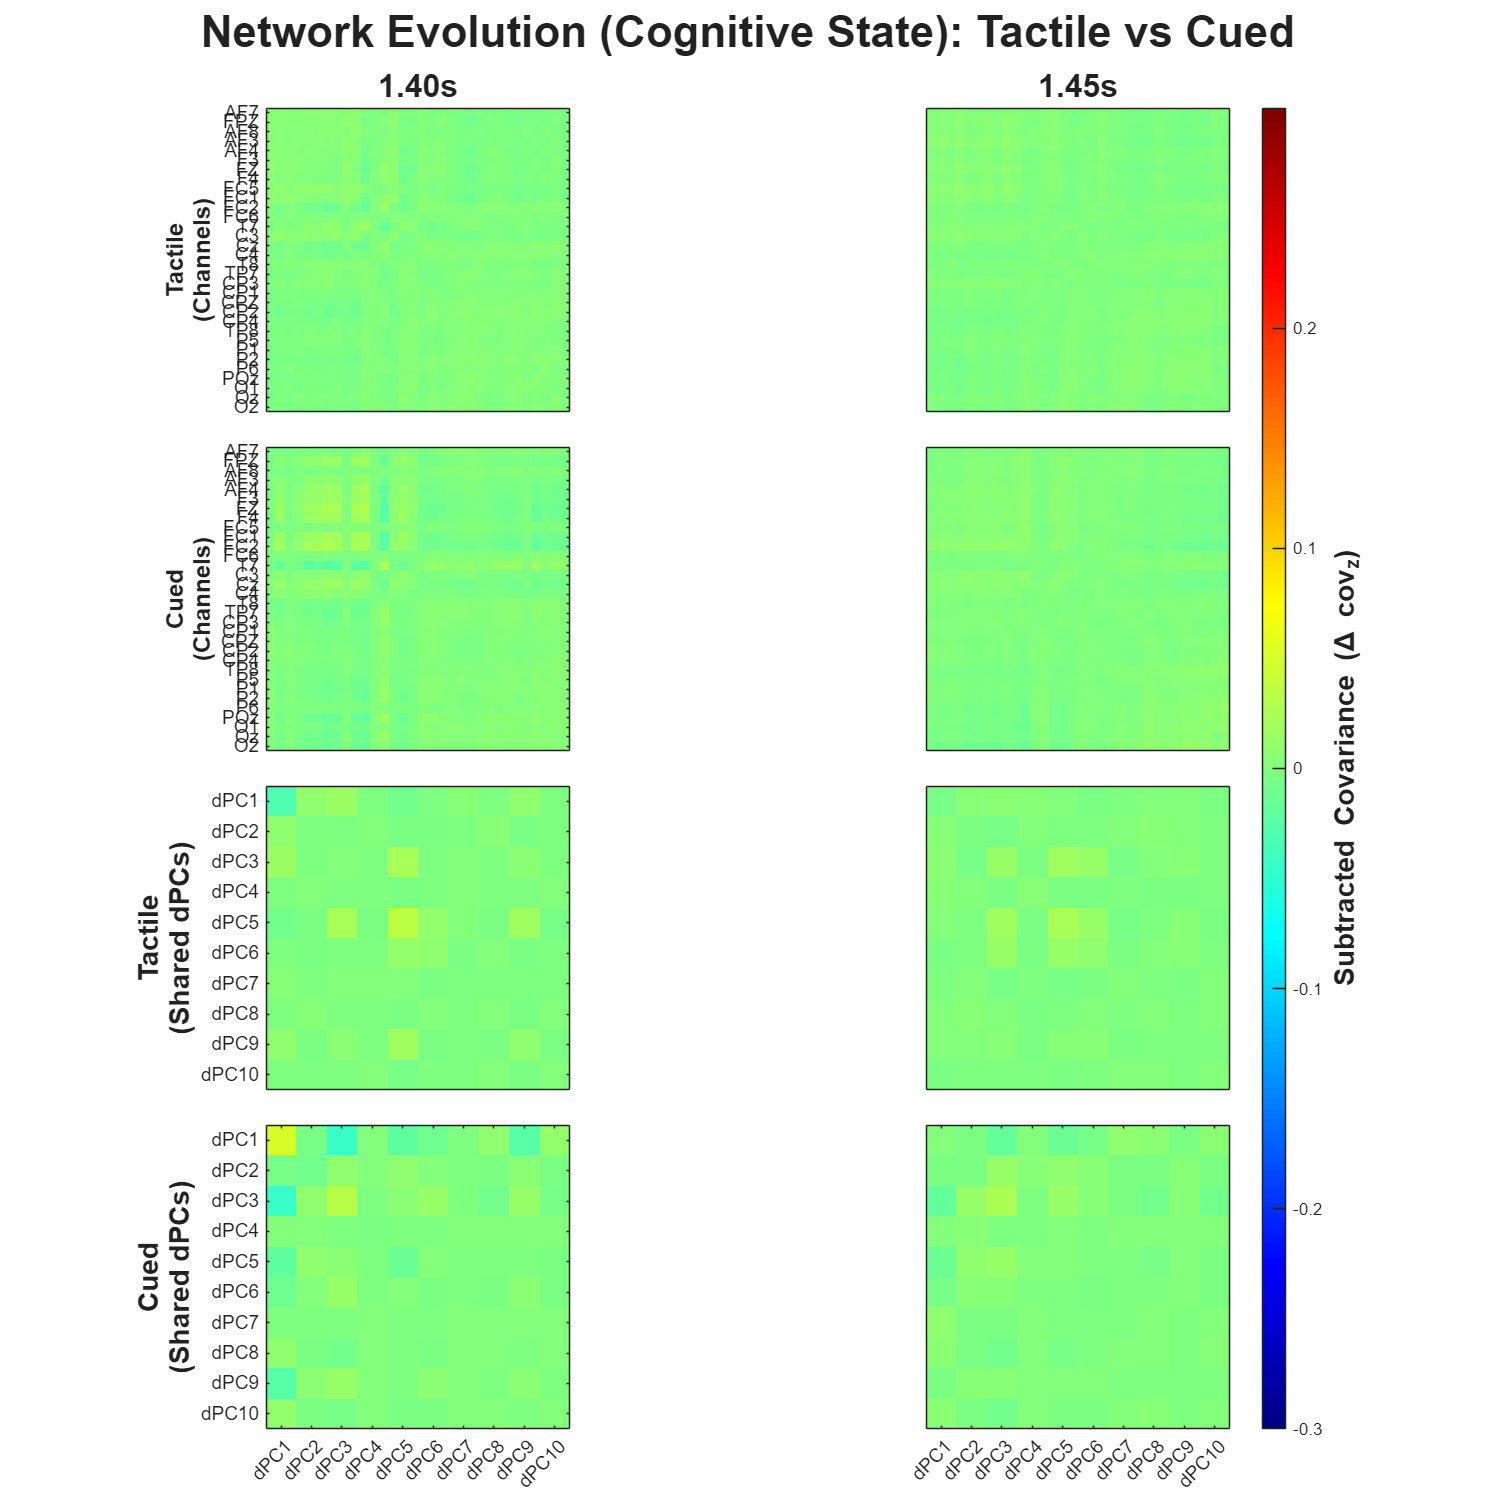

Processing Cued vs Unpred. 500 (Stimulus State): 5 Windows x 1000 Shuffles...


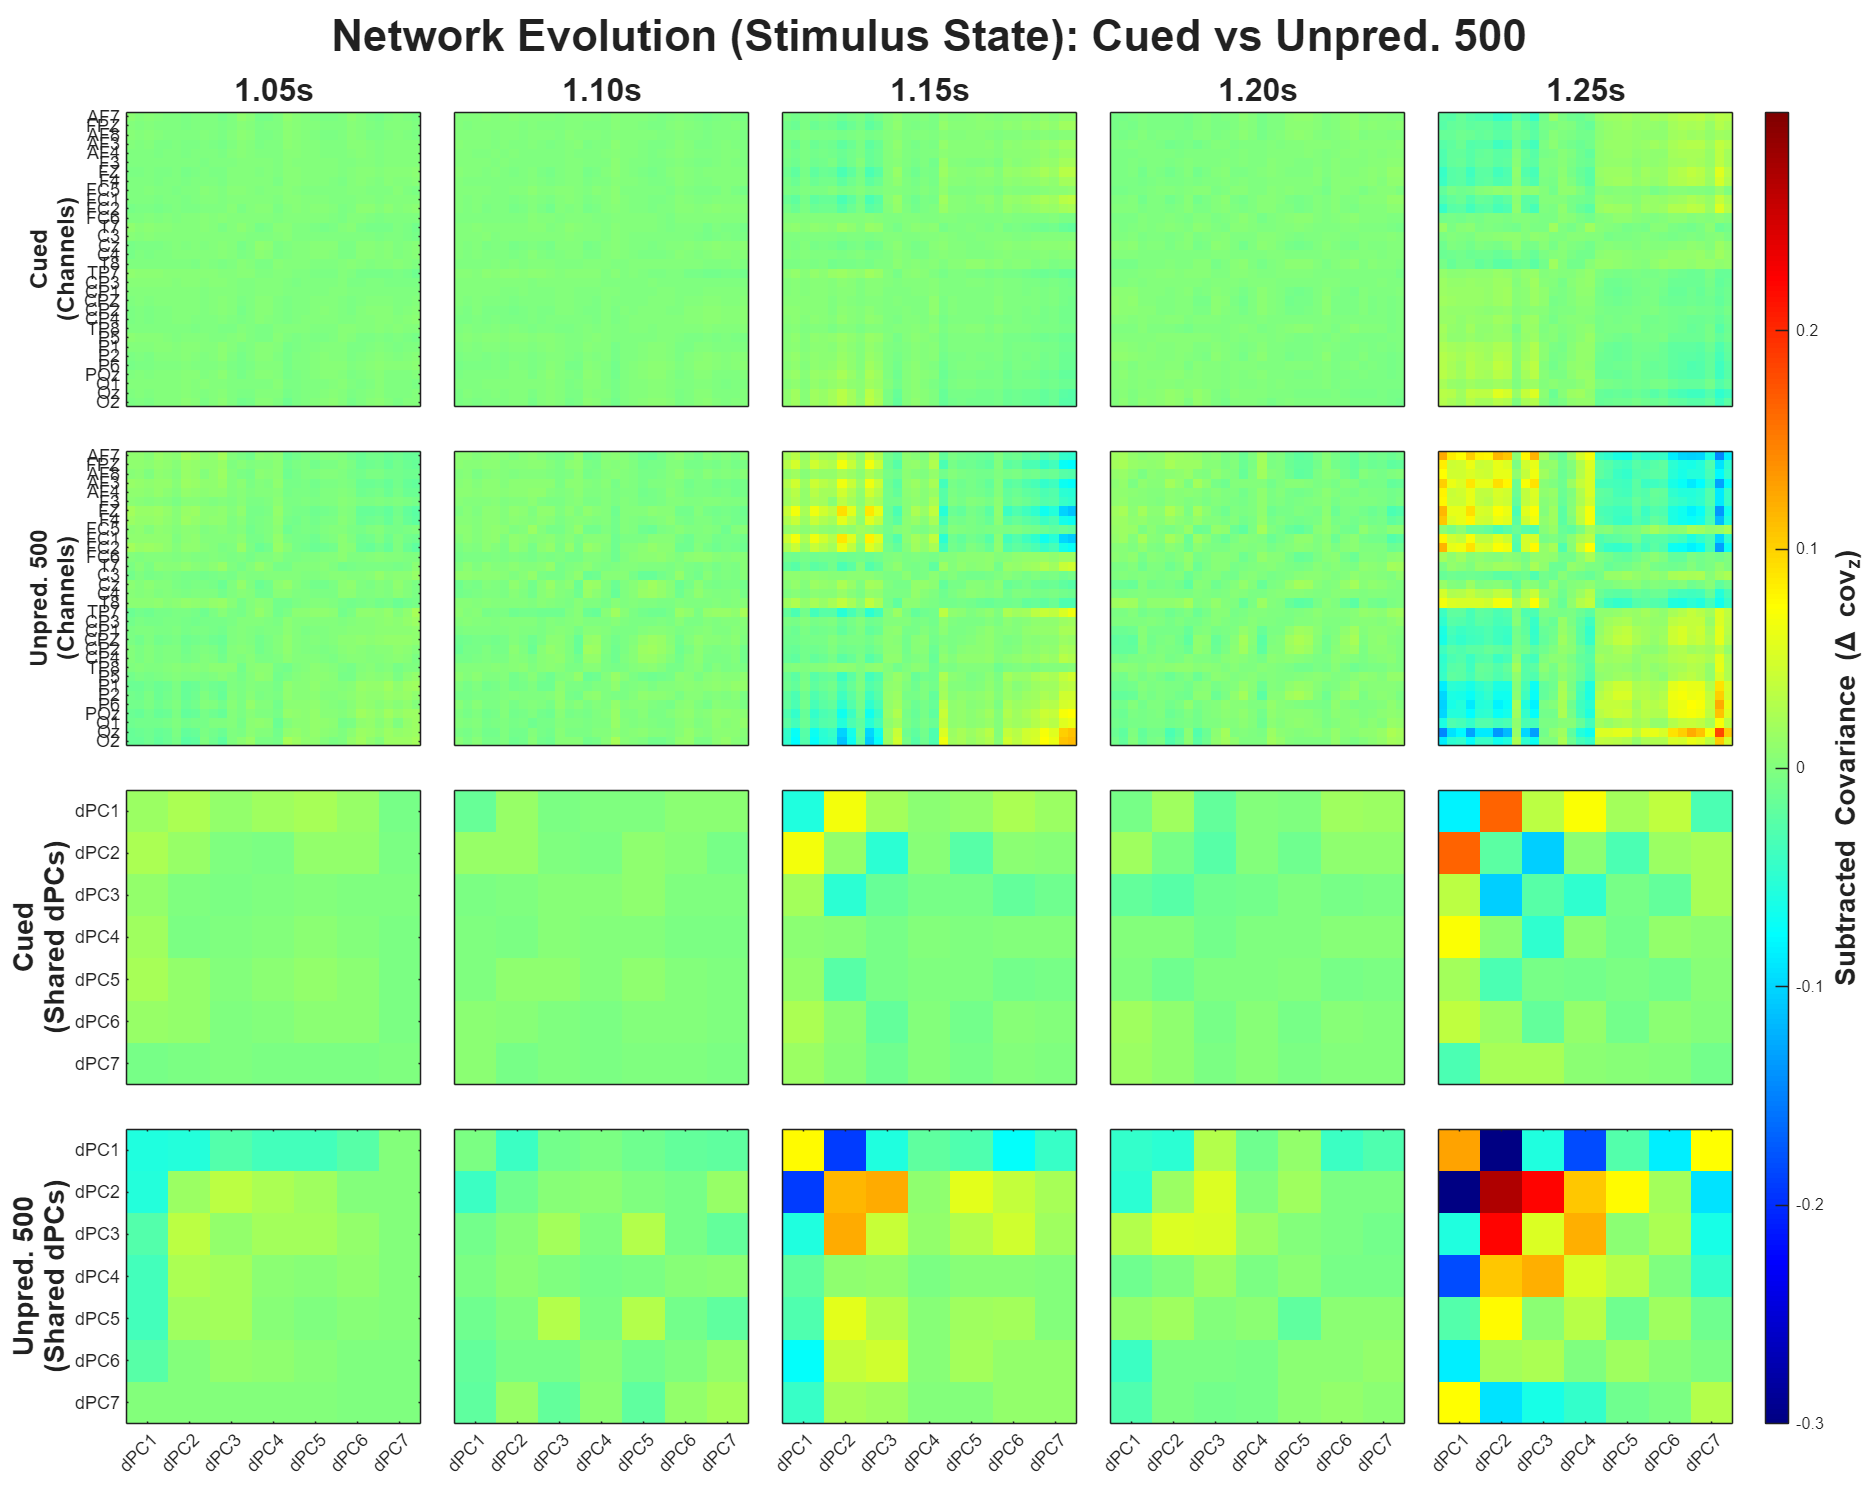

Processing Cued vs Unpred. 500 (Cognitive State): 2 Windows x 1000 Shuffles...


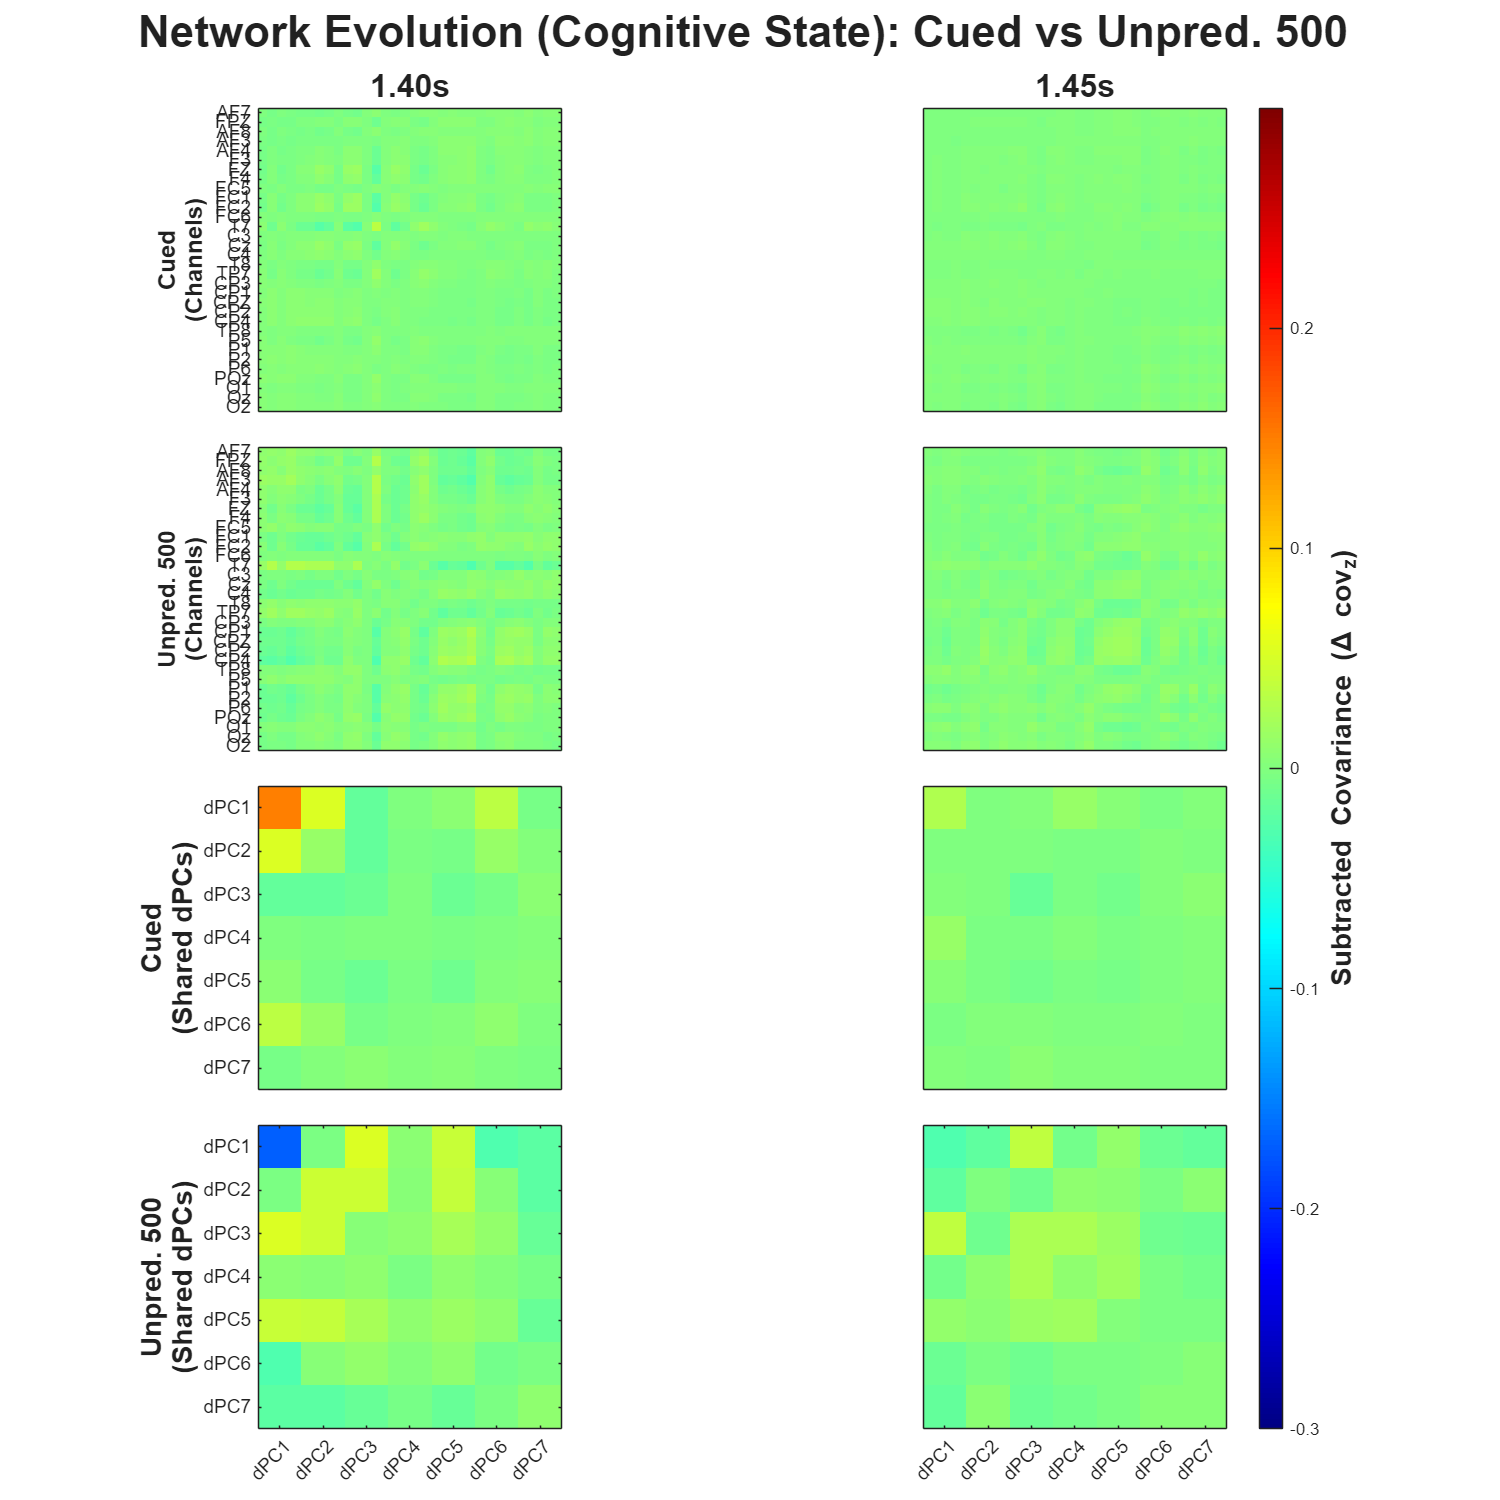

Processing Cued vs Unpred. 2000 (Stimulus State): 5 Windows x 1000 Shuffles...


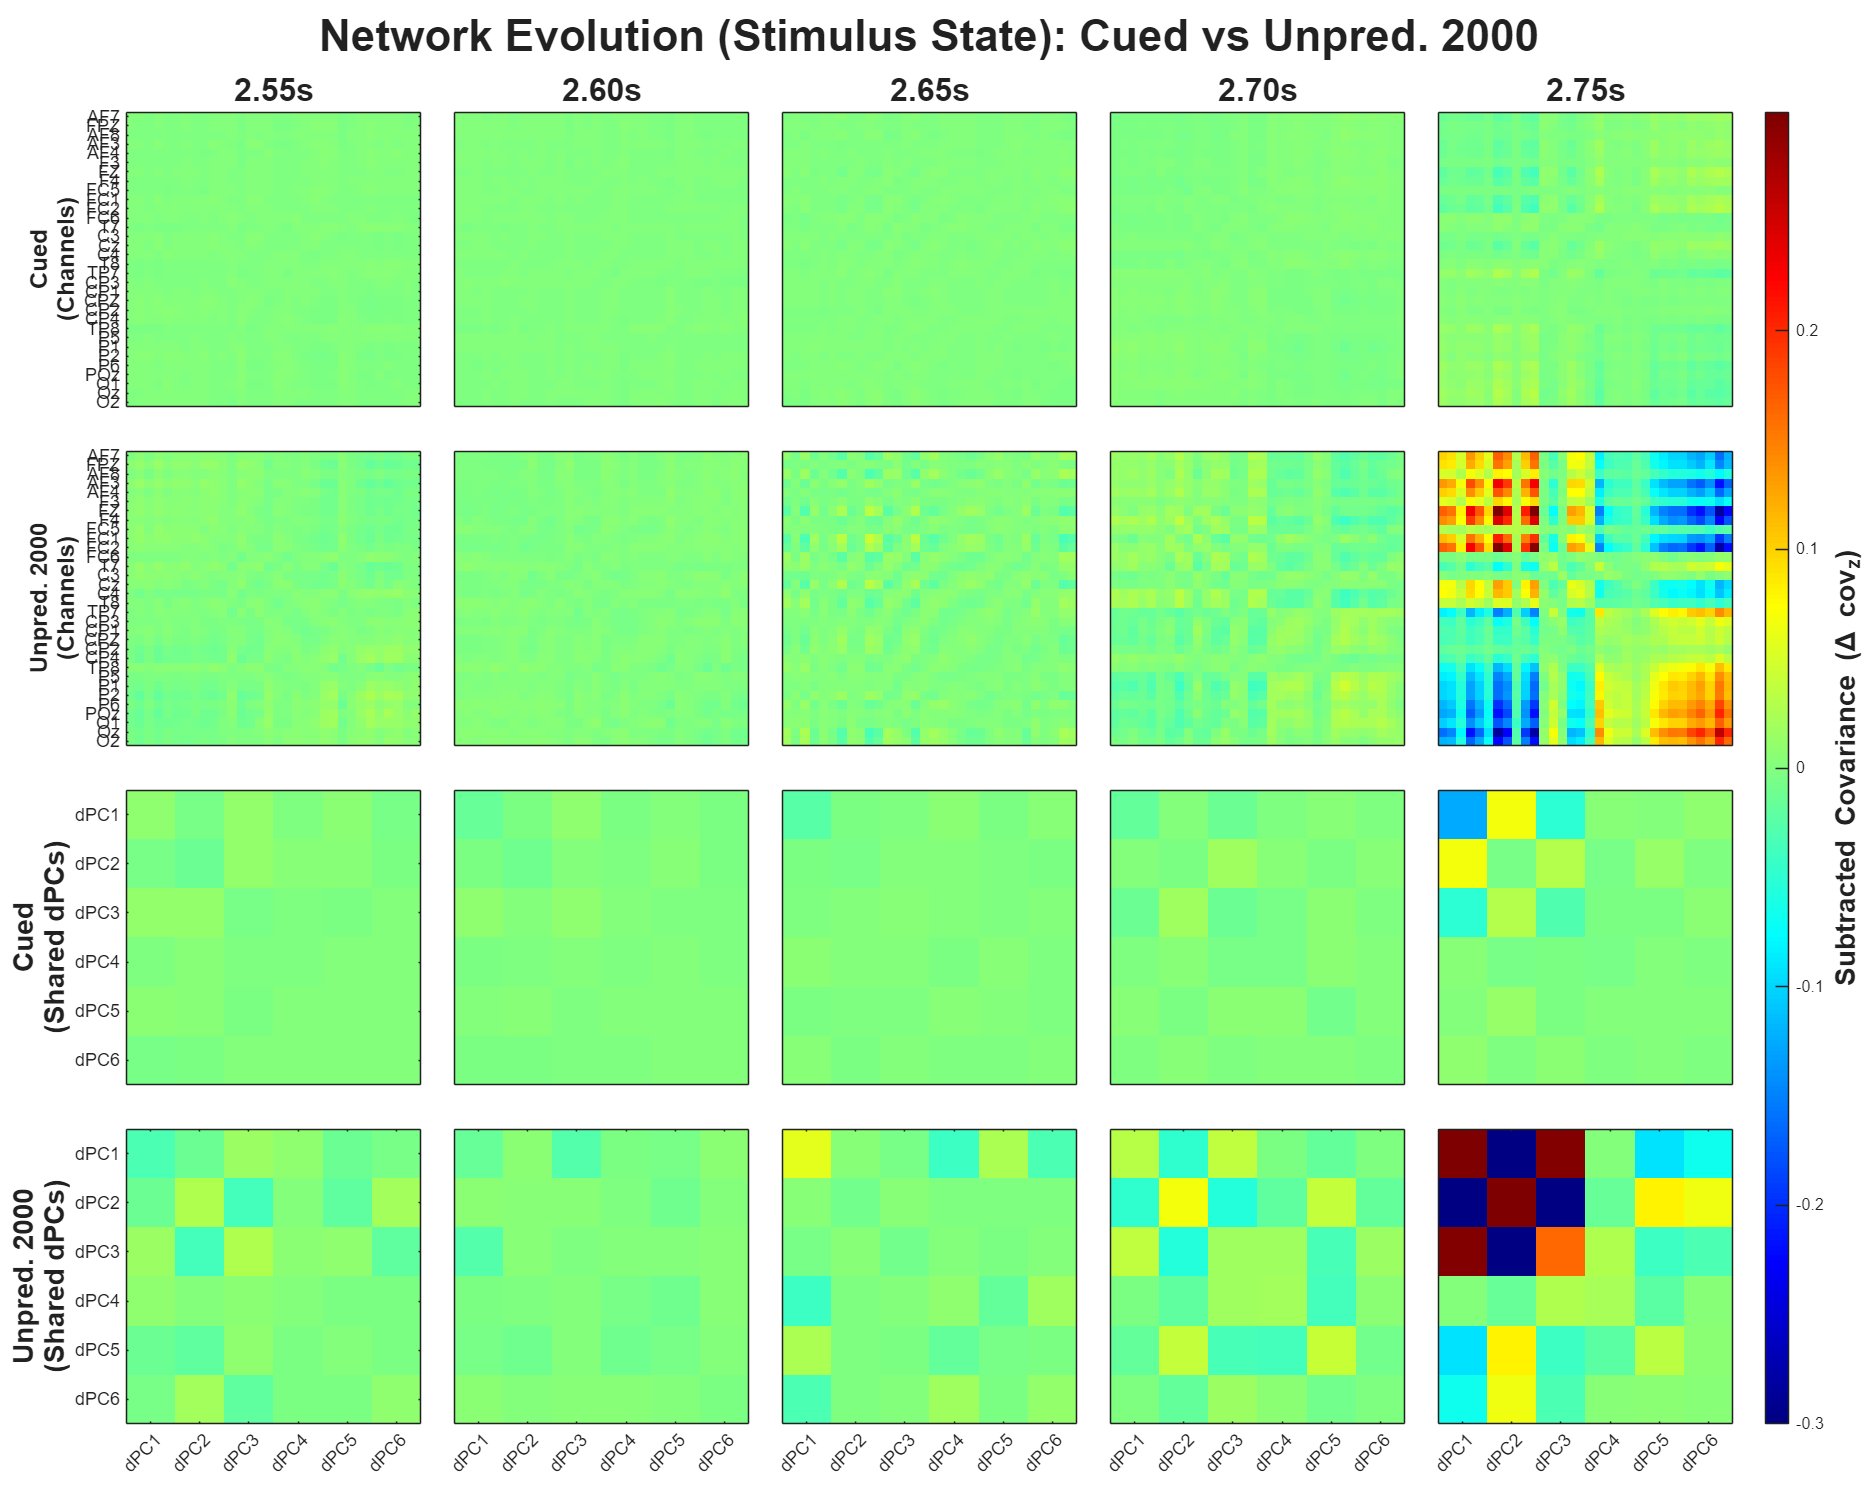

Processing Cued vs Unpred. 2000 (Cognitive State): 2 Windows x 1000 Shuffles...


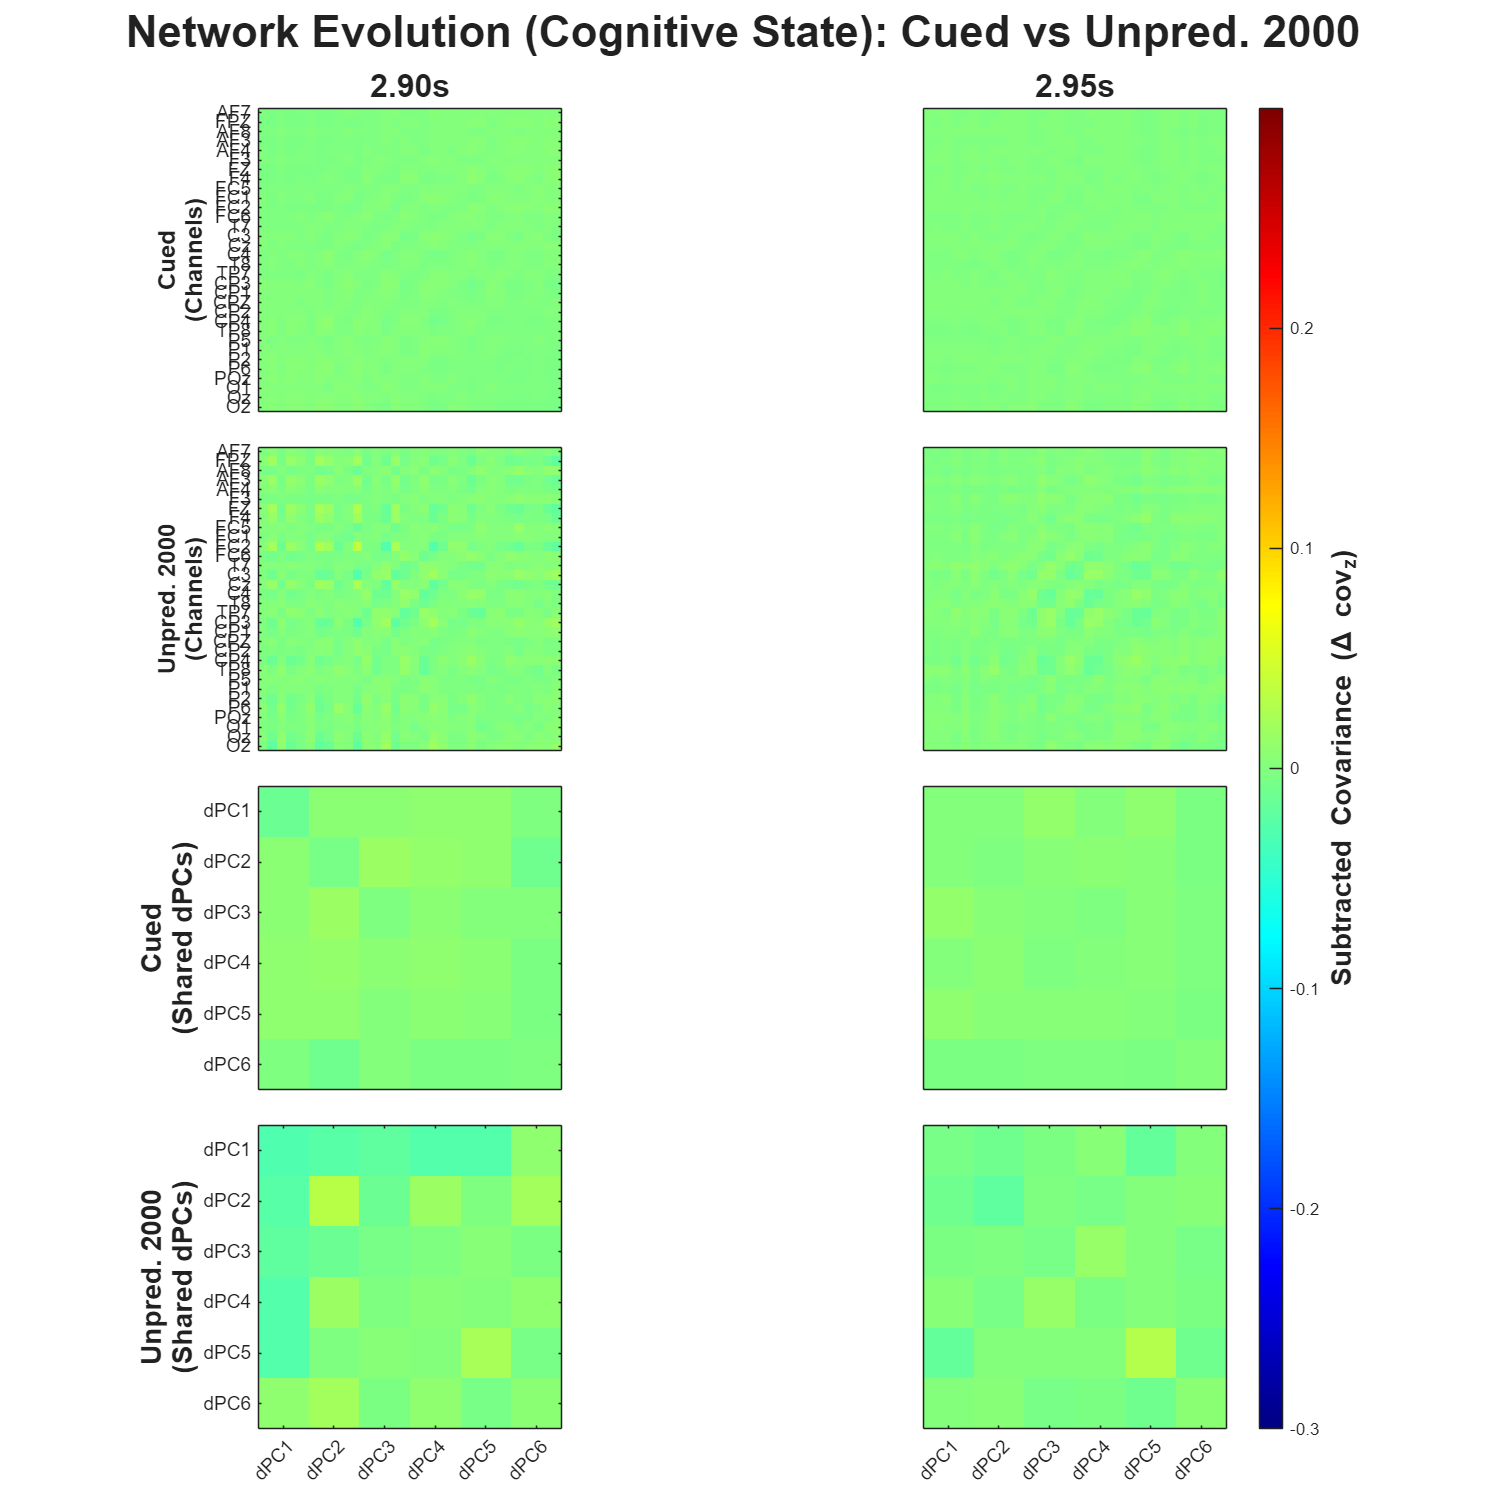

Processing Cued vs Rand. Cued 500 (Stimulus State): 5 Windows x 1000 Shuffles...


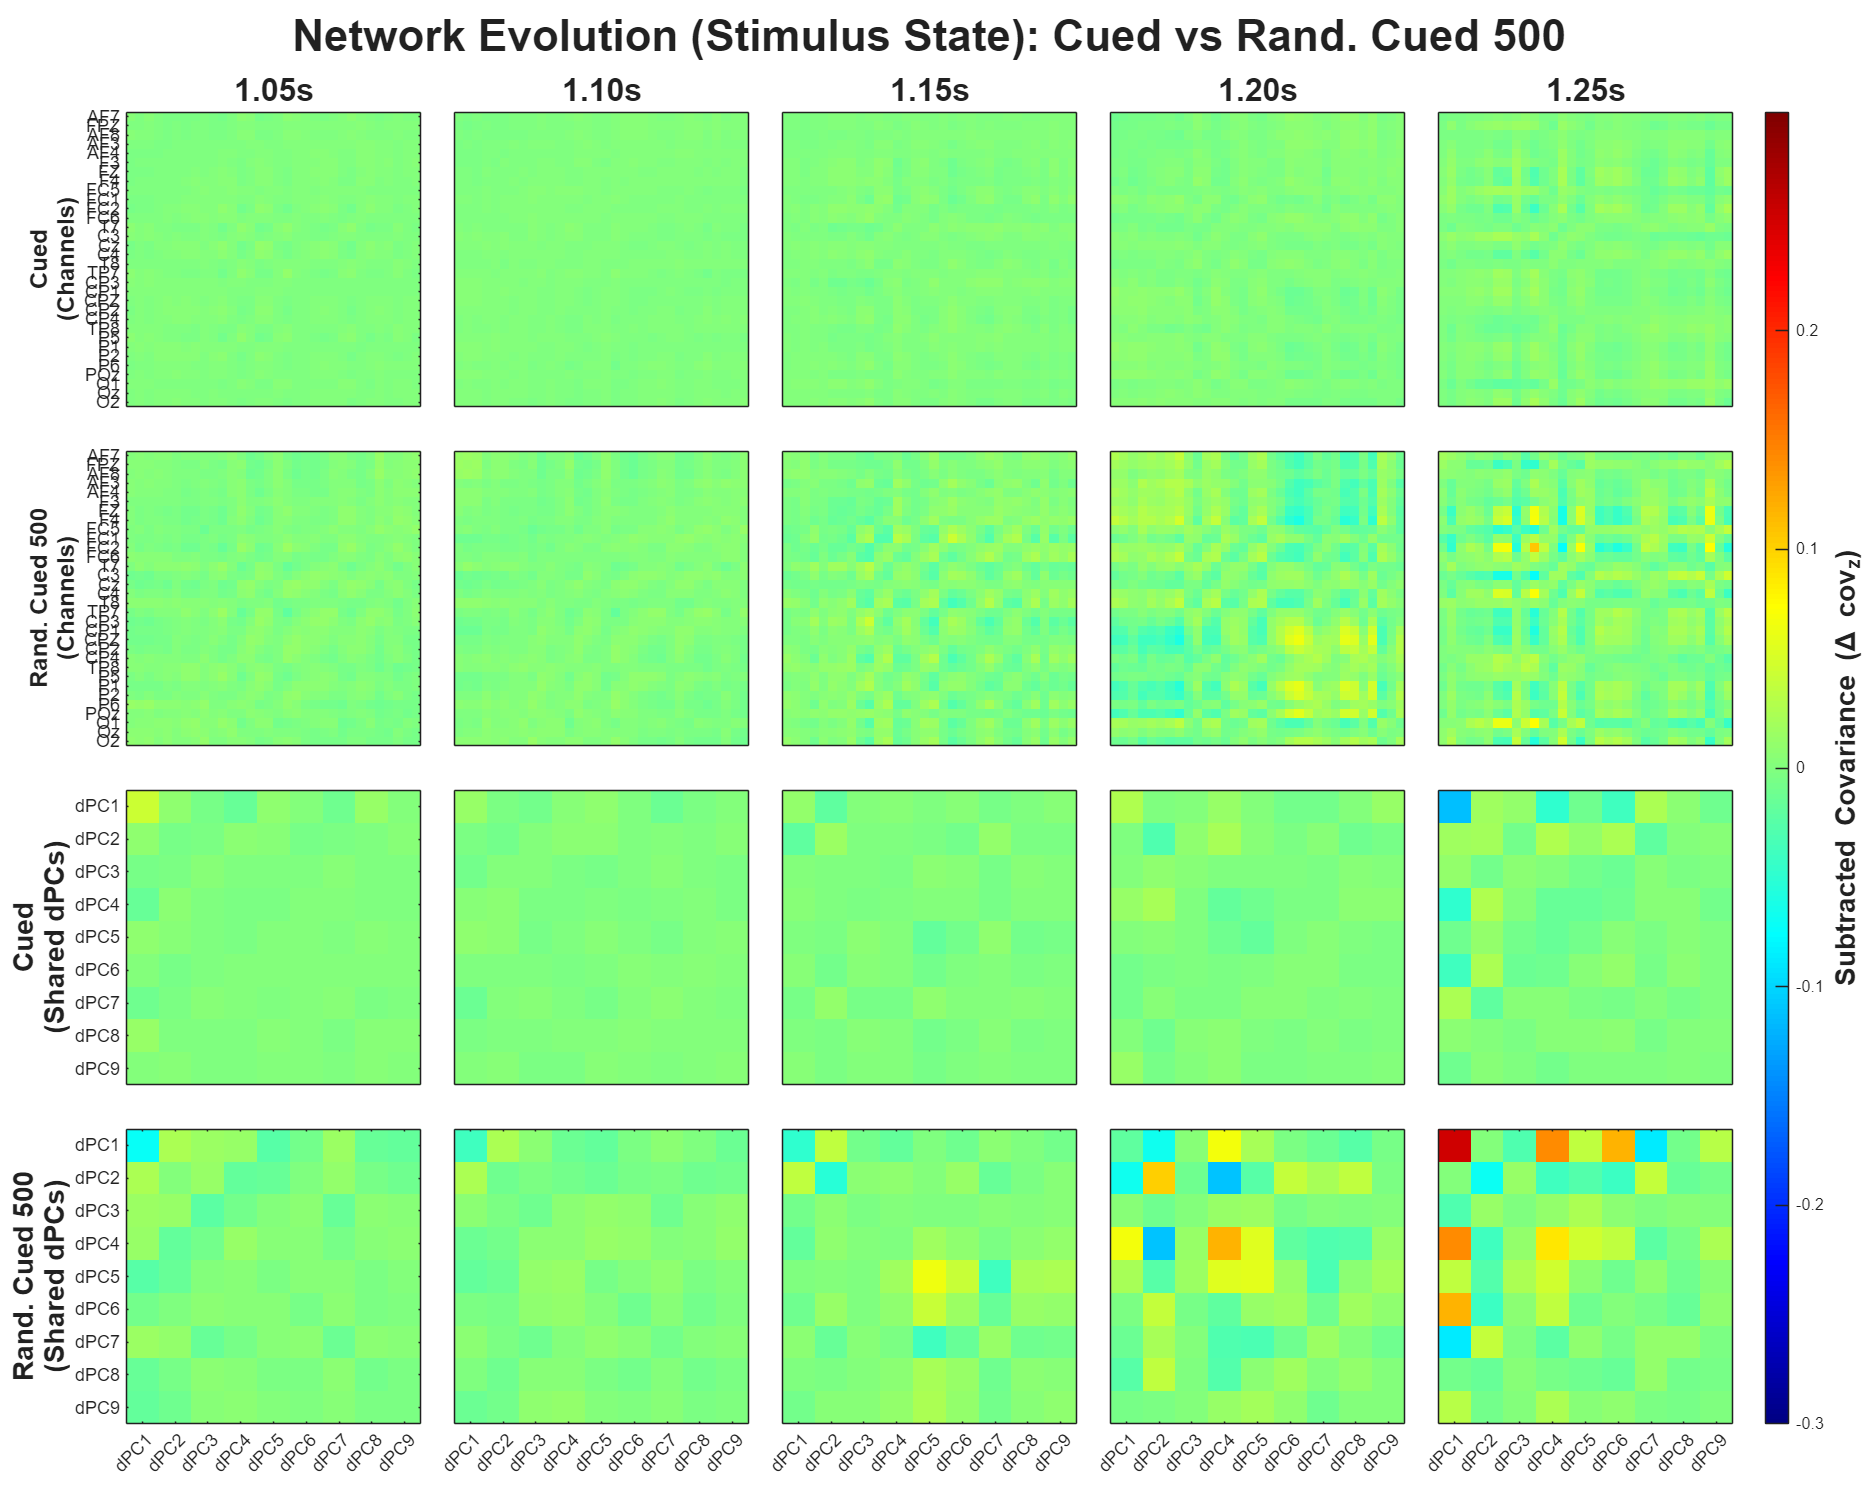

Processing Cued vs Rand. Cued 500 (Cognitive State): 2 Windows x 1000 Shuffles...


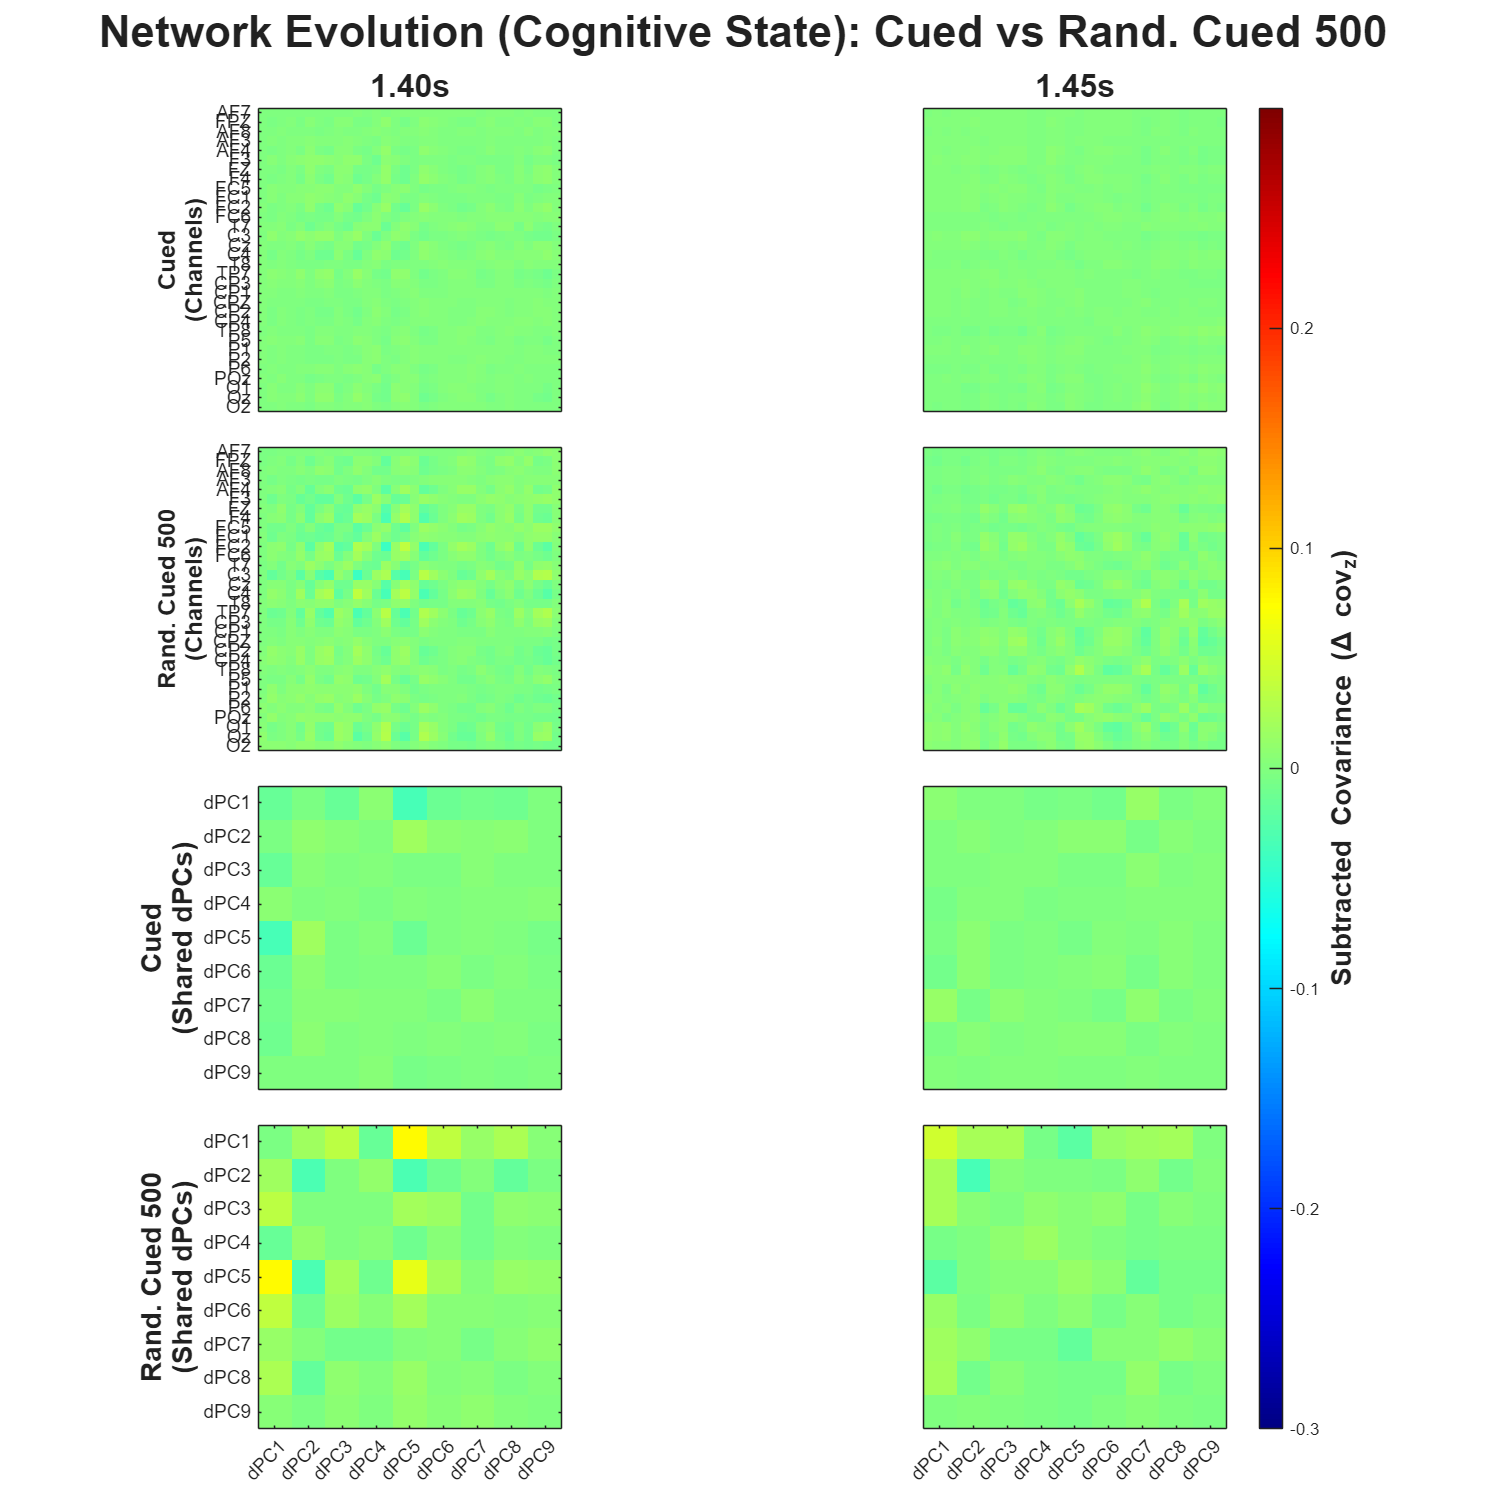

Processing Cued vs Rand. Cued missing (Stimulus State): 5 Windows x 1000 Shuffles...


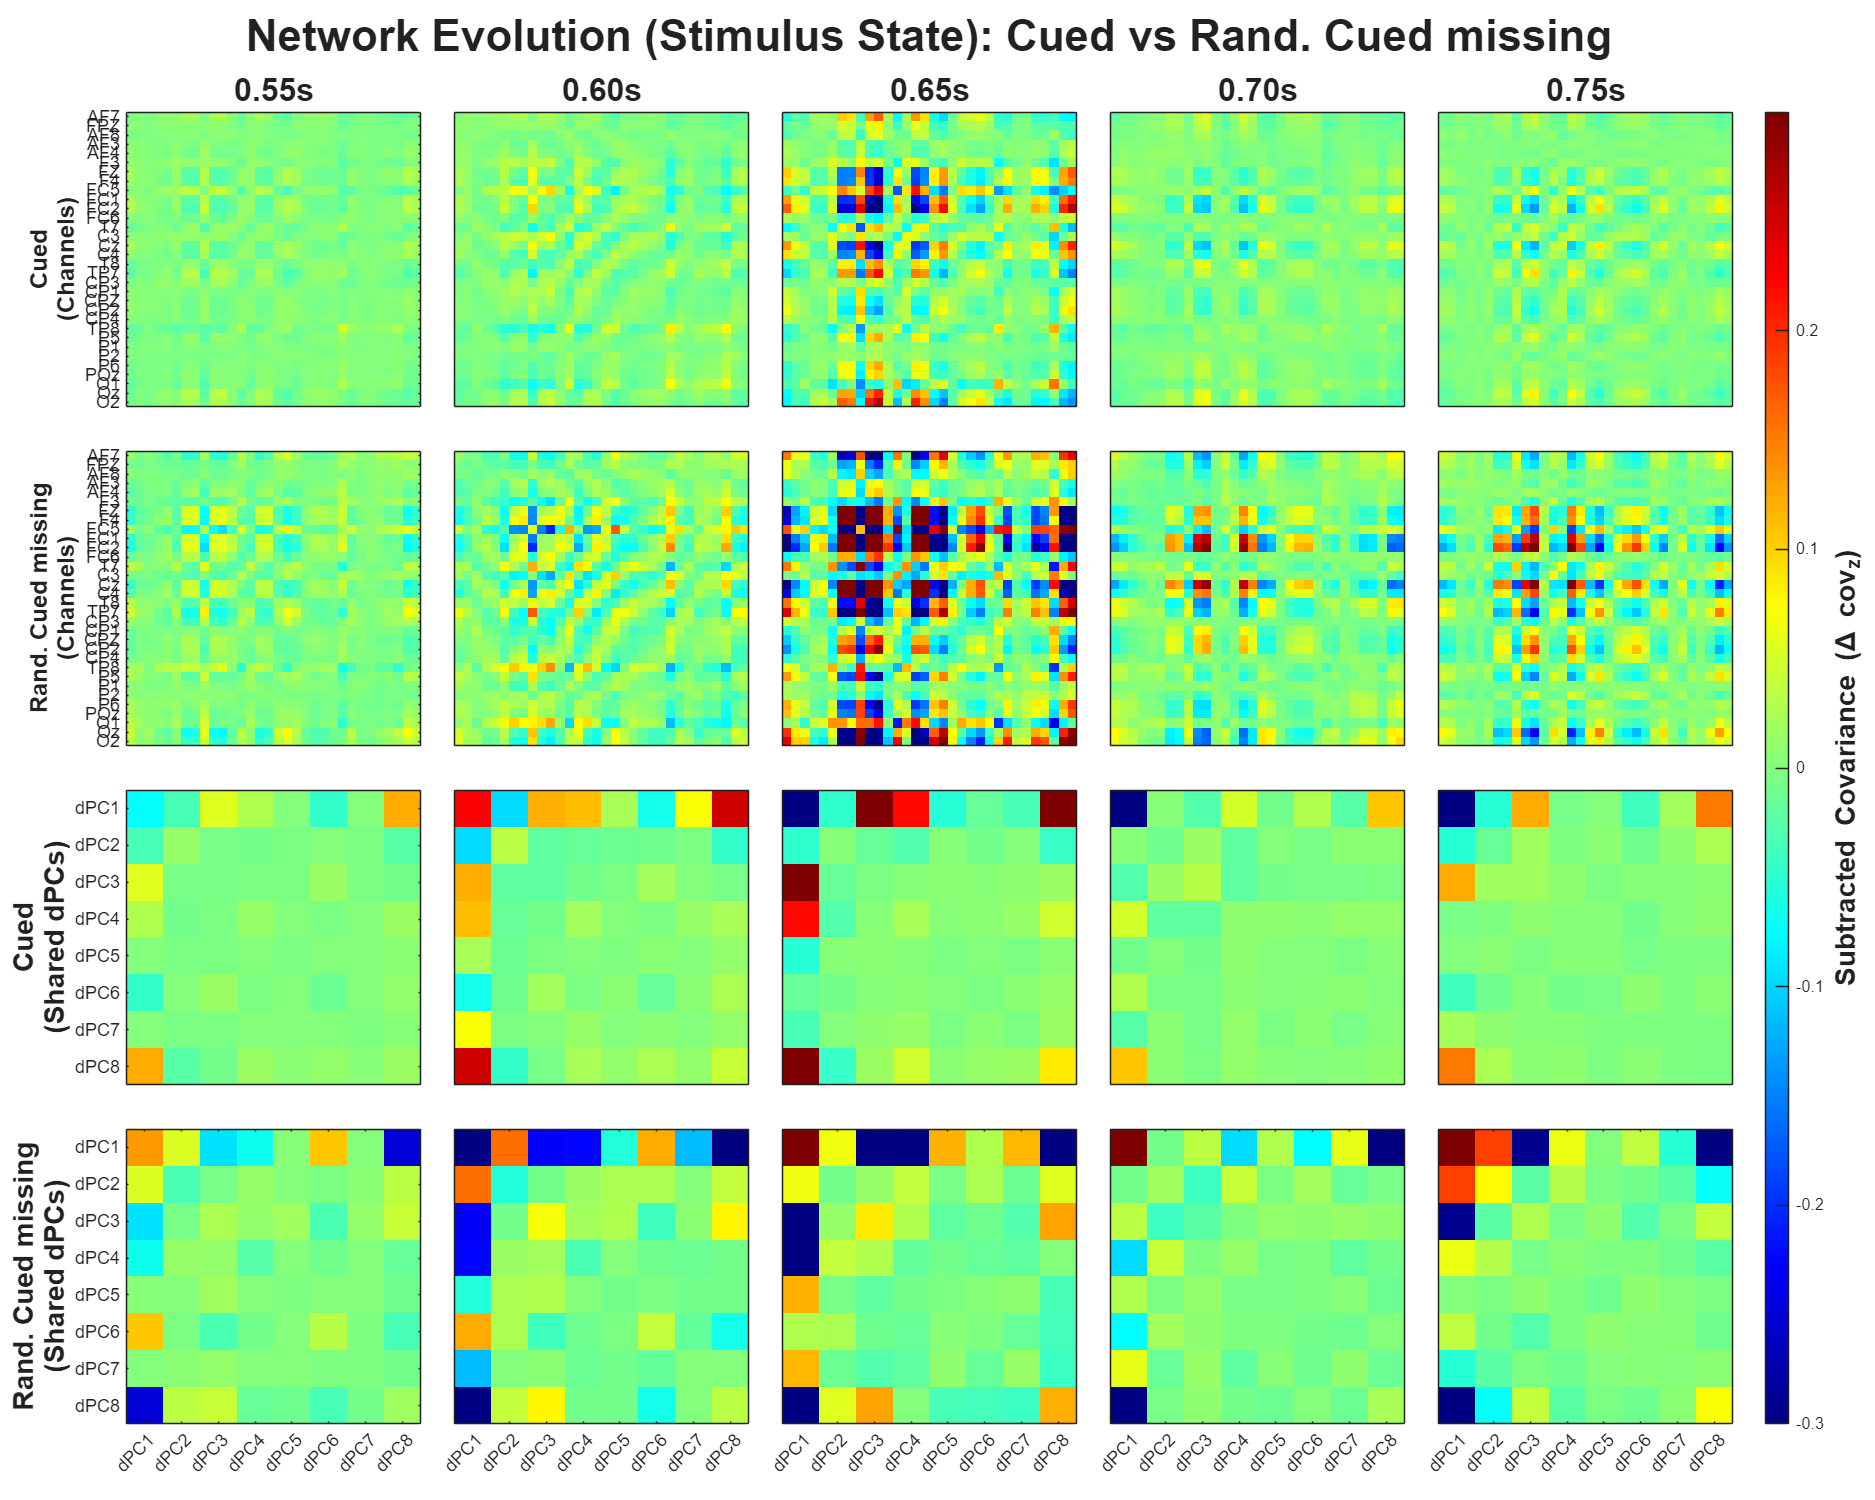

Processing Cued vs Rand. Cued missing (Cognitive State): 8 Windows x 1000 Shuffles...


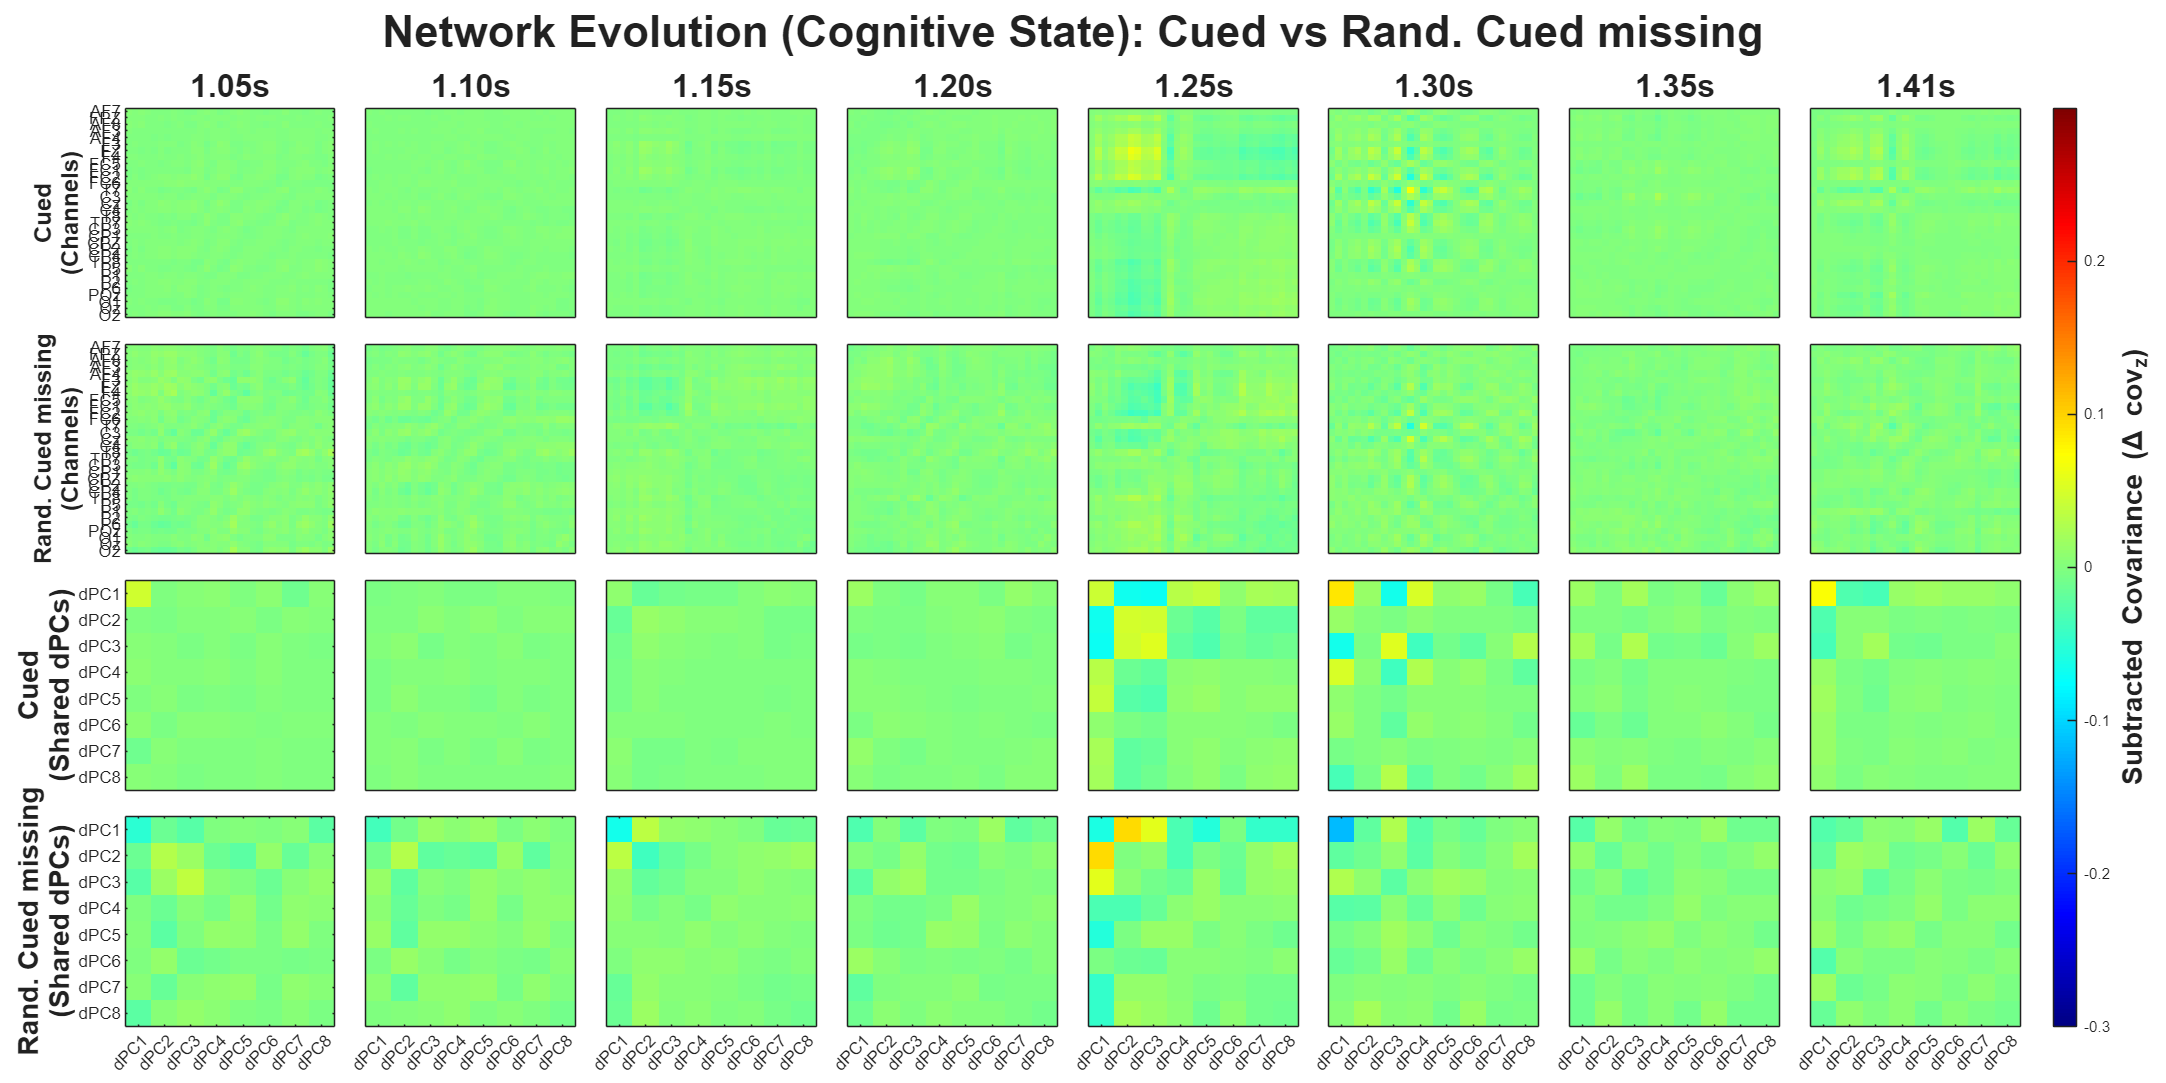


% Inline helper functions
get_clean_name = @(c) strrep(strrep(strrep(strrep(strrep(strrep(c, ...
    'BLA', 'Auditory'), 'BLT', 'Tactile'), 'P1', 'Cued'), ...
    'P2', 'Unpred.'), 'P3', 'Rand. Cued'), '_', ' ');

% Define Pairs: {CondA, CondB, [Stimulus Window], [Cognitive Window]}
pairs = {
    {'BLA', 'P1', [0.5, 0.85], [0.85, 1.0]},
    {'BLT', 'P1', [1.0, 1.35], [1.35, 1.5]},
    {'P1', 'P2_500', [1.0, 1.35], [1.35, 1.5]},    
    {'P1', 'P2_2000', [2.5, 2.85], [2.85, 3.0]}, 
    {'P1', 'P3_500', [1.0, 1.35], [1.35, 1.5]},
    {'P1', 'P3_missing', [0.5, 0.85], [1, 1.5]}
};

state_names = {'Stimulus State', 'Cognitive State'};

target_subj = 1; % Analyzing Subject 1
if isempty(fs), fs = EEG.srate; end % Fallback for sampling rate
n_perms = 1000; % Number of shuffles for the background subtraction

% Sliding window configuration
window_size_ms = 100;
step_size_ms = 50;
win_samples = round((window_size_ms / 1000) * fs);
step_samples = round((step_size_ms / 1000) * fs);

if ~exist('all_channels_str', 'var')
    all_channels_str = arrayfun(@(x) sprintf('Ch%d', x), 1:num_ch, 'UniformOutput', false);
end

for p = 1:length(pairs)
    condA = pairs{p}{1};
    condB = pairs{p}{2};
    cleanA = get_clean_name(condA);
    cleanB = get_clean_name(condB);
    
    if ~isfield(data_all_conds, condA) || ~isfield(data_all_conds, condB)
        warning('Skipping pair %s vs %s (Missing data)', cleanA, cleanB);
        continue;
    end
    
    % --- Extract FULL Single Trials [Channels x Time x Trials] ---
    trialsA_raw = data_all_conds.(condA){target_subj};
    trialsB_raw = data_all_conds.(condB){target_subj};
    
    nA = size(trialsA_raw, 3);
    nB = size(trialsB_raw, 3);
    total_trials = nA + nB;
    if nA == 0 || nB == 0, continue; end
    
    % --- GLOBAL Z-SCORE PER TRIAL ---
    trialsA = zeros(size(trialsA_raw));
    trialsB = zeros(size(trialsB_raw));
    for tr = 1:nA, trialsA(:,:,tr) = zscore(trialsA_raw(:,:,tr), 0, 2); end
    for tr = 1:nB, trialsB(:,:,tr) = zscore(trialsB_raw(:,:,tr), 0, 2); end
    
    avgA = mean(trialsA, 3, 'omitnan');
    avgB = mean(trialsB, 3, 'omitnan');
    
    %% --- 1. DIMENSIONALITY REDUCTION (GLOBAL MANIFOLD) ---
    data_combined = [avgA, avgB];
    data_combined_centered = data_combined - mean(data_combined, 2);
    
    [k_opt, ~] = velicer_map(data_combined_centered', true);
    if k_opt < 2, k_opt = 2; end 
    
    try
        X_dpca = cat(3, avgA, avgB); 
        X_dpca_centered = bsxfun(@minus, X_dpca, mean(X_dpca(:,:), 2));
        [W_dpca, ~, ~] = dpca(X_dpca_centered, k_opt); 
        W = W_dpca'; % Transpose to [k x Channels]
    catch 
        [~, ~, V] = svd(data_combined_centered', 'econ');
        W = V(:, 1:k_opt)'; 
    end
    
    %% --- 2. PROJECT ALL SINGLE TRIALS INTO dPC SPACE ---
    T_len = size(trialsA, 2);
    trialsA_flat = reshape(trialsA, num_ch, []);
    compA_flat = W * trialsA_flat; 
    comp_trialsA = reshape(compA_flat, k_opt, T_len, nA);
    
    trialsB_flat = reshape(trialsB, num_ch, []);
    compB_flat = W * trialsB_flat; 
    comp_trialsB = reshape(compB_flat, k_opt, T_len, nB);
    
    % Pool trials together for the 1000x shuffler
    pool_trials_ch = cat(3, trialsA, trialsB);
    pool_trials_pc = cat(3, comp_trialsA, comp_trialsB);
    
    %% --- 3. LOOP OVER BOTH STATES (Stimulus & Cognitive) ---
    for state_idx = 1:2
        t_win = pairs{p}{2 + state_idx}; % Index 3 is Stim, Index 4 is Cog
        active_state = state_names{state_idx};
        
        idx_start = find(time_ms_eeg >= t_win(1), 1, 'first');
        idx_end = find(time_ms_eeg <= t_win(2), 1, 'last');
        
        time_chunk = time_ms_eeg(idx_start:idx_end);
        num_chunk_points = length(time_chunk);
        
        start_idx = 1 : step_samples : (num_chunk_points - win_samples + 1);
        num_windows = length(start_idx);
        if num_windows == 0, continue; end % Safeguard against windows smaller than 100ms
        
        % Storage for Subtracted Covariance Matrices
        sub_ch_A_all = nan(num_ch, num_ch, num_windows);
        sub_ch_B_all = nan(num_ch, num_ch, num_windows);
        sub_pc_A_all = nan(k_opt, k_opt, num_windows);
        sub_pc_B_all = nan(k_opt, k_opt, num_windows);
        window_centers = zeros(1, num_windows);
        
        fprintf('Processing %s vs %s (%s): %d Windows x %d Shuffles...\n', ...
            cleanA, cleanB, active_state, num_windows, n_perms);
        
        for w = 1:num_windows
            w_s = idx_start + start_idx(w) - 1;
            w_e = w_s + win_samples - 1;
            window_centers(w) = mean(time_ms_eeg(w_s:w_e));
            
            % A. Calculate REAL COVARIANCE
            real_ch_A = cov(mean(trialsA(:, w_s:w_e, :), 3, 'omitnan')');
            real_ch_B = cov(mean(trialsB(:, w_s:w_e, :), 3, 'omitnan')');
            real_pc_A = cov(mean(comp_trialsA(:, w_s:w_e, :), 3, 'omitnan')');
            real_pc_B = cov(mean(comp_trialsB(:, w_s:w_e, :), 3, 'omitnan')');
            
            % B. Calculate BACKGROUND COVARIANCE via Permutation
            null_ch_A = nan(num_ch, num_ch, n_perms); null_ch_B = nan(num_ch, num_ch, n_perms);
            null_pc_A = nan(k_opt, k_opt, n_perms);   null_pc_B = nan(k_opt, k_opt, n_perms);
            
            pool_ch_slice = pool_trials_ch(:, w_s:w_e, :);
            pool_pc_slice = pool_trials_pc(:, w_s:w_e, :);
            
            for prm = 1:n_perms
                shuf_idx = randperm(total_trials);
                idxA = shuf_idx(1:nA);
                idxB = shuf_idx(nA+1:end);
                
                % Pseudo Covariance
                null_ch_A(:,:,prm) = cov(mean(pool_ch_slice(:,:,idxA), 3, 'omitnan')');
                null_ch_B(:,:,prm) = cov(mean(pool_ch_slice(:,:,idxB), 3, 'omitnan')');
                null_pc_A(:,:,prm) = cov(mean(pool_pc_slice(:,:,idxA), 3, 'omitnan')');
                null_pc_B(:,:,prm) = cov(mean(pool_pc_slice(:,:,idxB), 3, 'omitnan')');
            end
            
            % C. SUBTRACT to isolate Condition-Specific Network
            sub_ch_A_all(:,:,w) = real_ch_A - mean(null_ch_A, 3, 'omitnan');
            sub_ch_B_all(:,:,w) = real_ch_B - mean(null_ch_B, 3, 'omitnan');
            sub_pc_A_all(:,:,w) = real_pc_A - mean(null_pc_A, 3, 'omitnan');
            sub_pc_B_all(:,:,w) = real_pc_B - mean(null_pc_B, 3, 'omitnan');
        end
        
        %% --- 4. PLOTTING SUBTRACTED FILMSTRIP SNAPSHOTS (HEATMAPS) ---
        c_lim_mat = [-0.3 0.3];  % Matrix limits for Subtracted Covariance
        
        fig_width = max(1000, 250 * num_windows);
        fig = figure('Position', [50, 50, fig_width, 1000], ...
            'Name', sprintf('%s vs %s: %s', cleanA, cleanB, active_state));
        tiledlayout(4, num_windows, 'TileSpacing', 'compact', 'Padding', 'compact');
        
        pc_labels = arrayfun(@(x) sprintf('dPC%d', x), 1:k_opt, 'UniformOutput', false);
        
        % ROW 1: Subtracted Condition A (Channels)
        for w = 1:num_windows
            nexttile; imagesc(sub_ch_A_all(:,:,w));
            colormap('jet'); clim(c_lim_mat); axis square;
            if w == 1
                ylabel(sprintf('%s\n(Channels)', cleanA), 'FontSize', 12, 'FontWeight', 'bold');
                yticks(1:num_ch); yticklabels(all_channels_str);
            else yticks([]); end
            xticks([]);
            title(sprintf('%.2fs', window_centers(w)), 'FontSize', 16, 'FontWeight', 'bold');
        end
        
        % ROW 2: Subtracted Condition B (Channels)
        for w = 1:num_windows
            nexttile; imagesc(sub_ch_B_all(:,:,w));
            colormap('jet'); clim(c_lim_mat); axis square;
            if w == 1
                ylabel(sprintf('%s\n(Channels)', cleanB), 'FontSize', 12, 'FontWeight', 'bold');
                yticks(1:num_ch); yticklabels(all_channels_str);
            else yticks([]); end
            xticks([]);
        end
        
        % ROW 3: Subtracted Condition A (Latent PCs)
        for w = 1:num_windows
            nexttile; imagesc(sub_pc_A_all(:,:,w));
            colormap('jet'); clim(c_lim_mat); axis square;
            if w == 1
                ylabel(sprintf('%s\n(Shared dPCs)', cleanA), 'FontSize', 14, 'FontWeight', 'bold');
                yticks(1:k_opt); yticklabels(pc_labels);
            else yticks([]); end
            xticks([]);
        end
        
        % ROW 4: Subtracted Condition B (Latent PCs)
        for w = 1:num_windows
            nexttile; imagesc(sub_pc_B_all(:,:,w));
            colormap('jet'); clim(c_lim_mat); axis square;
            if w == 1
                ylabel(sprintf('%s\n(Shared dPCs)', cleanB), 'FontSize', 14, 'FontWeight', 'bold');
                yticks(1:k_opt); yticklabels(pc_labels);
            else yticks([]); end
            xticks(1:k_opt); xticklabels(pc_labels); xtickangle(45);
        end
        
        % Master formatting
        cb = colorbar;
        cb.Layout.Tile = 'east';
        cb.Label.String = 'Subtracted Covariance (\Delta cov_z)';
        cb.Label.FontSize = 14;
        cb.Label.FontWeight = 'bold';
        
        sgtitle(sprintf('Network Evolution (%s): %s vs %s', active_state, cleanA, cleanB), ...
            'FontSize', 22, 'FontWeight', 'bold');
    end
end


disp('Subtracted Filmstrip Heatmaps generated successfully.');

Subtracted Filmstrip Heatmaps generated successfully.


## Dynamic Network Cosine Similarity (Subtracted Covariance)

%% Dynamic Network Cosine Similarity (Absolute Subtracted Covariance)
disp('Calculating Cosine Similarity for Isolated Networks (Absolute Magnitude)...');

Calculating Cosine Similarity for Isolated Networks (Absolute Magnitude)...



--- MS Condition: Stimulus State ---


Processing Pair 1/2: 5 Windows...
Processing Pair 2/2: 5 Windows...



--- MS Condition: Cognitive State ---


Processing Pair 1/2: 2 Windows...
Processing Pair 2/2: 2 Windows...


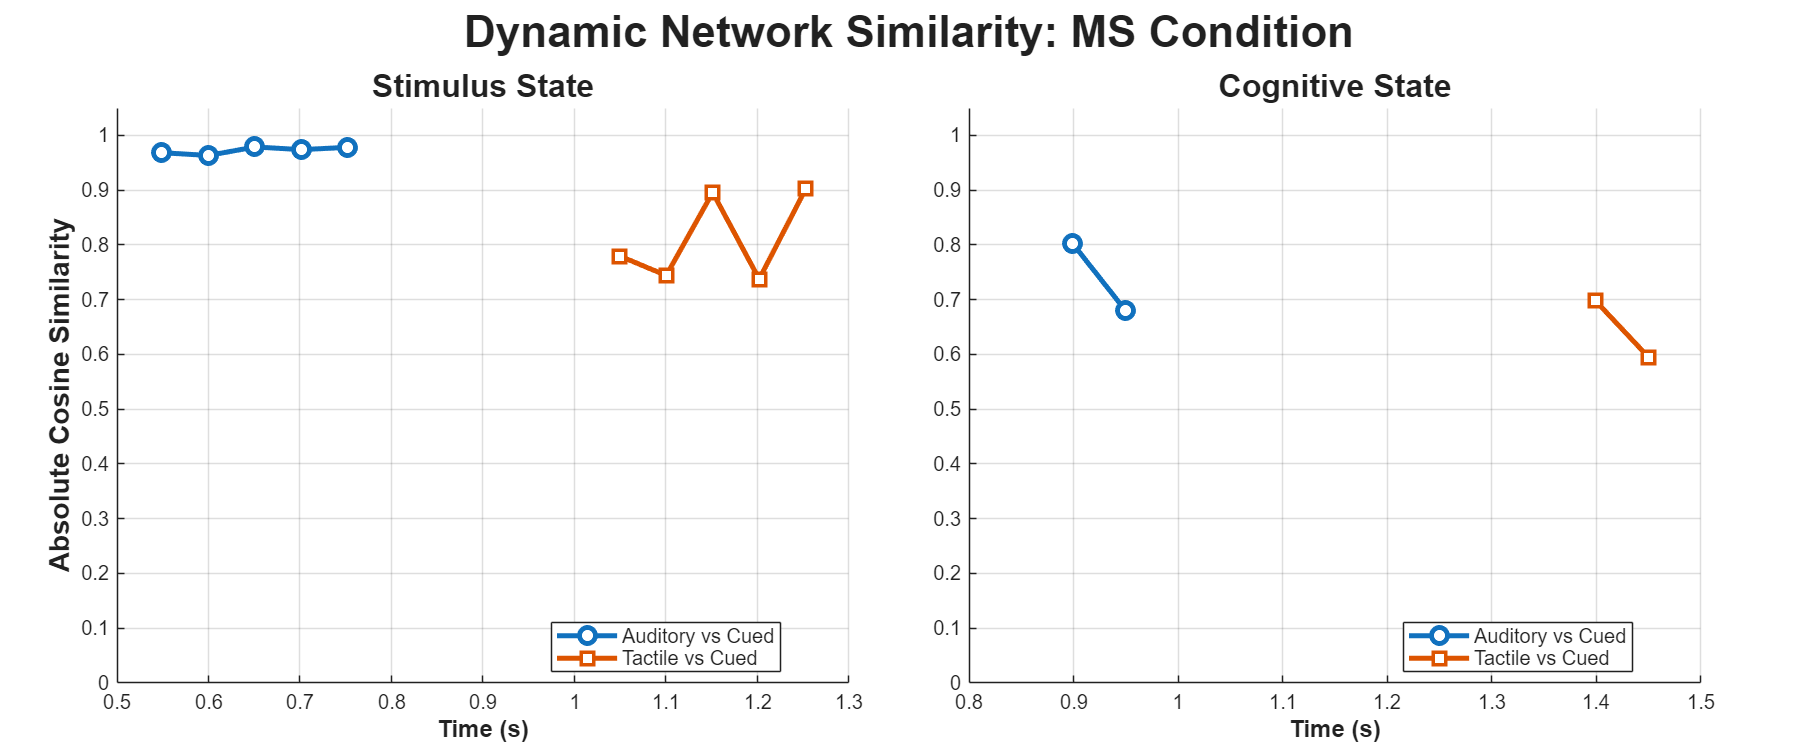


--- Temporal Uncertainty: Stimulus State ---


Processing Pair 1/2: 5 Windows...
Processing Pair 2/2: 5 Windows...



--- Temporal Uncertainty: Cognitive State ---


Processing Pair 1/2: 2 Windows...
Processing Pair 2/2: 2 Windows...


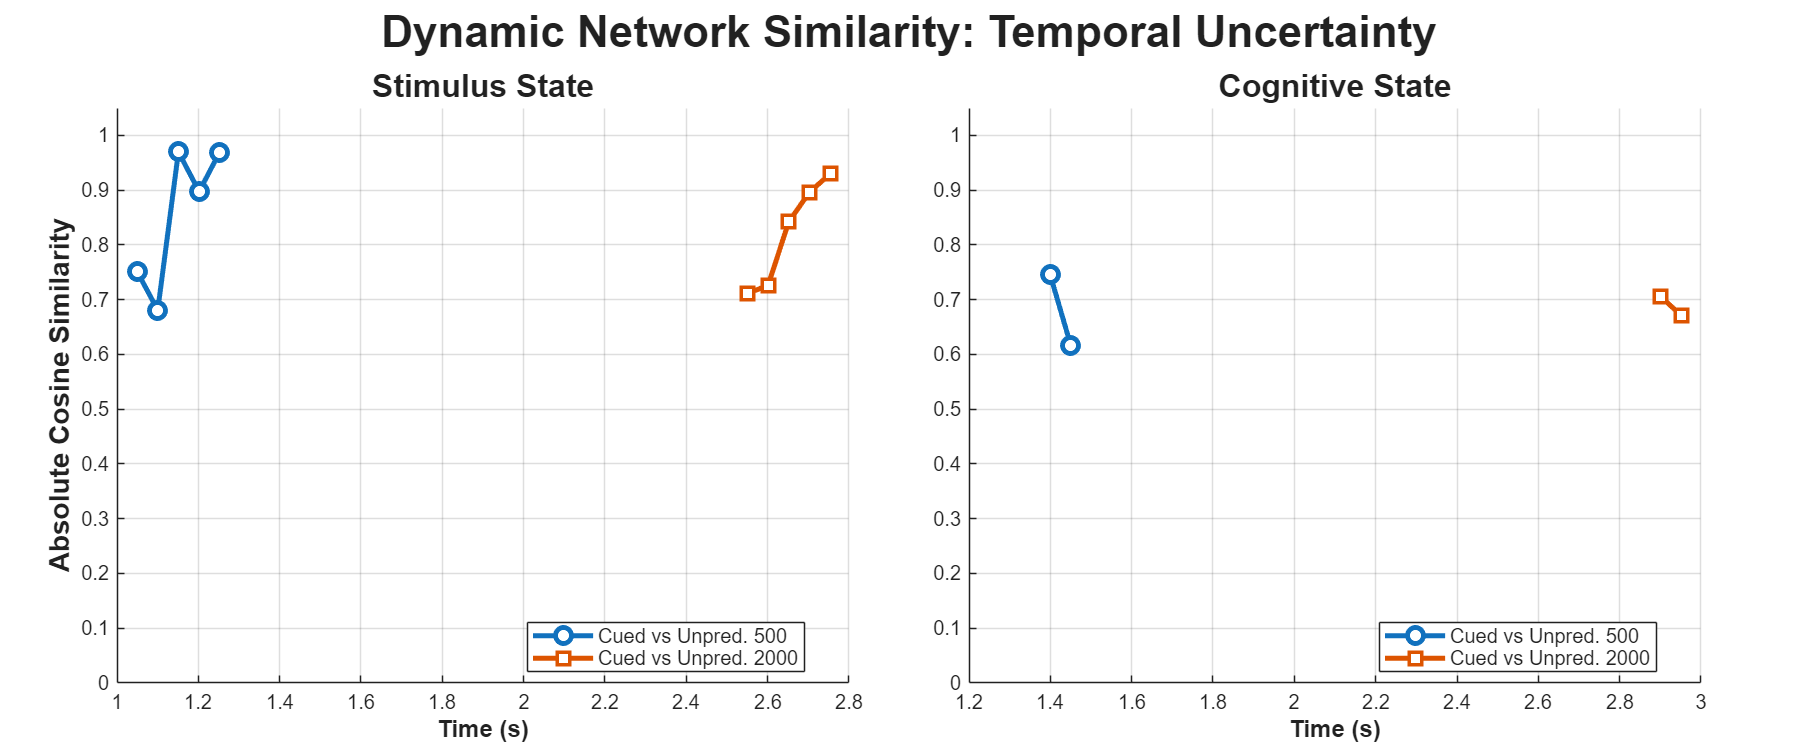


--- Stimulus Uncertainty: Stimulus State ---


Processing Pair 1/2: 5 Windows...
Processing Pair 2/2: 5 Windows...



--- Stimulus Uncertainty: Cognitive State ---


Processing Pair 1/2: 2 Windows...
Processing Pair 2/2: 8 Windows...


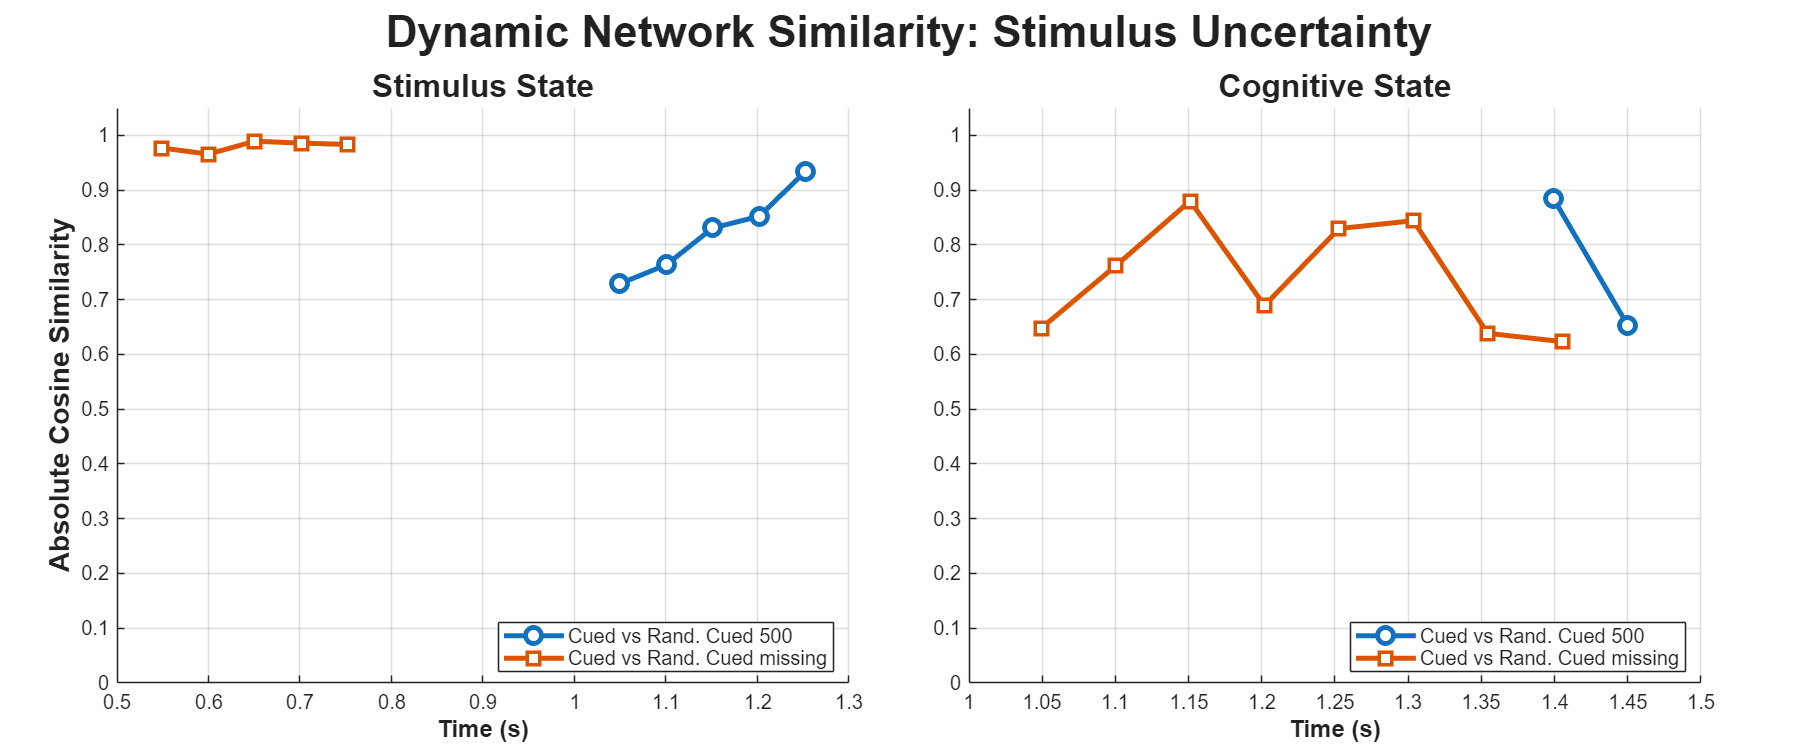


% Inline helper function to clean names for the legend
get_clean_name = @(c) strrep(strrep(strrep(strrep(strrep(strrep(c, ...
    'BLA', 'Auditory'), 'BLT', 'Tactile'), 'P1', 'Cued'), ...
    'P2', 'Unpred.'), 'P3', 'Rand. Cued'), '_', ' ');

% 1. Define Groups and their specific comparison pairs
% Format: {'CondA', 'CondB', [Stim_Win], [Cog_Win]}
groups = struct();

groups(1).name = 'MS Condition';
groups(1).pairs = {
    {'BLA', 'P1', [0.5, 0.85], [0.85, 1.0]},
    {'BLT', 'P1', [1.0, 1.35], [1.35, 1.5]}
};

groups(2).name = 'Temporal Uncertainty';
groups(2).pairs = {
    {'P1', 'P2_500', [1.0, 1.35], [1.35, 1.5]},    
    {'P1', 'P2_2000', [2.5, 2.85], [2.85, 3.0]}   
};

groups(3).name = 'Stimulus Uncertainty';
groups(3).pairs = {
    {'P1', 'P3_500', [1.0, 1.35], [1.35, 1.5]},
    {'P1', 'P3_missing', [0.5, 0.85], [1, 1.5]} 
};

state_names = {'Stimulus State', 'Cognitive State'};
target_subj = 1; 

if isempty(fs), fs = EEG.srate; end % Fallback for sampling rate
n_perms = 1000; 

% Sliding window configuration
window_size_ms = 100;
step_size_ms = 50;
win_samples = round((window_size_ms / 1000) * fs);
step_samples = round((step_size_ms / 1000) * fs);

% Define distinct line colors/markers for the plots
colors = lines(5);
markers = {'o', 'square', '^', 'd', 'pentagram'};

%% 2. Process Groups and Generate Figures
for g = 1:length(groups)
    current_group = groups(g);
    n_pairs = length(current_group.pairs);
    
    % Create a 1x2 Figure for this specific group
    fig = figure('Position', [100, 100, 1200, 500], 'Name', sprintf('%s: Cosine Similarity', current_group.name));
    tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
    
    % Loop through Stimulus State (Tile 1) then Cognitive State (Tile 2)
    for state_idx = 1:2
        active_state = state_names{state_idx};
        nexttile; hold on;
        
        fprintf('\n--- %s: %s ---\n', current_group.name, active_state);
        
        for p = 1:n_pairs
            condA = current_group.pairs{p}{1};
            condB = current_group.pairs{p}{2};
            t_win = current_group.pairs{p}{2 + state_idx}; 
            
            cleanA = get_clean_name(condA);
            cleanB = get_clean_name(condB);
            pair_label = sprintf('%s vs %s', cleanA, cleanB);
            
            trialsA_raw = data_all_conds.(condA){target_subj};
            trialsB_raw = data_all_conds.(condB){target_subj};
            nA = size(trialsA_raw, 3); nB = size(trialsB_raw, 3);
            total_trials = nA + nB;
            
            if nA == 0 || nB == 0, continue; end
            
            trialsA = zeros(size(trialsA_raw)); trialsB = zeros(size(trialsB_raw));
            for tr = 1:nA, trialsA(:,:,tr) = zscore(trialsA_raw(:,:,tr), 0, 2); end
            for tr = 1:nB, trialsB(:,:,tr) = zscore(trialsB_raw(:,:,tr), 0, 2); end
            
            pool_trials_ch = cat(3, trialsA, trialsB);
            
            idx_start = find(time_ms_eeg >= t_win(1), 1, 'first');
            idx_end = find(time_ms_eeg <= t_win(2), 1, 'last');
            
            time_chunk = time_ms_eeg(idx_start:idx_end);
            start_idx = 1 : step_samples : (length(time_chunk) - win_samples + 1);
            num_windows = length(start_idx);
            
            if num_windows == 0, continue; end
            
            cos_sim_array = zeros(1, num_windows);
            window_centers = zeros(1, num_windows);
            
            fprintf('Processing Pair %d/%d: %d Windows...\n', p, n_pairs, num_windows);
            
            for w = 1:num_windows
                w_s = idx_start + start_idx(w) - 1;
                w_e = w_s + win_samples - 1;
                window_centers(w) = mean(time_ms_eeg(w_s:w_e));
                
                real_ch_A = cov(mean(trialsA(:, w_s:w_e, :), 3, 'omitnan')');
                real_ch_B = cov(mean(trialsB(:, w_s:w_e, :), 3, 'omitnan')');
                
                null_ch_A = nan(num_ch, num_ch, n_perms); 
                null_ch_B = nan(num_ch, num_ch, n_perms);
                pool_slice = pool_trials_ch(:, w_s:w_e, :);
                
                for prm = 1:n_perms
                    shuf_idx = randperm(total_trials);
                    idxA = shuf_idx(1:nA); idxB = shuf_idx(nA+1:end);
                    
                    null_ch_A(:,:,prm) = cov(mean(pool_slice(:,:,idxA), 3, 'omitnan')');
                    null_ch_B(:,:,prm) = cov(mean(pool_slice(:,:,idxB), 3, 'omitnan')');
                end
                
                sub_ch_A = real_ch_A - mean(null_ch_A, 3, 'omitnan');
                sub_ch_B = real_ch_B - mean(null_ch_B, 3, 'omitnan');
                
                % --- THE FIX: Take the absolute magnitude of the subtracted deviation ---
                vecA = abs(sub_ch_A(:)); 
                vecB = abs(sub_ch_B(:));
                
                % Calculate Cosine Similarity
                cos_sim_array(w) = dot(vecA, vecB) / (norm(vecA) * norm(vecB));
            end
            
            plot(window_centers, cos_sim_array, 'LineWidth', 2.5, ...
                'Color', colors(p,:), 'Marker', markers{p}, 'MarkerSize', 8, ...
                'MarkerFaceColor', 'w', 'DisplayName', pair_label);
        end
        
        % Formatting
        % The Y-axis limits are now 0 to 1 since we are strictly using absolute magnitudes
        ylim([0 1.05]);
        xlabel('Time (s)', 'FontSize', 12, 'FontWeight', 'bold');
        if state_idx == 1
            ylabel('Absolute Cosine Similarity', 'FontSize', 14, 'FontWeight', 'bold');
        end
        title(active_state, 'FontSize', 16, 'FontWeight', 'bold');
        grid on;
        legend('Location', 'best', 'FontSize', 10);
    end
    
    sgtitle(sprintf('Dynamic Network Similarity: %s', current_group.name), ...
        'FontSize', 22, 'FontWeight', 'bold');
end


disp('Absolute Cosine Similarity Line Plots Generated Successfully!');

Absolute Cosine Similarity Line Plots Generated Successfully!
